# Machine Learning: Programming Exercise 4

## Neural Networks Learning

In this exercise, you will implement the backpropagation algorithm for neural networks and apply it to the task of hand-written digit recognition.

### Files needed for this exercise

- `ex4.mlx` - MATLAB Live Script that steps you through the exercise

- `ex4data1.mat` - Training set of hand-written digits

- `ex4weights.mat` - Neural network parameters for exercise 4

- `submit.m` - Submission script that sends your solutions to our servers

- `displayData.m` - Function to help visualize the dataset

- `fmincg.m` - Function minimization routine (similar to `fminunc`)

- `sigmoid.m` - Sigmoid function

- `computeNumericalGradient.m` - Numerically compute gradients

- `checkNNGradients.m` - Function to help check your gradients

- `debugInitializeWeights.m` - Function for initializing weights

- `predict.m` - Neural network prediction function

- *`sigmoidGradient.m` - Compute the gradient of the sigmoid function

- *`randInitializeWeights.m` - Randomly initialize weights

- *`nnCostFunction.m` - Neural network cost function

**** indicates files you will need to complete***

#### Confirm that your Current Folder is set correctly

Click into this section, then click the 'Run section' button above. This will execute the `dir` command below to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex4' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

dir

### Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README` and have checked for an existing solution before seeking help on the discussion forums.

## 1. Neural Networks

In the previous exercise, you implemented feedforward propagation for neural networks and used it to predict handwritten digits with the weights we provided. In this exercise, you will implement the backpropagation algorithm to learn the parameters for the neural network.

### 1.1 Visualizing the data

The code below will load the data and display it on a 2-dimensional plot (Figure 1) by calling the function `displayData`. This is the same dataset that you used in the previous exercise. Run the code below to load the training data into the variables `X` and `y.`

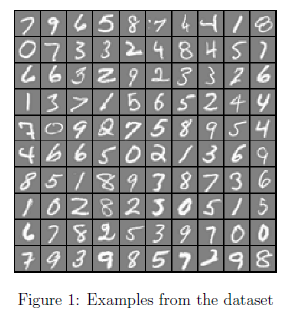

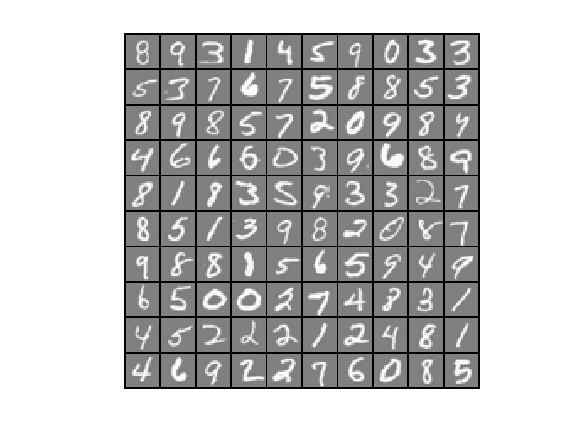

load('ex4data1.mat');
m = size(X, 1);

% Randomly select 100 data points to display
sel = randperm(size(X, 1));
sel = sel(1:100);

displayData(X(sel, :));

    There are 5000 training examples in `ex4data1.mat`, where each training example is a 20 pixel by 20 pixel grayscale image of the digit. Each pixel is represented by a floating point number indicating the grayscale intensity at that location. The 20 by 20 grid of pixels is 'unrolled' into a 400-dimensional vector. Each of these training examples becomes a single row in our data matrix `X`. This gives us a 5000 by 400 matrix `X` where every row is a training example for a handwritten digit image.


$$X=\left\lbrack \begin{array}{c}
-{\left(x^{\left(1\right)} \right)}^T -\\
-{\left(x^{\left(2\right)} \right)}^T -\\
\vdots \\
-{\left(x^{\left(m\right)} \right)}^T -
\end{array}\right\rbrack$$


The second part of the training set is a 5000-dimensional vector `y` that contains labels for the training set. To make things more compatible with MATLAB indexing, where there is no zero index, we have mapped the digit zero to the value ten. Therefore, a '0' digit is labeled as '10', while the digits '1' to '9' are labeled as '1' to '9' in their natural order.

### 1.2 Model representation

Our neural network is shown in Figure 2. It has 3 layers- an input layer, a hidden layer and an output layer. Recall that our inputs are pixel values of digit images. Since the images are of size 20 x 20, this gives us 400 input layer units (not counting the extra bias unit which always outputs +1). 

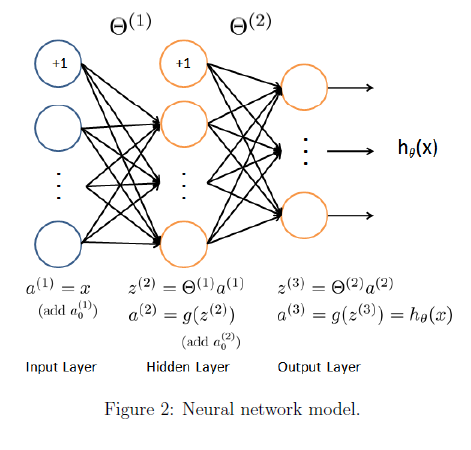

    You have been provided with a set of network parameters $(\Theta^{(1)},\Theta^{(2)})$ already trained by us. These are stored in `ex4weights.mat. ` Run the code below to load them into `Theta1` and `Theta2`. The parameters have dimensions that are sized for a neural network with 25 units in the second layer and 10 output units (corresponding to the 10 digit classes).

% Load the weights into variables Theta1 and Theta2
load('ex4weights.mat');

### 1.3 Feedforward and cost function

Now you will implement the cost function and gradient for the neural network. First, complete the code in `nnCostFunction.m` to return the cost. Recall that the cost function for the neural network (without regularization) is


$$J(\theta) =\frac{1}{m}{\sum_{i=1}^m\sum_{k=1}^K{\left[

-y_k^{(i)} \log((h_{\theta}(x^{(i)}))_k)- (1 -y_k^{(i)}) \log(1- (h_{\theta}(x^{(i)}))_k)\right]},$$


where $h_\theta(x^{(i)})$ is computed as shown in the Figure 2 and $K = 10$ is the total number of possible labels. Note that $h_\theta(x^{(i)})_k = a^{(3)}_k$ is the activation (output value) of the $k$-th output unit. Also, recall that whereas the original labels (in the variable `y`) were $1, 2, \ldots, 10,$ for the purpose of training a neural network, we need to recode the labels as vectors containing only values 0 or 1, so that


$$y=\left\lbrack \begin{array}{c}
1\\
0\\
0\\
\vdots \\
0
\end{array}\right\rbrack ,\left\lbrack \begin{array}{c}
0\\
1\\
0\\
\vdots \\
0
\end{array}\right\rbrack ,\dots \textrm{or}\;\left\lbrack \begin{array}{c}
0\\
0\\
0\\
\vdots \\
1
\end{array}\right\rbrack$$


    For example, if $x^{(i)}$ is an image of the digit 5, then the corresponding $y^{(i)}$ (that you should use with the cost function) should be a 10-dimensional vector with $y_5 = 1$, and the other elements equal to 0. You should implement the feedforward computation that computes $h_\theta(x^{(i)})$ for every example $i$ and sum the cost over all examples. Your code should also work for a dataset of any size, with any number of labels (you can assume that there are always at least $K\geq 3$ labels). 

**Implementation Note:** The matrix `X` contains the examples in rows (i.e., `X(i,:)'` is the `i`-th training example $x^{(i)}$, expressed as a $n$ x 1 vector.) When you complete the code in `nnCostFunction.m`, you will need to add the column of 1's to the `X` matrix. The parameters for each unit in the neural network is represented in `Theta1` and `Theta2` as one row. Specifically, the first row of `Theta1` corresponds to the first hidden unit in the second layer. You can use a `for` loop over the examples to compute the cost.  We suggest implementing the feedforward cost *without* regularization first so that it will be easier for you to debug. Later, you will get to implement the regularized cost.

    Once you are done, run the code below to call your `nnCostFunction` using the loaded set of parameters for `Theta1` and `Theta2`. You should see that the cost is about 0.287629.

input_layer_size  = 400;  % 20x20 Input Images of Digits
hidden_layer_size = 25;   % 25 hidden units
num_labels = 10;          % 10 labels, from 1 to 10 (note that we have mapped "0" to label 10)

% Unroll parameters 
nn_params = [Theta1(:) ; Theta2(:)];

% Weight regularization parameter (we set this to 0 here).
lambda = 0;

J = nnCostFunction(nn_params, input_layer_size, hidden_layer_size, num_labels, X, y, lambda);

z_2 =    -2.9368
   -2.4506
    4.9551
    0.0749
    0.8724
    5.6501
   -4.5232
   -6.4160
    5.6512
   -3.8716


z_2 =    -4.8130
   -2.9226
    2.6445
    0.8486
   -1.0779
    5.6038
   -1.8788
   -7.2873
    5.8752
   -4.4279


z_2 =    -4.2406
   -3.6870
    5.9966
    2.0348
    2.3788
    3.9404
   -4.4929
   -4.4663
    3.1144
   -2.4424


z_2 =    -3.0345
   -5.6188
    5.4439
    2.1852
    1.8401
    3.9832
   -4.4231
   -4.3069
    0.7428
   -4.3353


z_2 =    -6.2729
   -2.4730
    4.4582
    0.8078
    0.5775
    7.5511
   -5.4968
  -11.7895
   11.9974
   -1.1116


z_2 =    -5.5205
   -7.4163
    9.3259
   -0.1708
    2.4307
    6.3287
   -4.5857
  -10.9282
   11.5273
   -7.3066


z_2 =    -5.1122
   -4.5838
    1.8262
    1.9035
   -0.6024
    3.9698
   -4.8341
   -8.8372
    5.9129
   -0.3346


z_2 =    -5.1449
   -4.4040
    5.8413
    1.7398
    3.9414
    7.1553
   -3.5875
   -8.9280
    5.1848
   -6.7136


z_2 =    -5.6325
   -3.0610
    5.4993
    0.3585
    1.2115
    5.8647
   -8.0785
   -7.7832
    7.1982
   -2.5010


z_2 =    -6.0249
   -0.1681
    1.3531
    1.4561
   -0.6832
    4.9578
   -4.2386
   -7.1493
    5.3895
   -0.0867


z_2 =    -5.7097
   -0.9050
    5.3112
    1.6056
    1.3316
    6.0297
   -6.5247
   -7.4387
    6.6055
   -1.3309


z_2 =    -3.6987
   -4.9493
    5.2754
    1.0435
    4.1786
    7.8095
   -6.1904
   -9.1875
    8.5731
   -4.9014


z_2 =    -4.6623
   -2.8642
    5.9002
    1.3397
    2.4865
    6.4010
   -7.6047
   -6.9678
    6.0824
   -3.4624


z_2 =    -2.6256
   -7.4188
    7.1311
    1.0699
    5.1207
    6.7864
   -5.3114
   -7.6919
    5.8636
   -7.4401


z_2 =    -5.8646
   -3.9115
    7.2226
   -0.3881
    0.9645
    7.3252
   -5.0393
  -10.6419
    9.0737
   -6.7252


z_2 =    -3.5273
   -3.0805
    5.4906
    1.9156
    0.0254
    5.9282
   -4.9777
   -2.5239
    3.9180
   -4.7320


z_2 =    -5.9762
   -3.5173
    5.8636
    3.6595
   -0.1462
    6.2277
   -3.1116
   -9.1617
    4.3145
   -4.4214


z_2 =    -8.5508
   -6.8673
   13.7559
    7.0366
    4.8984
   14.5765
   -9.6715
  -10.0572
    9.3857
  -11.5674


z_2 =    -4.0622
   -1.4970
    5.5835
    0.0791
    0.4222
    5.5992
   -3.0544
   -7.9538
    7.5635
   -3.5896


z_2 =    -5.6531
   -1.0970
    4.7860
    2.0848
    1.7859
    6.1741
   -7.3716
   -5.3157
    4.3914
   -3.3245


z_2 =    -1.6293
   -4.9441
    5.7486
    1.8091
    4.0457
    5.4371
   -5.7755
   -3.1655
    1.9254
   -6.0182


z_2 =    -6.4097
   -2.3396
    6.2138
    0.0638
    1.3999
    8.9956
   -7.0054
  -12.6418
   13.8548
   -4.1151


z_2 =    -5.6625
   -3.7902
    7.2068
    2.4621
    5.8692
   11.8439
   -8.2011
  -13.0198
   10.0412
   -8.3519


z_2 =    -2.2469
   -2.1188
    3.8810
    0.8770
    0.2809
    3.1303
   -3.9853
   -4.2987
    4.1939
   -1.8948


z_2 =    -3.6892
   -1.1411
    5.7479
    0.9369
    2.0853
    2.9544
   -5.1117
   -6.1392
    5.5508
   -0.7280


z_2 =    -4.4806
   -5.7880
    6.0420
    1.2541
    4.1524
    8.9441
   -5.6487
  -12.7670
    9.6853
   -6.4296


z_2 =    -0.4680
   -2.9972
    3.9763
    0.9149
    2.3639
    2.5170
   -4.7841
   -1.5048
    0.6644
   -2.6403


z_2 =    -2.9304
   -2.9172
    2.9083
    2.5023
    1.7387
    4.1733
   -4.7173
   -4.5944
    2.8011
   -2.4596


z_2 =    -5.0725
   -3.1600
    6.7407
    3.5595
    1.8795
    6.8664
   -3.7439
   -9.7867
    7.2400
   -4.3240


z_2 =    -4.8333
   -4.6096
    7.4338
   -0.1906
    4.4752
    9.2532
   -6.6879
  -12.5296
   10.7267
   -7.6279


z_2 =    -1.7819
   -3.6122
    3.3925
   -1.0514
   -0.8310
    1.2208
   -0.5774
   -4.3417
    1.4785
   -5.0010


z_2 =    -4.9119
   -9.8265
   10.9907
    5.4758
    6.4007
   11.5076
   -7.7983
   -8.3568
    5.4761
  -11.4222


z_2 =    -4.8121
   -5.4071
   10.0693
    6.5214
    5.8672
   11.4955
   -8.4609
   -6.8574
    4.8578
   -8.4282


z_2 =    -0.9689
   -6.2495
    4.8407
    0.3735
    3.8347
    5.2607
   -4.5249
   -5.0832
    3.0042
   -5.5097


z_2 =    -5.1899
   -3.8326
    8.0131
    4.6417
    3.5592
    9.9104
   -6.5871
   -8.0828
    4.4541
   -7.6394


z_2 =    -2.9802
   -3.7441
    5.4085
    0.3992
    3.8386
    7.1346
   -7.8195
   -4.9624
    5.6564
   -5.4027


z_2 =    -2.9812
   -3.4365
    5.1278
    1.0490
    1.7388
    4.6076
   -5.6354
   -5.1422
    4.7486
   -2.9696


z_2 =    -5.8911
   -2.4680
    5.6583
    3.4547
    1.9808
    7.2733
   -4.3555
   -9.0926
    6.3412
   -3.9514


z_2 =    -5.6872
   -5.7112
   10.8373
    7.6796
    2.3338
    7.6495
   -3.7574
   -6.2954
    0.5967
   -7.8165


z_2 =    -4.0943
   -8.4842
   10.2643
    5.0776
    3.3687
    7.2218
   -5.1885
   -7.8459
    2.9394
   -8.8432


z_2 =    -6.1219
   -6.4090
    9.6885
    4.8779
    5.3707
   12.4478
   -7.6983
  -10.9583
    7.9183
  -10.8350


z_2 =    -5.5565
   -5.1105
    9.0133
    3.3430
    3.3346
    9.0932
   -5.1602
   -8.8965
    7.0613
   -9.5340


z_2 =    -5.0302
   -9.3151
   12.1547
    4.5804
    5.4662
   10.1189
   -8.1820
   -6.4182
    8.5355
  -11.6745


z_2 =    -0.9387
   -4.3050
    3.7700
   -1.0175
    1.8995
    1.9173
   -4.8514
   -4.6427
    2.5941
   -3.1229


z_2 =    -5.4181
   -1.7657
    9.0786
    5.1474
    1.5330
    6.7196
   -2.2638
   -5.3634
    2.5394
   -5.9747


z_2 =    -5.5378
   -5.6827
    8.8193
    4.7476
    5.7087
    9.7886
   -7.3580
  -10.2836
    7.7663
   -6.0276


z_2 =    -4.2178
   -6.8900
    7.7476
    0.8883
    2.5339
    8.0796
   -6.5353
  -10.5937
    7.7307
   -9.1434


z_2 =    -1.3720
  -10.0408
    7.8275
    1.7800
    7.1949
    9.5831
   -7.7848
  -10.9352
    6.8372
  -11.0495


z_2 =    -3.0310
   -2.0765
    7.0270
    3.2150
    1.3686
    4.6884
   -3.1078
   -5.5310
    2.2174
   -4.0245


z_2 =    -2.2602
   -4.6911
    8.2163
    1.3235
    0.4197
    1.1012
   -0.8078
   -6.9064
    1.9622
   -5.6834


z_2 =    -2.4523
   -5.5718
    6.8206
    2.2672
    1.1894
    2.6088
    0.0486
   -8.2187
    1.6969
   -4.7566


z_2 =    -3.3602
   -3.7181
    5.6173
    4.4255
    4.0724
   10.2574
   -8.9649
   -7.3752
    4.6305
   -6.5264


z_2 =    -3.7374
   -8.4956
    9.4894
    2.6954
    6.5129
   10.6690
   -8.0018
  -11.6311
    8.4458
  -10.5393


z_2 =    -0.5182
   -4.8908
    3.5125
    2.2081
   -0.1464
   -1.9777
    3.6163
   -3.4270
   -3.0202
   -2.7931


z_2 =    -4.4413
   -3.0029
    7.0535
    5.1349
    4.4327
    6.8133
   -7.9838
   -3.9890
    0.7420
   -4.9786


z_2 =    -3.3397
   -3.1009
    6.3267
    2.4505
    0.3807
    3.6115
   -0.8173
   -8.5938
    3.6198
   -2.8158


z_2 =    -3.3343
   -4.2534
    6.6220
   -0.7706
    1.3429
    3.3115
   -4.9067
   -3.7388
    6.2016
   -2.5212


z_2 =    -1.4497
   -8.1839
    6.7506
   -0.3301
    4.8370
    7.4966
   -6.1643
   -6.3227
    8.6367
   -7.2344


z_2 =    -3.2615
   -2.5426
    4.1592
    4.3705
    0.2723
    2.3919
   -0.1464
   -5.2985
   -1.1243
   -1.8094


z_2 =    -2.1116
   -4.5100
    4.0966
   -0.5918
    3.3273
    5.6273
   -6.2557
   -5.7062
    5.7387
   -4.7417


z_2 =    -2.5617
   -1.9788
    3.6383
    2.8817
    1.0407
    0.9349
   -0.3454
   -5.8717
    0.9009
   -1.2766


z_2 =    -3.2673
   -2.9658
    4.9197
    1.0763
    1.1778
    4.4527
   -3.0960
   -7.2747
    4.8287
   -3.3618


z_2 =    -1.2355
   -6.3373
    8.2162
    1.5137
    2.8375
    3.1932
   -5.6156
   -3.7334
    1.0742
   -5.4374


z_2 =    -4.1060
   -2.9726
    4.2682
    0.3751
   -0.2627
    3.8437
   -6.2174
   -5.9762
    6.1879
   -1.4832


z_2 =    -0.5195
   -3.6823
    4.9699
    2.0398
    3.3865
    2.6460
   -2.8705
   -2.3947
   -0.1854
   -4.4976


z_2 =    -2.3114
   -6.1621
    3.3472
    4.6662
   -1.2811
   -0.6874
    3.0548
   -5.6431
   -5.8596
   -3.1820


z_2 =    -1.7368
   -5.5470
    6.4360
    0.0462
    4.2367
    5.3903
   -6.7117
   -5.7676
    6.3076
   -3.8494


z_2 =    -5.1742
   -1.8872
    5.8687
    3.9594
    1.1148
    6.8406
   -4.0900
   -6.7626
    4.3349
   -3.4295


z_2 =    -5.1802
   -1.6702
    5.3129
    4.3007
    0.8152
    6.0009
   -3.3718
   -7.0372
    3.6214
   -2.0532


z_2 =     0.2480
   -6.3306
    5.4662
    2.0667
    5.9088
    4.3225
   -5.8415
   -5.1262
   -0.0090
   -3.7526


z_2 =    -4.0575
   -1.1925
    3.2397
    0.6173
   -0.0302
    4.2032
   -1.7707
   -8.0274
    5.9116
   -0.8557


z_2 =    -4.2926
   -6.2276
    7.0437
    4.2960
    1.0533
    2.8568
   -0.8658
   -5.0238
    2.8725
   -3.7616


z_2 =    -7.5736
   -1.5872
   10.2329
    7.8024
    0.8249
    7.7054
   -4.0248
   -6.4158
    1.6996
   -4.2818


z_2 =    -6.4114
   -1.7927
    7.6904
    7.1321
    0.6104
    6.8395
   -3.0717
   -6.1527
    1.5926
   -3.1799


z_2 =    -4.4081
   -2.7121
    6.0853
    6.7856
    0.1551
    2.8765
    0.2052
   -5.4457
   -1.7558
   -1.5127


z_2 =    -1.1120
   -3.4909
    4.7968
    0.0510
    2.6740
    1.4601
   -5.5249
   -4.5128
    2.1691
   -1.9138


z_2 =    -6.3178
   -2.5444
    7.7526
    6.8953
    0.5462
    6.4830
   -2.7917
   -6.2421
    1.1857
   -3.6616


z_2 =    -4.2100
   -1.7605
    6.7576
    3.9813
    2.0699
    7.0636
   -4.3986
   -6.3973
    4.1435
   -4.6087


z_2 =    -4.9261
   -1.4832
    5.9599
    4.5310
    3.8444
   10.8015
   -8.8644
   -8.4169
    4.3312
   -5.7118


z_2 =    -3.7765
   -1.7023
    3.6572
    1.0954
    1.1266
    4.4500
   -4.2386
   -7.2370
    5.9663
   -0.7819


z_2 =    -1.6486
   -4.5892
    7.5514
    4.1733
    1.6289
    1.9171
   -0.4971
   -4.6623
   -1.0972
   -4.6487


z_2 =    -5.5649
   -2.0333
    4.7366
    5.0290
    1.0923
    4.8834
   -1.9670
   -5.6694
    1.8100
   -2.4943


z_2 =    -3.5043
   -2.1491
    5.1182
    3.1273
    1.0239
    2.4854
   -0.6789
   -6.8548
    3.2667
   -1.0081


z_2 =    -3.9422
   -2.5390
    7.8533
    3.8168
    2.5633
    6.3553
   -4.8475
   -5.5254
    2.9547
   -5.1877


z_2 =    -3.7904
   -1.3036
    5.1818
    3.7499
    1.3999
    4.2421
   -4.0942
   -5.3031
    0.4473
   -1.7032


z_2 =    -0.8123
  -12.6043
    8.2029
   -0.9268
    5.8695
    7.6123
   -6.2492
   -8.1444
    9.0409
   -8.4137


z_2 =    -1.5566
   -4.4036
    5.3187
    2.7204
   -1.2198
   -0.3206
    3.2413
   -3.5182
    0.3328
   -1.5509


z_2 =    -1.5278
   -3.7864
    5.2888
    3.8833
   -0.4567
   -0.2380
    2.3762
   -3.1054
   -0.1820
   -0.9264


z_2 =    -3.4850
   -1.0608
    5.1964
    3.2987
    1.7214
    5.0397
   -4.2651
   -5.8827
    2.6492
   -2.2968


z_2 =    -0.7929
   -3.9566
    2.5939
    2.0858
    0.6521
   -0.4034
    0.7323
   -2.9262
   -0.1752
   -2.2190


z_2 =    -0.7710
   -3.5275
    6.3364
    1.5804
    2.1830
    1.9162
   -1.4438
   -6.6313
    3.0943
   -2.7123


z_2 =    -2.7993
   -3.1653
    5.1117
   -0.4306
    1.8458
    3.2101
   -6.0008
   -4.8062
    6.3170
   -1.0633


z_2 =    -3.2518
   -1.5344
    4.0893
    2.9974
    1.6593
    1.8459
   -1.6830
   -4.8672
    0.7054
   -1.1608


z_2 =    -2.6915
   -1.3151
    5.3880
    3.7492
   -0.0093
    2.0866
   -1.3484
   -3.7769
   -1.2996
   -0.8881


z_2 =    -1.6158
   -2.4427
    4.7497
    2.3018
    1.5334
    0.9224
   -1.4844
   -4.1957
    0.1366
   -1.4069


z_2 =    -2.2662
   -5.9972
    5.7197
    0.7365
    3.2345
    4.1893
   -4.0400
   -8.1430
    6.2330
   -3.4414


z_2 =    -0.8717
   -3.5991
    4.3081
    1.9953
   -0.2656
   -0.4018
    2.0943
   -4.1644
    0.3887
   -1.1526


z_2 =    -3.2628
   -2.4494
    5.5175
    0.9898
    1.1832
    3.7223
   -5.2299
   -3.8666
    4.8125
   -1.4292


z_2 =    -3.7554
   -0.1373
    4.4439
    4.2782
    0.1033
    2.9959
   -0.2998
   -3.0943
   -0.2043
   -0.3926


z_2 =    -1.6470
   -6.6892
    3.4173
   -1.1792
    3.2890
    4.9700
   -6.5940
   -5.9298
    5.4922
   -4.9142


z_2 =    -4.4944
   -6.5546
    8.5444
    2.5491
    5.3630
    9.1869
   -6.3330
   -9.1067
    7.3707
   -9.3914


z_2 =    -4.5737
   -0.4258
    4.4748
    4.8580
   -1.8763
    3.1577
    0.4807
   -2.4144
   -0.6160
   -1.2862


z_2 =    -6.4685
   -3.8489
    8.0464
    1.6446
    2.4681
    9.0039
   -7.3788
  -12.8493
   12.7101
   -4.5031


z_2 =    -1.5757
   -2.0948
    3.5966
    0.4138
    2.1869
    2.3941
   -3.1173
   -6.5361
    5.6955
   -1.5155


z_2 =    -2.6445
   -0.6225
    0.2854
    0.4072
   -0.8700
    0.7490
    1.7301
   -3.7387
    1.6239
    0.2219


z_2 =    -2.1833
   -2.4222
    2.8156
   -1.5314
    3.7674
    3.9577
   -7.2729
   -6.8573
    6.7502
   -0.6465


z_2 =    -5.5582
   -1.9959
    5.9003
    2.6289
    3.1858
   10.6214
   -7.3502
   -9.8233
    9.1763
   -5.6600


z_2 =    -4.1905
   -2.2857
    7.0169
    3.6552
    0.2345
    6.8709
   -5.5870
   -5.6765
    4.2381
   -4.3340


z_2 =    -5.8536
   -1.4326
    4.9825
    4.2574
    0.0366
    6.5117
   -2.1885
   -5.1625
    5.0620
   -2.8928


z_2 =    -4.9186
   -1.8738
    5.2122
    4.6713
    1.9471
    7.6233
   -5.1757
   -5.8304
    2.3929
   -3.7687


z_2 =    -4.3381
   -2.6415
    7.6648
    3.5271
    0.5409
    4.6133
   -3.5643
   -4.9974
    2.8797
   -2.4955


z_2 =    -3.2527
   -3.8501
    3.8301
    1.7561
    1.6812
    5.0805
   -4.6515
   -4.1878
    4.2260
   -4.5156


z_2 =    -6.5577
   -0.7894
    0.9805
    2.8968
   -0.6527
    4.3600
   -2.4092
   -4.9058
    4.6629
   -0.3540


z_2 =    -4.0207
   -3.1378
    6.6198
    2.8709
    4.4010
    8.5744
   -7.0998
   -5.2803
    5.4550
   -6.4993


z_2 =    -1.6805
   -0.9769
    3.6828
    0.7468
    0.4773
    2.1509
   -3.3907
   -2.4556
    2.0600
   -1.7232


z_2 =    -2.4161
   -7.0384
    7.5166
    3.2230
    2.8039
    4.4196
   -3.5771
   -8.2132
    3.9626
   -4.9844


z_2 =    -3.3713
   -7.3083
    5.9813
    3.9246
    1.2507
    2.5118
   -1.5617
   -4.3938
    0.8524
   -4.0728


z_2 =    -2.9122
  -12.4428
    9.5988
    3.4643
   -0.0758
    3.2383
   -3.1059
   -6.9455
    3.3534
   -4.7390


z_2 =    -2.4268
   -4.9242
    7.8973
    2.3994
    3.6051
    3.3681
   -5.4995
   -4.4517
    2.9668
   -4.3254


z_2 =    -3.2497
   -3.2175
    2.2459
    2.6412
    0.6641
    3.5735
   -2.2581
   -6.0749
   -0.0155
   -2.2980


z_2 =    -7.4313
   -1.6590
    3.5340
    2.1128
   -0.5930
    6.4078
   -3.9921
   -8.8573
    9.9493
   -1.6563


z_2 =    -1.4993
   -6.2869
   10.1878
    3.3043
   -0.0635
   -0.0067
    1.0201
   -4.1310
   -2.2682
   -3.6916


z_2 =    -4.3955
   -4.8352
    4.7860
    4.1489
    1.9003
    2.0535
   -0.5234
   -5.5137
    0.8058
   -3.1077


z_2 =    -4.1574
   -7.6531
    6.6052
    5.0131
    1.5470
    3.1571
   -1.3760
   -4.9985
    0.8096
   -4.4716


z_2 =    -2.2594
  -13.1993
   14.8871
    4.5041
    1.4805
    4.4763
   -2.1482
   -3.7202
    1.2530
   -8.6023


z_2 =    -5.1507
   -9.1274
    8.9931
    6.6331
    3.5531
    7.7971
   -4.2971
   -9.8704
    2.2148
   -9.6986


z_2 =    -7.2114
   -2.3760
    5.8906
    1.9300
    0.1503
    8.1313
   -5.8551
   -8.6588
   10.1549
   -2.7379


z_2 =    -5.8322
   -6.9292
    6.7549
    6.4353
    2.1731
    5.8942
   -3.4937
   -7.8833
    2.0710
   -5.1340


z_2 =    -3.6562
   -5.6308
    4.8693
    0.0523
    3.2609
    6.3796
   -8.2440
   -9.7322
    7.4404
   -2.7683


z_2 =    -3.0359
   -5.2781
    2.0396
    3.5230
    2.7397
    1.8230
   -1.9960
   -3.4203
   -1.0972
   -2.9282


z_2 =    -6.2345
   -4.4505
    5.3472
    1.6084
    2.3611
    7.7283
   -5.2409
  -11.9944
    9.6395
   -3.7327


z_2 =    -2.0574
   -6.5865
    2.9221
    3.8443
    1.9150
    1.0920
   -0.2494
   -2.6570
   -1.0295
   -2.8354


z_2 =    -2.1449
   -3.1565
    4.5038
    1.1607
    0.5588
    2.2861
    0.5886
   -7.3167
    1.8608
   -2.4652


z_2 =     0.0513
   -6.6590
    1.2014
    2.6300
   -0.7695
   -3.3146
    5.7268
   -5.5451
   -3.5594
   -1.9333


z_2 =    -4.4721
   -3.0804
    3.5809
    5.0934
   -0.4156
    3.2903
    1.4101
   -7.1257
   -0.8315
   -1.9430


z_2 =    -1.0816
   -3.2340
    4.2465
    0.0890
    5.8630
    4.9078
   -6.2204
   -3.8608
    3.4277
   -2.5103


z_2 =    -4.1594
   -2.5308
    6.5053
    4.2017
    1.2897
    5.3843
   -3.6564
   -8.3295
    1.8646
   -4.3366


z_2 =    -4.9802
   -3.8459
    5.8312
    3.0277
   -0.7512
    4.6244
   -0.9252
  -10.2206
    3.7004
   -1.4876


z_2 =    -0.9065
   -9.1969
    7.5149
    2.2741
    0.6705
    0.5665
   -0.0948
   -8.4047
   -0.8547
   -4.3378


z_2 =    -4.3747
   -3.5743
    2.7143
    1.3966
    0.9246
    2.6089
   -4.6120
  -10.5008
    4.9797
   -1.2609


z_2 =    -0.7219
   -3.5862
    6.2697
    1.6479
    1.5064
    1.5952
    0.4371
   -7.4438
    1.7392
   -3.5099


z_2 =    -2.0427
   -5.2237
    4.7914
    0.5407
    4.2092
    7.3967
   -8.1022
   -7.5380
    5.8736
   -5.4805


z_2 =    -1.2439
   -2.1879
    0.8180
    1.4587
    0.6409
    1.1380
   -1.5275
   -0.4372
   -1.3294
   -1.8051


z_2 =    -1.7755
   -6.3586
    7.7074
    3.0361
    1.4845
    2.2908
   -0.8447
   -7.2020
    2.7774
   -4.5558


z_2 =    -6.0674
   -2.7307
    6.2040
    5.1716
    3.8638
   10.2879
   -5.6599
   -7.2882
    4.5027
   -5.9870


z_2 =    -4.4183
   -4.3686
    6.2950
    3.8677
    4.2304
    8.4823
   -6.0947
   -9.1920
    6.3652
   -4.2717


z_2 =    -1.2819
   -5.6111
    5.1059
    1.2454
   -0.0218
   -0.8738
    2.6841
   -7.0823
   -0.6767
   -3.0147


z_2 =    -3.0096
   -3.7071
    4.0530
   -1.8048
    1.3438
    3.2936
   -7.3586
   -7.2427
    7.9855
   -0.7929


z_2 =    -6.5321
   -2.8917
    7.4115
    5.6384
    2.5797
   10.6410
   -6.3554
   -7.5388
    5.7113
   -6.8189


z_2 =    -3.2603
   -8.2818
    7.8393
    4.3852
    6.6123
    8.8063
   -6.0541
   -4.9646
    4.1856
   -8.5998


z_2 =    -3.3348
   -1.1654
    3.7253
    0.2173
    1.1442
    4.8651
   -5.5586
   -5.1012
    4.4328
   -1.8333


z_2 =    -2.6035
   -2.7558
    5.6463
    0.7053
    1.9318
    4.4137
   -3.6696
   -7.2544
    5.2675
   -2.9147


z_2 =    -4.7762
   -3.3557
    3.8197
   -0.5117
    0.3220
    5.2514
   -4.7706
   -7.8119
    8.3101
   -2.2387


z_2 =    -5.0444
   -2.5601
    7.7478
    4.9713
    0.7282
    5.9350
   -4.3743
   -4.4935
    2.5148
   -3.9135


z_2 =    -4.2636
   -1.9027
    3.4420
    0.9395
    0.3207
    5.1340
   -2.0721
   -8.3258
    8.6752
   -1.0461


z_2 =    -8.9039
   -1.5060
    5.6683
    4.6834
    0.8971
    8.6158
   -2.8884
   -9.8154
    7.9491
   -3.2919


z_2 =    -5.5886
   -5.4872
    7.8175
    1.9142
    1.4236
    8.6231
   -5.1513
  -10.5295
    7.6071
   -9.7033


z_2 =    -2.7117
   -8.8146
    9.3493
    2.8834
    1.7588
    3.9822
   -3.0586
   -9.5358
    3.0459
   -6.0727


z_2 =    -5.3292
   -3.9741
    6.2091
    2.4061
    2.5962
    6.3324
   -6.7307
   -8.1080
    7.2394
   -2.2854


z_2 =    -3.9233
   -4.3393
    7.4931
    1.4695
    1.5367
    7.4381
   -7.1106
   -8.7898
    7.6771
   -5.1547


z_2 =    -4.5397
   -4.2643
    7.0263
    1.3374
    2.9295
    8.4963
   -7.5451
   -8.2418
    8.5598
   -6.4831


z_2 =    -2.4052
   -4.3568
    4.8330
   -0.9156
    0.4895
    1.3852
   -3.5410
   -8.3303
    4.5159
   -1.7464


z_2 =    -8.3271
   -2.8635
    8.2351
    3.9657
    3.0338
   10.7511
   -6.5063
  -11.6253
   11.0126
   -4.4036


z_2 =    -6.0902
   -5.4811
    8.7098
    1.4066
    3.5995
   10.1795
   -6.9680
  -11.1238
   10.0398
   -9.1137


z_2 =    -6.2961
   -4.3168
    6.2531
   -1.2539
    1.0785
    8.4860
   -6.3556
  -13.3608
   13.5898
   -6.8242


z_2 =    -4.5072
   -6.3166
    9.2477
    3.7967
    5.4664
    9.2662
   -8.5066
   -6.5944
    6.6107
   -8.0434


z_2 =    -5.9057
   -3.8903
    7.4578
    5.6187
    2.3076
   10.2330
   -6.4091
   -6.1179
    4.1041
   -6.8997


z_2 =    -7.5608
   -3.0670
    8.2513
    5.1610
    2.6765
   12.3543
   -7.6758
   -9.8209
    8.9877
   -7.8418


z_2 =    -5.8063
   -2.8421
    7.5742
    2.7693
    1.8213
    9.0640
   -6.0524
   -8.1248
    7.7052
   -6.6811


z_2 =    -2.2948
   -2.8336
    3.0196
    0.9629
    2.7636
    4.6053
   -5.0845
   -6.4217
    3.4580
   -3.1542


z_2 =    -4.3192
   -1.2957
    5.5875
    0.4318
    0.8655
    5.9990
   -1.7233
   -7.2088
    6.6626
   -4.6982


z_2 =    -4.9540
   -4.8855
    7.4980
    5.9088
    5.6103
    9.8085
   -4.6876
   -6.4460
    2.9698
   -7.1294


z_2 =    -5.8886
   -2.1745
    9.1962
    4.6783
    0.9581
    7.9762
   -5.8247
   -6.2037
    5.2933
   -4.8449


z_2 =    -1.0558
  -11.4137
    8.0809
   -0.7111
    2.7868
    3.6679
   -4.3107
   -7.5979
    5.2620
   -9.2649


z_2 =    -3.8052
   -2.0893
    6.0031
    0.9395
    1.6937
    7.4570
   -6.5463
   -8.6498
    7.2691
   -4.2862


z_2 =    -3.0493
   -3.0034
    7.5701
    2.5624
    4.5449
   10.3370
   -7.6147
   -8.0870
    8.0704
   -8.9972


z_2 =    -5.6876
   -3.9257
    6.8926
    3.4137
    1.9289
    7.1973
   -4.7698
   -8.4289
    7.2261
   -3.1914


z_2 =    -3.1083
   -4.5605
    5.3465
    0.1945
    0.2432
    4.0902
   -3.1512
   -5.5795
    4.6054
   -6.0457


z_2 =    -3.3286
   -3.9454
    5.8557
    0.4082
    2.4684
    5.8572
   -5.1423
   -4.7210
    4.6615
   -5.4077


z_2 =    -2.4340
   -4.0901
    8.0435
    3.1991
    4.5278
    8.0156
   -6.2642
   -7.0757
    4.3218
   -7.4325


z_2 =    -2.1805
   -2.1262
    3.1583
    1.2991
    1.3952
    1.6133
   -3.9080
   -1.9730
    1.0407
   -1.3439


z_2 =    -4.2902
   -2.1019
    5.4698
    1.9946
    2.1820
    6.7362
   -5.9071
   -7.7685
    5.4378
   -3.0213


z_2 =     0.8777
   -9.4745
    3.9713
   -2.3413
   -1.1780
   -0.4605
   -3.1512
   -4.3353
    1.9919
   -5.7382


z_2 =    -2.7360
   -8.1467
    7.3262
    0.5590
    5.5084
    9.7619
   -9.3904
  -10.8508
    9.0827
   -8.3207


z_2 =    -2.6787
   -4.0410
    6.3077
   -0.0231
    3.6319
    5.7712
   -5.7653
   -9.3679
    6.2350
   -4.0925


z_2 =    -3.0147
    0.2374
    3.1133
   -0.1761
   -0.4359
    5.4119
   -2.8816
   -5.8192
    7.9161
   -5.1386


z_2 =    -4.0968
   -4.5594
    6.5219
    4.7752
   -0.7369
    2.4781
    2.2985
   -7.0521
   -1.7005
   -3.1542


z_2 =    -5.0133
   -6.8140
    4.5605
    5.1492
    3.7820
    6.9104
   -5.3814
   -9.3559
    2.5139
   -6.8625


z_2 =    -3.4782
   -3.1818
    3.8157
    0.2914
    2.0248
    4.1629
   -6.0757
   -7.6578
    5.3289
   -3.3214


z_2 =    -2.8533
  -11.9127
    8.7951
   -0.0489
    1.3571
    4.8159
   -3.9018
   -9.6555
    6.8796
   -9.9743


z_2 =    -4.2464
   -9.8816
    5.6336
    2.7479
    3.0535
    6.6791
   -6.3832
   -8.3564
    5.4482
   -8.4681


z_2 =    -8.8016
   -7.3141
   11.5158
    8.4891
    2.7231
   10.3296
   -5.6489
   -8.1631
    3.0775
   -9.7192


z_2 =    -3.6404
   -7.0979
    6.2960
    2.8206
    1.6065
    5.4681
   -0.5159
   -7.0896
    3.0768
   -9.4263


z_2 =    -1.1176
   -4.6246
    4.5151
    2.2516
    4.1713
    7.1818
   -7.6373
   -4.3336
    1.6561
   -5.1135


z_2 =    -3.0544
   -1.8344
    4.0365
    1.8972
    1.6145
    2.1429
   -3.9107
   -3.0922
    1.8396
   -1.3588


z_2 =    -2.4165
  -11.2647
    7.1557
    0.2910
    1.2046
    2.8469
   -4.6863
   -7.7263
    3.5854
   -6.4427


z_2 =    -6.6977
   -3.2823
    4.2501
    2.3921
   -0.3642
    5.6661
   -5.5832
   -6.5040
    6.1437
   -1.4208


z_2 =    -3.3547
   -2.7374
    6.1064
    1.9714
    2.0102
    5.4642
   -5.4346
   -5.0330
    3.9748
   -3.9475


z_2 =    -4.4211
   -2.6554
    4.4419
    0.5158
    3.7127
    9.5533
   -8.2392
  -12.3625
   10.2272
   -4.3279


z_2 =    -4.3640
   -3.7626
    7.6589
    4.1764
    4.4773
   10.1356
   -7.3767
   -8.0375
    5.1550
   -6.9983


z_2 =    -4.8929
   -2.1542
    1.0813
   -0.3848
   -0.2253
    2.4929
   -2.9010
   -6.7869
    7.0336
    1.0632


z_2 =    -2.3414
   -3.7606
    5.2801
    2.6824
    5.6375
    7.2523
   -7.8324
   -6.9481
    3.2917
   -6.4030


z_2 =    -8.0188
   -3.8048
    4.2580
    5.1557
    1.3801
    8.3442
   -4.6125
   -7.9023
    4.1819
   -4.9753


z_2 =    -6.2035
   -2.4196
    7.7536
    2.6894
    1.4128
    7.2070
   -7.3459
   -6.7368
    6.1096
   -2.9383


z_2 =    -3.6019
   -4.9259
    6.1368
    0.2284
    4.7293
    9.2115
   -8.3686
  -12.7590
    9.0471
   -8.6198


z_2 =    -3.5922
   -0.4628
    4.3858
    1.6715
    2.7357
    7.4062
   -7.2760
  -10.1807
    6.9383
   -3.3385


z_2 =    -8.1294
   -4.3064
    6.9785
    2.9362
    1.1770
    8.4094
   -5.0608
  -10.3577
    8.8845
   -4.7742


z_2 =    -0.9939
   -4.3908
    6.1834
    0.5350
    2.6702
    0.7323
   -4.2502
   -2.6601
    2.0786
   -2.5590


z_2 =    -5.7315
   -6.1655
    4.7950
   -1.7372
    1.3078
    8.8080
   -5.8028
  -13.5943
   12.5988
   -8.7399


z_2 =    -2.8951
   -3.0986
   -0.2175
    0.9627
    1.1902
    4.2927
   -5.1289
   -5.5123
    2.7077
   -2.0625


z_2 =    -4.8792
   -3.9866
    3.9956
   -0.5267
    0.0181
    5.1405
   -3.6783
   -8.8036
    8.8339
   -1.3755


z_2 =    -4.9161
   -5.1660
    5.5820
    0.1213
    4.0885
    9.6547
   -7.6186
  -12.5085
   10.7476
   -6.3653


z_2 =    -4.6454
   -6.3493
    6.7472
    0.8387
    5.5644
   11.2358
   -8.2942
  -14.2820
   11.3431
   -7.8974


z_2 =    -4.1496
   -2.1686
    4.8501
   -0.0333
    1.7963
    6.8312
   -5.8312
  -10.2057
    8.3842
   -4.8041


z_2 =    -0.7295
   -4.5103
    3.0645
   -0.4120
    4.5143
    2.6639
   -6.7017
   -4.4483
    2.9965
   -1.3694


z_2 =    -4.4033
   -5.6184
    7.5837
    0.8611
    4.7676
   10.1827
   -8.5588
   -8.1642
    9.5796
   -8.5858


z_2 =    -2.1367
   -3.3932
    4.4478
    1.5122
    3.7522
    4.2869
   -3.9914
   -3.8289
    3.3159
   -4.2697


z_2 =    -5.8215
   -4.7968
    6.8330
    1.1780
    1.1749
    6.4443
   -4.5035
  -11.6577
    9.5897
   -3.5374


z_2 =    -3.7410
   -4.5719
    4.2820
   -0.7163
    0.2994
    5.2889
   -6.4852
   -6.7654
    5.7400
   -4.6700


z_2 =    -2.3464
   -5.0205
    8.3240
    1.3062
    2.3619
    5.2519
   -4.6749
   -8.1821
    5.4256
   -6.2410


z_2 =    -3.3471
   -1.1612
    3.3147
   -0.5918
    2.9986
    6.8789
   -7.1200
   -9.6287
    7.5311
   -3.9537


z_2 =     1.6500
  -11.0358
    3.2385
   -2.7387
    0.0218
    0.8658
   -3.7870
   -3.3802
    2.5244
   -6.2061


z_2 =    -5.5511
   -7.9064
   13.0108
    6.0147
    2.2018
    7.3838
   -3.8734
   -5.2201
    3.1004
  -10.7112


z_2 =    -5.6751
   -1.6360
   10.1800
    5.1156
    0.7801
    6.4565
   -2.6037
   -5.9083
    4.2359
   -4.3979


z_2 =    -1.2441
   -9.0665
    7.0285
    1.5562
    7.5315
   10.9248
   -7.7975
   -8.7867
    6.4940
  -10.8613


z_2 =    -4.8774
   -3.9875
    8.1238
    4.9524
    1.1504
    5.8783
   -0.5785
   -5.0911
    1.4103
   -6.1181


z_2 =    -0.4837
   -2.7568
    4.7865
    3.3547
    2.0600
    4.9714
   -3.4921
   -4.1957
   -0.5415
   -3.9172


z_2 =    -4.5915
   -3.7011
    8.5861
    4.3548
    1.7377
    6.6428
   -4.0099
   -7.8137
    4.7990
   -4.0349


z_2 =    -3.8615
   -5.9922
    9.7262
    5.2238
    1.9912
    3.6973
   -2.5180
   -3.2686
   -1.0657
   -4.7313


z_2 =    -2.9559
   -3.0027
    3.5574
    2.2974
    1.9357
    3.2090
   -4.5767
   -2.8171
    2.1380
   -2.5150


z_2 =    -4.4066
   -2.9939
    6.9736
    3.9840
    0.4694
    4.0979
   -3.6271
   -3.8663
   -0.0277
   -2.9642


z_2 =    -6.9061
   -3.7361
   12.9358
    7.0298
    1.5142
    9.7010
   -5.9001
   -6.0347
    4.0601
   -8.9079


z_2 =    -5.4257
   -4.4504
   11.1807
    6.9319
    3.1230
    9.3947
   -6.9160
   -6.6251
    3.1142
   -6.2927


z_2 =    -6.4849
   -2.3841
    8.2456
    4.7731
    0.8080
    5.9026
   -5.7042
   -6.3532
    3.8962
   -1.3974


z_2 =    -2.0989
   -6.5050
    7.8693
    4.1362
    5.7820
    8.8593
   -5.4232
   -4.5437
    1.8583
   -9.4747


z_2 =    -3.7099
   -7.1743
    7.3090
    0.7343
    1.2944
    4.1741
   -2.9400
  -10.3740
    5.4049
   -6.2988


z_2 =    -1.7653
   -1.6166
    0.4747
   -0.6248
    1.3381
    5.9822
   -4.9911
   -5.6211
    4.0706
   -2.3395


z_2 =    -4.1691
   -5.1070
    7.6753
    7.9354
    0.2607
    5.2332
   -1.0594
   -5.0316
   -3.4051
   -6.1517


z_2 =    -8.3138
   -4.9273
   10.0233
    3.0727
    1.9479
   10.1508
   -5.4565
  -10.7459
   10.0715
   -7.4527


z_2 =    -1.8745
   -1.9999
    6.1717
    2.5800
    2.0764
    4.4306
   -6.0391
   -2.9289
    1.9246
   -3.5451


z_2 =    -3.0040
   -5.4011
    9.3372
    4.6833
    1.3972
    5.1657
   -4.0602
   -6.2614
    3.4202
   -5.9913


z_2 =    -2.8872
   -5.3179
    8.4663
    3.7757
   -0.0126
    1.4134
    2.1514
   -5.0994
   -0.1562
   -4.6556


z_2 =    -6.6452
   -1.8569
    3.9413
    3.5616
    0.2821
    5.5369
   -4.6573
   -6.5023
    3.1688
   -1.5502


z_2 =    -3.2846
   -2.0945
    4.1953
    1.3629
    1.2089
    5.2977
   -3.4964
   -6.2247
    4.6743
   -2.1378


z_2 =    -4.8118
   -3.2081
    3.4177
    0.0782
    1.3871
    3.8907
   -7.9001
   -6.6219
    5.1189
   -1.3346


z_2 =    -1.6130
   -2.3834
    6.2119
    1.2083
    3.5345
    4.1581
   -7.0941
   -4.5362
    3.3387
   -2.8062


z_2 =    -0.5781
   -6.9635
    3.0980
   -1.9175
    4.3973
    5.2548
   -5.9388
   -3.4566
    5.3977
   -3.5403


z_2 =    -6.0077
   -1.5235
    7.0343
    5.3901
    0.7146
    8.1626
   -4.8974
   -6.5719
    3.4702
   -3.5070


z_2 =    -6.4984
   -1.6640
    5.9563
    3.5763
    1.7722
    7.7761
   -4.7726
   -7.9354
    7.3659
   -2.9018


z_2 =    -3.0926
   -1.9743
    4.8829
    0.9453
    2.3502
    3.0884
   -5.8383
   -5.5439
    3.6245
   -1.6511


z_2 =    -3.1416
   -1.3779
    4.2943
   -0.0710
    1.0457
    3.6407
   -4.1035
   -7.9689
    5.7354
   -0.5591


z_2 =    -3.2038
   -2.3980
    7.6678
    4.3534
    2.5249
    7.0520
   -4.9505
   -7.0177
    3.3635
   -4.7359


z_2 =    -3.6630
   -3.7583
    6.6086
    2.2641
    3.1675
    5.6637
   -6.8965
   -7.0904
    5.6423
   -2.7905


z_2 =    -5.9021
   -2.1930
    6.3879
    3.9949
    0.3113
    8.0418
   -5.7688
   -7.9214
    6.1148
   -3.7842


z_2 =    -4.7344
   -3.1126
    6.0241
    4.1114
    2.5174
    7.7420
   -5.5211
   -6.1958
    4.8158
   -5.2788


z_2 =    -4.4578
   -1.5938
    5.1506
    1.9390
    0.9518
    3.9332
   -4.6153
   -7.4207
    4.3809
   -0.5003


z_2 =    -2.7867
   -2.1328
    4.9092
    1.0271
    1.8830
    4.9723
   -7.4747
   -1.9746
    2.7047
   -2.9798


z_2 =    -2.1386
   -4.4642
    3.6300
   -2.5564
   -0.7172
    2.0402
   -1.1991
   -6.6102
    6.5169
   -6.6584


z_2 =    -4.8574
   -5.0951
    7.4628
    1.5595
    5.1577
    9.2886
   -4.0938
  -12.6415
    9.3266
   -8.2600


z_2 =    -4.9992
   -4.5115
    8.4627
   -0.4661
    5.0195
    9.6730
   -7.1005
  -10.6338
   11.6620
   -9.3506


z_2 =    -0.2944
   -2.5433
    2.7062
    1.3826
    3.5892
    5.3917
   -5.1103
   -7.0524
    1.1049
   -2.4505


z_2 =     1.8644
  -10.0125
    4.2719
   -2.8796
   -2.5800
   -1.9597
    0.3518
   -1.3064
    2.6385
   -1.9914


z_2 =    -3.8792
   -3.2392
    6.0234
    2.1669
    1.5707
    6.1311
   -6.0622
   -4.2275
    4.2157
   -4.1720


z_2 =    -0.9265
   -5.4540
    3.4083
   -1.8801
    0.4588
    3.0811
   -2.0548
   -7.9388
    4.8320
   -7.0253


z_2 =    -1.7589
   -5.3169
    4.9227
   -0.7235
    2.5804
    6.0185
   -6.6496
   -6.4335
    5.5629
   -4.5503


z_2 =     2.3403
  -11.9043
    5.5149
    3.6669
   -1.8304
   -5.0166
    1.7544
   -0.1421
   -9.3523
   -2.9447


z_2 =    -3.0473
   -2.9575
    3.9183
   -0.0722
    4.0782
    3.9627
   -7.4181
   -7.6221
    6.7520
   -0.4447


z_2 =    -2.1779
   -1.6725
    1.9163
   -2.1022
   -1.4740
    3.9699
   -3.1881
   -8.0688
    7.1563
   -4.6798


z_2 =    -2.3328
   -2.8251
    3.6009
    2.1662
    2.0685
    5.5384
   -4.2935
   -5.2360
    2.8981
   -3.9267


z_2 =    -3.5566
   -3.3242
    4.1640
    3.8396
    2.8159
    7.8488
   -5.9547
   -5.2519
    2.9391
   -4.8424


z_2 =    -0.5586
  -12.7800
    8.9971
    2.0720
    2.4674
    2.6333
   -2.5049
   -8.6145
    2.2564
   -8.6569


z_2 =    -3.8459
   -5.4503
    7.0540
    1.0052
    4.5252
    6.8601
   -6.2456
   -8.1002
    8.5533
   -5.8525


z_2 =    -3.6445
   -3.3857
    6.1969
    2.1143
    2.2805
    6.0068
   -6.5496
   -4.1966
    4.4253
   -5.2471


z_2 =    -1.7013
   -6.3127
    5.7477
   -1.0217
    1.8827
    3.2994
   -0.7309
   -7.6045
    5.9175
   -7.4836


z_2 =    -1.7598
   -5.9961
    5.4790
   -0.9470
    1.1418
    2.6928
   -0.7461
   -6.8264
    4.5384
   -7.5126


z_2 =    -2.6665
   -3.0151
    4.9559
    0.6813
    2.3286
    2.6769
   -5.7731
   -5.1989
    3.7244
   -2.3453


z_2 =    -4.5943
   -2.4417
    3.4683
   -0.1826
    0.9897
    4.8056
   -3.4666
   -9.9595
    8.5376
   -0.2175


z_2 =    -3.6757
   -8.5134
    8.4850
    3.6257
    2.0596
    5.8989
   -3.3069
   -8.6003
    2.8432
   -8.7305


z_2 =    -6.6123
   -0.6442
    4.7172
    3.6124
    0.0644
    5.7006
   -3.4765
   -7.9602
    5.7133
   -0.2597


z_2 =    -5.1196
   -2.5628
    8.3189
    4.6426
    2.3192
    7.3176
   -5.6195
   -6.8162
    3.0282
   -4.6443


z_2 =    -0.6123
   -9.0091
    7.0384
   -0.8538
    2.6706
    3.3759
   -3.5457
   -6.3924
    5.5209
   -7.9483


z_2 =    -3.9634
   -0.8272
    4.5324
    1.9968
    1.5479
    3.4199
   -4.0968
   -5.5285
    3.1008
   -0.1187


z_2 =    -2.5431
   -4.2700
    6.3458
   -0.0156
    2.0987
    4.3704
   -5.7154
   -5.0269
    7.2158
   -2.7749


z_2 =    -5.6926
   -1.6699
    7.1587
    5.4128
   -0.0688
    5.6428
   -3.7576
   -5.2683
    2.3604
   -2.2705


z_2 =    -3.7389
   -4.2054
    6.5822
    0.7965
    1.7214
    7.4124
   -6.3200
   -5.9591
    7.9992
   -6.8440


z_2 =    -3.1846
   -2.0096
    5.0994
    1.6722
    2.0725
    2.0144
   -3.0755
   -3.5034
    2.0325
   -1.8835


z_2 =    -0.3421
   -6.1727
    6.2860
    4.4106
    6.1295
    8.8591
   -6.2585
   -4.9306
   -0.4816
  -10.5306


z_2 =    -6.4157
   -1.3157
    8.7647
    5.9545
   -0.2186
    5.6004
   -0.8321
   -6.1107
    1.8980
   -3.3845


z_2 =    -0.8930
  -10.3949
    8.8744
    4.6789
    7.2336
    9.9599
   -6.8253
   -7.2273
    1.4139
  -11.4429


z_2 =    -6.4745
   -1.2941
    2.5801
    4.2005
    0.0088
    4.0435
    0.5442
   -6.2911
    2.7471
   -0.5745


z_2 =    -2.3920
   -3.1450
    5.7452
    0.5924
    2.5404
    4.9944
   -6.1595
   -6.9245
    5.3206
   -3.6425


z_2 =    -6.6447
   -3.1496
   11.6664
    6.5589
    1.8386
    9.1325
   -4.9672
   -6.8382
    3.5251
   -7.5568


z_2 =    -5.0624
   -1.3579
    3.3320
    3.6726
    0.1402
    4.3631
   -3.0532
   -5.3332
    1.3601
   -1.0438


z_2 =    -3.9841
   -1.7427
    7.3581
    4.2176
   -0.2236
    2.7440
    0.3200
   -5.5791
    0.8124
   -1.4191


z_2 =    -8.8885
   -7.7281
   10.0064
    9.5605
    6.0469
   12.0729
   -8.2703
   -9.4503
    4.2718
   -8.9980


z_2 =    -4.3002
   -2.0429
    5.6660
    3.4639
    0.7269
    4.3283
   -4.1456
   -3.6982
    1.4322
   -2.4729


z_2 =    -1.6224
   -8.9254
    5.9263
   -0.6129
    5.3716
    6.2860
   -6.3798
   -7.3815
    7.1991
   -6.6187


z_2 =    -3.3975
   -3.1594
    6.8459
    2.8799
    1.7746
    3.9295
   -1.1916
   -7.3142
    2.9011
   -4.4980


z_2 =    -3.5725
   -1.6435
    6.1877
    2.4286
    1.0551
    5.4546
   -2.8431
   -6.0620
    4.5796
   -2.9480


z_2 =    -6.6645
   -2.7100
    6.6620
    3.2660
    1.8565
    8.5305
   -5.2368
   -9.6852
    8.9532
   -3.0951


z_2 =    -3.1189
   -4.2986
    6.5067
    2.2807
    2.6894
    6.7217
   -6.5126
   -5.7888
    4.6499
   -5.1185


z_2 =    -3.7136
   -1.3865
    3.2830
    2.1062
    0.8184
    3.5965
   -2.5044
   -5.4049
    2.5262
   -1.5772


z_2 =    -3.1351
   -1.7252
    6.0773
    2.3603
    1.0404
    3.8913
   -2.3216
   -5.0298
    2.6591
   -2.7442


z_2 =    -8.0084
   -1.0662
    9.9022
    6.3618
    0.3825
    8.7112
   -4.7394
   -7.4674
    4.5647
   -4.2472


z_2 =    -2.6336
   -3.0987
    6.9823
    2.6526
    2.1491
    2.9342
   -2.8547
   -5.8617
    2.7032
   -3.0243


z_2 =    -4.3695
   -2.6651
    6.5038
    2.6876
    3.1302
    5.2176
   -6.0957
   -5.7034
    3.1678
   -3.6360


z_2 =    -5.4239
   -3.5254
    4.3652
    3.6970
    2.6598
    6.0495
   -5.8808
   -5.2461
    1.7853
   -4.0432


z_2 =    -4.5028
   -3.9463
    5.0826
    5.1289
    1.9040
    5.1014
   -2.7839
   -2.9825
   -0.7269
   -4.7686


z_2 =    -3.5411
   -4.6402
   10.1009
    5.8316
    2.5840
    6.2782
   -5.5636
   -4.1719
    0.3566
   -5.7437


z_2 =    -5.5381
   -2.5103
    4.1441
    4.7365
    1.8111
    5.8686
   -4.2622
   -6.7879
    2.1148
   -3.1142


z_2 =    -1.3628
   -6.2048
    4.6210
   -1.4176
    5.3232
    7.3664
   -8.2718
   -7.8295
    7.5801
   -4.9079


z_2 =    -4.4177
   -2.0031
    3.9240
    2.0793
    1.5178
    3.4559
   -4.7161
   -6.0149
    2.6371
   -1.8309


z_2 =    -2.4275
   -3.5037
    5.6259
    1.0120
    2.1948
    5.6823
   -5.5856
   -8.9351
    4.9374
   -4.2560


z_2 =    -4.4868
   -2.7317
    7.5346
    4.7175
    2.0035
    7.3657
   -5.0668
   -6.4794
    2.9498
   -4.9546


z_2 =    -6.5140
   -5.4714
    7.5114
    0.8715
    2.2941
    8.9276
   -5.9968
  -13.0072
   11.4061
   -7.0470


z_2 =    -6.1639
   -2.2815
    5.8535
    4.2948
    1.9568
    7.6466
   -4.8366
   -7.6396
    3.5250
   -4.1824


z_2 =    -4.9255
   -0.6101
    0.0873
    4.9392
    1.4302
    2.7629
   -2.1026
   -2.8724
   -0.1921
   -0.0097


z_2 =    -3.9665
   -2.4328
    3.7454
    2.5245
    1.2413
    3.6631
   -2.6767
   -5.9112
    1.4218
   -2.8457


z_2 =    -8.9659
   -3.6270
    9.0967
    5.2518
    4.5258
   12.0731
   -7.6822
  -13.0434
   10.3065
   -6.1191


z_2 =    -3.0481
   -1.6873
    4.8478
   -0.1818
    1.5283
    6.7334
   -6.3086
   -9.4782
    8.7420
   -3.2911


z_2 =    -6.0157
   -2.6474
    4.5854
   -1.5137
   -1.2553
    6.4118
   -1.7682
   -9.4644
    9.5381
   -5.4865


z_2 =    -6.7406
   -3.1940
    8.4755
    5.2918
    2.9093
    6.8358
   -5.3666
   -7.2473
    4.4001
   -2.9206


z_2 =    -5.3955
   -2.1514
    4.1433
   -0.0738
   -0.5018
    5.7724
   -0.3630
   -7.5203
    6.1561
   -5.4786


z_2 =    -4.4506
   -3.1750
    4.5370
    1.1038
    1.7144
    6.5869
   -6.1257
   -9.7974
    9.2177
   -2.2664


z_2 =    -2.4420
   -6.2430
    5.9593
    1.0393
    2.7454
    5.3837
   -6.6949
   -5.4903
    5.1546
   -4.5886


z_2 =    -3.0347
   -2.3192
    5.3003
    2.5160
    2.1894
    4.1023
   -5.3625
   -4.6576
    3.1381
   -2.6445


z_2 =    -3.8413
   -1.7678
    4.2323
    2.1534
    1.9778
    3.1979
   -4.9362
   -4.3904
    1.5061
   -2.2031


z_2 =    -8.1095
   -2.4184
    6.0952
    4.1063
   -0.3733
    7.8831
   -4.3935
   -9.5238
    7.5297
   -3.1518


z_2 =    -0.6412
   -4.4245
    5.1072
    1.6844
    3.8361
    1.1793
   -3.6162
   -2.0330
   -0.5362
   -2.7357


z_2 =    -0.3858
   -4.0607
    5.9410
    1.3945
    2.3748
    2.5258
   -3.8194
   -0.4681
    0.2638
   -3.5166


z_2 =    -2.5401
   -5.2974
    6.9140
    6.4743
    1.0126
    1.5280
    1.2165
   -5.0401
   -2.6184
   -4.2124


z_2 =    -0.7541
  -10.8686
    6.7178
   -1.7077
    1.7873
    6.7061
   -6.7956
   -9.3439
    7.2361
  -10.1387


z_2 =    -3.2112
   -6.0033
    7.9445
   -0.9843
    4.1706
    9.3487
   -8.6585
  -12.9301
   10.7938
  -10.3170


z_2 =    -2.7865
   -4.0298
    6.0107
    0.6056
    4.0863
    7.5532
   -9.1417
   -6.2112
    6.7878
   -5.1044


z_2 =    -4.5798
   -3.3454
    5.6379
   -1.2401
    0.3637
    6.4537
   -4.2663
   -9.0959
    9.2348
   -6.5947


z_2 =    -2.7449
   -3.7498
    4.1663
    1.5720
    1.3143
    4.7839
   -3.4430
   -8.6113
    3.6478
   -3.4798


z_2 =    -3.9564
   -6.9440
    5.0340
   -0.6943
    0.5154
    5.5478
   -3.6489
   -7.3494
    6.1235
   -8.8851


z_2 =    -3.6963
   -5.4241
    7.7739
    1.5306
    4.4772
    6.9824
   -6.3230
   -9.8615
    8.3498
   -6.7032


z_2 =    -4.8741
   -5.3938
    5.6753
    1.1310
    3.6387
   10.4040
   -8.7794
  -12.3326
    9.3045
   -7.8606


z_2 =     0.0127
   -9.2463
    7.5575
    1.1379
    4.5426
    4.3617
   -3.8158
   -3.2316
    0.8218
   -7.3117


z_2 =    -8.3800
   -1.8836
    6.8201
    0.8356
    1.5472
   11.6755
   -9.1663
  -13.6389
   13.3214
   -4.8560


z_2 =    -5.5117
   -2.4981
    6.0639
    1.1901
    1.6024
    4.2227
   -1.3392
   -8.6814
    8.9025
   -0.8531


z_2 =    -6.8373
   -4.3967
    2.9406
    2.4388
    0.5505
    7.8788
   -2.6524
   -9.4790
    5.6593
   -8.4561


z_2 =    -0.7730
   -3.3559
    4.7466
    1.0686
    3.9653
    3.7694
   -5.0535
   -5.5833
    2.5653
   -2.7346


z_2 =     1.1717
   -6.5277
    7.5220
    3.2918
    6.4094
    5.4228
   -4.5408
   -5.2514
   -1.3066
   -7.3902


z_2 =    -1.5429
   -9.0771
    6.3062
   -0.6315
    3.7736
    5.0343
   -5.7420
   -8.1852
    5.4217
   -8.6388


z_2 =    -3.7425
   -7.2510
    7.5072
    1.4222
    5.8738
    9.2600
   -7.1323
  -10.8214
    7.1545
   -8.7407


z_2 =    -6.9259
   -1.5033
    8.4349
    1.5731
    2.8056
   11.8154
   -8.5843
  -11.3261
   12.9938
   -8.2950


z_2 =    -1.7574
   -2.5899
    3.5867
   -1.9466
    0.6863
    2.9900
   -5.9240
   -5.9041
    6.0093
   -1.5020


z_2 =    -4.4353
   -0.1320
   -0.5164
    0.4679
   -1.3985
    2.5230
   -3.8244
   -6.5336
    4.5039
    0.8637


z_2 =    -5.0048
   -5.0235
    5.0013
   -0.4586
    1.4581
    5.7553
   -4.3295
  -12.8885
   10.4978
   -4.8061


z_2 =    -1.6202
   -1.7330
    0.0888
   -4.9755
   -2.0475
    0.1388
   -1.2668
   -8.0804
    9.1950
    1.0149


z_2 =    -5.9059
   -3.4691
    1.7212
   -1.7775
   -1.8372
    4.7489
   -2.9885
  -10.8508
   10.6602
   -1.9897


z_2 =    -6.4885
   -7.1232
    9.3808
    1.6503
    4.4817
   11.1453
   -6.9154
  -14.2657
   13.5557
   -6.9064


z_2 =    -2.6594
   -2.2955
    5.3164
    0.3747
    2.8243
    6.4446
   -5.9605
   -7.4933
    6.3988
   -4.4809


z_2 =    -4.3154
   -2.5091
    6.2932
    2.8318
    2.1717
    9.1039
   -5.0264
   -6.4886
    8.0478
   -7.4548


z_2 =    -7.8045
   -1.2488
    3.7068
    1.2134
   -0.4260
    9.5150
   -5.8720
   -9.6422
   10.0127
   -4.7236


z_2 =    -5.2587
   -2.4388
    1.0496
    1.1039
    1.0871
    2.5204
   -4.1736
   -5.5176
    5.3435
    1.8586


z_2 =    -5.6012
   -2.1294
    5.8378
    6.2335
    3.7338
   11.2461
   -6.0076
   -7.6887
    3.1167
   -6.3871


z_2 =    -3.1250
   -3.7570
    3.9577
    0.3377
    1.7203
    8.8273
   -7.3566
   -7.4506
    7.2139
   -6.4018


z_2 =    -6.4280
   -8.9882
   10.6718
    2.5135
    4.8216
   10.1060
   -8.1170
  -13.0301
   10.8038
  -10.2422


z_2 =    -7.5268
   -1.7174
    7.8166
    3.1085
    3.0339
   13.2572
   -7.0812
   -8.7196
   10.7161
   -7.6914


z_2 =    -3.0579
   -1.8552
    1.7875
   -1.5226
    0.9854
    4.4249
   -6.7544
   -5.2318
    5.5509
   -2.4316


z_2 =    -2.7474
   -3.2743
    4.3354
    1.2042
    2.1244
    4.3275
   -4.8735
   -5.7396
    4.7755
   -2.9321


z_2 =    -4.8211
   -2.9113
    6.9029
    3.9551
    6.1825
   10.7573
   -7.1425
  -12.2764
    9.4992
   -5.8497


z_2 =    -5.0259
   -1.2486
    6.4017
    2.8981
    4.6638
    9.8485
   -6.0072
   -9.6900
    8.5133
   -4.1932


z_2 =    -3.7551
   -1.1508
    3.3961
    0.0334
    0.9945
    5.0192
   -5.1473
   -7.0688
    6.9912
   -2.5061


z_2 =    -2.8264
   -5.3754
    5.9023
    1.4491
    4.1468
    4.9062
   -5.9331
   -3.4081
    4.7207
   -5.0279


z_2 =    -5.6078
   -3.6058
    8.9866
    4.6036
    3.3955
   10.6593
   -6.2202
   -7.7767
    6.8772
   -7.9379


z_2 =    -3.0574
   -2.4464
    6.8397
    2.5247
    0.8407
    4.6855
   -4.8336
   -7.0586
    3.7282
   -3.4707


z_2 =    -1.5746
   -2.5506
    3.1704
    1.0731
    1.7543
    3.2647
   -3.5600
   -2.8733
    1.9510
   -2.5963


z_2 =    -5.5376
   -1.6000
    6.9782
    4.2920
    1.0689
    7.3355
   -2.9856
   -4.5162
    4.5994
   -5.0751


z_2 =    -5.0358
   -4.0638
    7.8554
    1.6207
    4.0203
    7.8643
   -6.2979
  -11.5492
   10.3943
   -5.6112


z_2 =    -2.9107
   -2.7272
    4.9683
   -0.4218
    4.6262
    7.9479
   -7.1416
  -10.1791
    8.4419
   -8.5749


z_2 =    -4.7846
   -3.5346
    6.6107
    1.0065
    3.4693
    9.8009
   -7.8582
  -12.8279
   10.4119
   -8.4532


z_2 =    -4.6396
   -1.8605
    5.7597
    1.4907
    2.6750
    7.1689
   -5.2534
   -8.6833
    6.7362
   -2.7404


z_2 =    -3.9456
   -6.1276
    9.1626
    4.3213
    3.5663
    9.1973
   -2.2699
   -4.5717
    3.3500
  -10.5197


z_2 =    -1.6816
   -2.2153
    4.6809
   -0.5994
    1.6747
    4.2984
   -5.3113
   -3.5785
    4.3787
   -4.9016


z_2 =    -2.3468
   -2.3911
    3.1081
    1.4157
    1.9993
    2.7925
   -3.2833
   -5.0198
    3.4796
   -1.4489


z_2 =    -4.2956
   -2.2649
    6.5470
    1.2362
    3.3790
    8.7263
   -6.8224
   -9.9671
    6.4321
   -6.2114


z_2 =    -3.9548
   -2.9661
    5.2002
    3.5057
    1.2336
    6.5094
   -6.2266
   -4.1950
    3.3614
   -4.3422


z_2 =    -4.7544
   -1.3566
    4.2413
    3.4129
    1.6814
    6.8904
   -4.4510
   -5.9044
    2.9588
   -3.2709


z_2 =    -8.0162
   -4.6949
   10.1240
    5.1527
    3.8274
    9.0195
   -6.5216
  -10.3691
    8.4420
   -4.9951


z_2 =    -3.1639
   -3.1605
    6.7631
    2.2179
    2.2946
    3.9371
   -4.7584
   -6.2016
    2.4269
   -3.5491


z_2 =    -4.7478
   -5.4719
    9.2849
    3.9145
    3.5306
    8.4888
   -8.9710
   -5.6570
    5.5251
   -6.3232


z_2 =    -4.1171
   -1.6264
    3.5592
    2.1611
    1.2318
    4.2046
   -5.3394
   -5.0427
    2.6260
   -1.6151


z_2 =    -4.3959
   -4.3056
    8.8930
    4.0938
    2.4164
    8.2976
   -6.1192
   -5.2766
    3.7677
   -7.1017


z_2 =    -4.6053
   -6.0656
    7.3362
    1.3153
    5.1758
   10.8610
   -8.2960
   -9.7486
    9.3459
   -7.7660


z_2 =    -3.1940
   -4.4143
    5.9866
    1.7897
    4.1676
    4.7589
   -5.7897
   -5.2021
    5.0086
   -3.8599


z_2 =    -2.2773
   -2.7905
    2.9610
   -0.3655
    0.7782
    3.4686
   -4.8090
   -6.2254
    5.8110
   -1.7352


z_2 =    -2.5327
   -4.6780
    5.3943
    4.0819
    0.8537
    2.4845
   -0.0332
   -5.4682
   -0.6697
   -4.6337


z_2 =    -3.4408
   -5.0671
    7.3131
    1.8184
    4.3321
    7.4921
   -7.3597
   -8.4663
    5.3902
   -6.3703


z_2 =    -0.0764
   -3.2412
    4.9346
    1.8684
    2.5693
    1.1842
   -3.2256
   -1.1200
   -0.8048
   -2.4288


z_2 =    -3.3762
   -2.2749
    3.9218
    1.0679
    1.5362
    1.5976
   -2.5071
   -6.4931
    3.1483
   -1.0083


z_2 =    -4.8481
   -2.5856
    6.7934
    3.9736
    2.2875
    8.2084
   -6.3832
   -6.9700
    4.3236
   -4.8743


z_2 =    -1.9611
   -4.5398
    7.8370
    3.1675
    3.1552
    5.1787
   -2.9589
   -5.8697
    2.0649
   -5.6880


z_2 =    -0.5799
   -9.2036
    5.9546
    2.6352
    3.3310
    2.3416
   -4.4962
   -5.2033
    2.8596
   -4.0945


z_2 =    -6.7098
   -5.8635
    7.4474
    2.6376
    1.0060
    9.0283
   -4.9430
  -10.6822
    7.6723
   -7.6347


z_2 =    -3.5095
   -3.0598
    5.6160
    3.0062
    5.3536
   10.2434
   -7.3733
   -9.5590
    5.2513
   -7.4277


z_2 =    -5.6668
   -7.1320
    9.3081
    5.6579
    6.5222
   12.7174
   -7.8898
   -7.7605
    5.1815
  -10.6626


z_2 =    -4.7614
   -2.0858
    7.0709
    3.6454
    0.7087
    6.0900
   -6.9654
   -5.2847
    3.6418
   -3.1787


z_2 =    -4.6823
   -3.2175
    3.4839
    3.8838
    2.8055
    5.9557
   -5.5806
   -4.8284
   -0.2744
   -4.2993


z_2 =    -5.9148
   -7.8499
    8.4865
    1.2321
    3.2623
   10.7762
   -5.4797
  -10.9938
    9.5461
  -10.8022


z_2 =    -5.3601
   -5.0908
    2.7911
    4.0127
    0.1611
    7.3457
   -3.4120
   -4.3082
    3.6038
   -4.4771


z_2 =    -9.1011
   -6.4379
    8.6257
    2.8753
    0.8168
   10.1114
   -6.4964
  -11.7027
   10.3140
   -7.3651


z_2 =    -9.1692
   -2.7586
    5.6538
    5.9847
    0.0221
    8.3563
   -1.4794
   -6.0654
    4.7099
   -4.6972


z_2 =    -6.1802
   -1.3513
    4.2144
    1.6767
    1.3455
    7.0059
   -5.0220
   -8.7710
    9.9999
   -2.4580


z_2 =    -7.7208
   -5.1576
    8.5746
    0.6586
    1.0046
    7.9976
   -4.7595
  -11.5679
   12.6465
   -5.2316


z_2 =    -7.7201
   -0.5960
    2.7914
    2.7574
   -0.9185
    5.6050
   -3.1707
   -7.3163
    7.1655
    0.2130


z_2 =    -2.1596
   -6.2801
    6.7068
    2.6090
    5.7442
    7.9865
   -8.7909
   -5.4771
    4.2900
   -6.1975


z_2 =    -1.8838
   -5.1441
    5.3871
   -3.5692
    0.4429
    4.6074
   -5.4465
  -10.3154
    9.2629
   -8.7033


z_2 =    -2.9199
   -1.0981
    4.0921
    2.7848
    0.5103
    4.2188
   -3.6873
   -4.6087
    1.4020
   -2.3707


z_2 =    -0.2085
   -3.3263
    4.4952
    1.6613
    1.6660
    0.2627
    0.0173
   -3.2521
    0.1157
   -2.9991


z_2 =    -4.1685
   -2.8893
    4.8696
    1.4427
    0.7471
    3.5397
   -4.9064
   -4.4977
    2.5980
   -2.0266


z_2 =    -2.0674
   -1.6058
    3.8058
    0.9488
    1.0594
    2.8537
   -3.6813
   -5.3202
    2.3377
   -1.4472


z_2 =    -3.8969
   -5.0500
    7.9426
    1.5775
    5.6821
    9.6590
   -6.8533
  -11.3215
    8.2433
   -9.2476


z_2 =    -6.9298
   -2.9900
    8.6286
    6.3616
    0.8799
    6.6691
   -3.0281
   -5.9280
    2.0111
   -4.4958


z_2 =    -0.8731
   -4.2325
    4.3260
   -0.9295
    4.6952
    3.5800
   -5.8957
   -7.5276
    4.9275
   -3.5860


z_2 =    -2.7924
   -2.5277
    5.2461
    1.9012
    2.4710
    3.3767
   -4.4404
   -5.6662
    4.1373
   -0.9595


z_2 =    -2.1335
   -1.9216
    6.2070
    2.7106
    1.2115
    4.2375
   -2.7860
   -4.6650
    2.0602
   -2.8336


z_2 =    -3.0333
   -1.2969
    4.4170
    2.7726
    0.3495
    4.4924
   -2.3603
   -4.9155
    3.3474
   -2.0542


z_2 =    -4.9238
   -9.8832
   11.0112
    4.9599
    4.2313
    9.4098
   -7.6328
   -3.6767
    5.2892
   -7.9231


z_2 =    -2.4720
   -3.2124
    8.0333
    3.4975
    0.7451
    3.6108
   -2.6756
   -4.4037
    1.4333
   -3.4216


z_2 =    -7.3623
   -0.5351
    8.0996
    7.9844
    1.6847
    7.6548
   -2.8738
   -5.0335
    2.1431
   -3.7086


z_2 =    -4.7592
   -7.9592
    6.7115
   -2.0787
    0.7393
    7.9126
   -7.2253
  -12.8116
   11.2538
   -9.0156


z_2 =    -1.4860
  -10.0641
    8.5626
   -0.6806
    3.1965
    4.1424
   -4.2822
   -9.4146
    5.9221
   -9.0908


z_2 =     0.1927
   -9.1273
    5.0980
    0.0051
    4.5569
    3.5673
   -4.8917
   -5.0533
    3.2372
   -2.8621


z_2 =    -1.6993
   -4.6536
    5.4740
    0.9064
    1.3724
    1.2408
   -2.8841
   -5.5182
    4.1843
   -2.8427


z_2 =     1.0996
  -14.9442
    6.6412
   -1.4297
    1.0528
    3.9357
   -4.8917
   -4.4496
    3.8505
   -8.5216


z_2 =    -8.6869
   -4.4388
   10.8144
    3.9770
    2.1578
   11.1304
   -5.2581
  -10.2898
   10.5828
   -9.0654


z_2 =    -3.6553
   -5.9296
    6.9319
    1.7866
    6.2797
   10.6422
   -8.5734
  -12.0553
    9.6610
   -7.5967


z_2 =    -4.8676
   -6.8902
    7.0257
    1.8126
    4.2925
    8.3663
   -8.0023
  -12.5681
    9.2210
   -6.9903


z_2 =    -2.2441
   -9.1989
    6.2632
   -0.0289
    0.2489
    3.8464
   -1.7381
   -5.8565
    2.1075
   -9.0901


z_2 =    -5.0590
   -5.3571
    9.8281
    4.4960
    3.9756
   10.5257
   -8.0409
   -8.4457
    6.3906
   -8.8542


z_2 =    -0.9073
   -3.6589
    4.5775
    0.3865
    3.5413
    4.1308
   -7.6161
   -3.9482
    2.7666
   -2.8424


z_2 =    -3.3879
   -4.6713
    7.8032
    2.6805
    3.3736
    7.1996
   -5.8542
   -5.4763
    4.5107
   -6.1407


z_2 =    -3.3893
   -5.8305
    8.1666
    1.9593
    5.1750
    8.4979
   -8.3389
   -7.6163
    5.8834
   -7.5292


z_2 =    -3.6552
   -2.3871
    3.0092
   -0.9973
    0.5166
    4.5711
   -4.5059
   -9.7128
    8.7842
   -0.7114


z_2 =    -4.9176
   -7.6482
   11.7874
    6.7943
    3.2541
    9.0726
   -8.5495
   -5.4186
    2.4195
   -7.9218


z_2 =    -4.2999
  -11.1047
   11.9587
    3.7616
    5.7440
   10.5344
   -7.3557
   -8.7450
    7.5712
  -12.4958


z_2 =    -1.9702
   -4.2139
    6.1219
    1.5547
    3.9256
    8.2885
   -5.8695
   -6.3604
    5.9119
   -9.0172


z_2 =    -3.8035
   -2.9546
    5.7317
   -0.0138
    1.5466
    4.4762
   -6.1444
   -5.3556
    6.6617
   -2.1542


z_2 =    -2.0980
   -9.2597
    8.7192
    1.1666
    5.5146
    9.3435
   -8.2337
   -8.5613
    7.2338
  -11.2208


z_2 =    -2.8919
   -1.8097
    4.8916
    2.7153
    2.6285
    7.8998
   -3.5694
   -5.3389
    2.9858
   -6.7837


z_2 =    -4.5243
  -11.3880
   11.3719
    2.0994
    5.6486
   11.0640
   -8.9610
  -10.9344
    9.1543
  -12.2198


z_2 =    -3.1649
  -10.0694
    7.4789
   -1.3367
    4.1726
    8.5837
   -9.7467
  -12.9094
   10.7942
   -8.4756


z_2 =    -1.3699
   -3.0603
    3.6523
    2.8543
    1.7835
    5.1356
   -1.8172
   -1.8392
   -1.3393
   -4.8125


z_2 =    -2.2378
   -3.9187
    6.1361
    2.2628
    5.2918
    5.9991
   -3.5571
   -8.2696
    3.5194
   -8.1373


z_2 =    -1.0456
   -4.5098
    3.7710
    1.2587
    6.0025
    7.6577
   -7.8763
   -9.4311
    5.5296
   -5.3799


z_2 =    -1.8917
   -5.1833
    4.4231
    1.4442
    3.4618
    5.3223
   -3.9487
   -8.7939
    4.3712
   -5.5377


z_2 =    -3.6803
   -7.2687
    5.6803
   -1.7110
   -0.0424
    4.6491
   -2.0013
  -11.5631
   10.2067
   -5.6129


z_2 =    -2.3674
   -3.0376
    6.0491
    0.0981
    2.2080
    3.6733
   -6.4639
   -4.1975
    4.1246
   -3.0502


z_2 =    -3.4288
   -5.4775
    4.9214
   -1.2128
    1.1541
    1.9550
   -1.1725
  -12.4102
    9.9816
   -3.8320


z_2 =     0.1412
  -11.8479
    2.1890
   -2.8887
   -0.9670
    0.3114
   -3.2286
   -4.9065
    2.6641
   -7.6750


z_2 =    -2.5415
   -2.4194
    3.4700
    1.1542
    3.3669
    5.6648
   -5.7598
   -7.4916
    5.0261
   -2.8915


z_2 =    -1.9111
   -5.9838
    6.0396
    0.9126
    3.3977
    6.0795
   -6.0221
   -9.4564
    4.4130
   -7.1137


z_2 =    -2.1540
   -3.9131
    1.3311
   -2.9770
   -0.2589
    1.9591
   -1.9660
   -9.1008
    7.7984
   -2.4260


z_2 =     0.1522
   -3.9056
    4.5028
    0.4383
    4.8980
    2.2837
   -5.6514
   -4.2910
    0.8455
   -2.9777


z_2 =    -2.1515
   -5.4527
    4.8023
   -2.1378
    2.2464
    3.9460
   -4.3679
  -12.7972
   12.1768
   -3.1457


z_2 =    -4.9582
   -2.4040
    7.3021
    2.9791
    1.0151
    5.6790
   -6.0199
   -3.2292
    2.8442
   -4.2447


z_2 =    -4.7669
   -7.0633
    7.4608
   -2.1826
    0.4202
    5.3566
   -4.3871
  -13.5885
   12.9721
   -5.9837


z_2 =    -1.3618
   -2.0494
    3.6424
    1.9279
    2.2624
    1.7029
   -4.0517
   -2.4549
    0.6726
   -1.0100


z_2 =    -3.5934
   -4.6254
    6.2965
    0.6790
    4.8724
    8.9018
   -7.2923
  -12.2918
    9.2024
   -7.4458


z_2 =    -4.6291
   -6.0439
    7.8603
    2.9225
    5.2401
   10.1831
   -7.3490
  -10.9306
    7.4261
   -9.2896


z_2 =    -5.9698
   -8.7913
   10.3806
    3.9762
    3.8740
   10.0340
   -8.1278
  -11.1994
    7.1096
   -8.4917


z_2 =    -5.1872
   -5.9141
    8.1944
    3.5561
    4.5412
    9.0674
   -6.2980
   -8.0924
    6.5998
   -7.6319


z_2 =    -3.9174
   -3.6750
    6.5135
    2.8316
    3.8650
    9.5980
   -7.9726
   -6.6132
    7.1233
   -6.9063


z_2 =    -4.4622
   -5.3235
    7.2678
    1.3285
    4.3142
    7.9000
   -6.5535
  -12.6799
   10.2192
   -6.6173


z_2 =    -2.7296
   -8.7109
    8.9789
    0.4435
    5.1668
    7.6061
   -7.9717
  -10.3489
   10.3675
   -6.8656


z_2 =    -5.6889
   -3.6302
    6.5360
    2.3187
    1.5166
    7.8852
   -6.7627
  -10.3138
    7.5652
   -4.6999


z_2 =    -3.2777
   -2.9494
    1.7121
   -1.6853
    0.3005
    5.3544
   -7.3928
  -10.2970
    8.4598
   -0.8847


z_2 =    -1.1819
   -1.9157
    4.8981
    1.3038
    1.9627
    2.3825
   -4.5291
   -1.9090
   -0.1881
   -2.9568


z_2 =    -5.7363
   -2.8567
    7.0062
    2.6703
    4.4976
   10.5022
   -8.2835
  -12.3747
   10.1051
   -4.9951


z_2 =    -3.0522
   -2.9986
    5.4664
    2.3640
    3.7874
    7.1300
   -6.1314
   -6.8986
    4.3217
   -4.3330


z_2 =    -3.3564
   -1.7637
    5.9742
    2.8167
    0.9800
    4.8150
   -3.7691
   -7.0837
    4.5060
   -1.5018


z_2 =    -2.9547
   -2.2733
    3.7848
    0.2691
    2.4053
    4.3761
   -7.3660
   -5.9563
    4.3445
   -1.7478


z_2 =    -2.2244
   -2.3276
    5.7244
    0.5786
    2.1396
    4.6154
   -5.0308
   -7.4205
    5.0235
   -3.0731


z_2 =    -7.1035
   -1.4968
    6.0516
    3.0668
    1.5509
    9.5525
   -7.6216
  -11.1574
   10.2300
   -2.7628


z_2 =    -4.7183
   -1.9549
    5.4194
    1.9912
    2.1361
    6.8404
   -5.3205
   -9.3535
    7.7333
   -3.4493


z_2 =    -3.4970
   -3.3730
    7.1835
    2.1917
    2.4370
    7.6274
   -5.0151
   -8.4493
    5.1279
   -5.8552


z_2 =    -3.7073
   -4.6513
    6.4884
    2.9610
    3.5254
    6.6510
   -6.5682
   -6.2850
    5.5196
   -4.3846


z_2 =    -3.1690
   -4.6628
    8.5151
    3.4682
    2.4930
    6.6796
   -5.9985
   -7.1496
    4.1440
   -5.1032


z_2 =    -3.1693
   -3.3717
    5.5334
    0.5287
    4.4026
    9.7943
   -9.7497
  -11.8994
    9.0357
   -7.5417


z_2 =    -2.9921
   -2.7391
    3.2193
   -0.8884
    1.2336
    3.6108
   -4.7101
   -6.8132
    7.7907
   -0.2775


z_2 =    -1.6633
   -2.3031
   -0.0159
   -0.4151
   -1.2472
    1.3476
   -3.7587
   -4.3727
    3.4543
   -1.4598


z_2 =    -5.0197
   -1.8765
    6.4342
    3.1839
    1.7146
    8.4533
   -5.8120
   -7.9726
    6.6830
   -4.4004


z_2 =    -0.2323
  -11.3176
    6.6387
   -0.1300
    0.8882
   -1.7346
    0.9633
   -7.7513
    1.2022
   -6.2941


z_2 =    -7.1510
   -5.0474
    9.9119
    6.1952
    2.8314
   10.3826
   -6.7409
   -8.2255
    7.0686
   -6.8310


z_2 =    -1.8340
   -2.0825
    3.0351
    1.3127
    1.8776
    2.1903
   -3.7026
   -2.0332
    0.2760
   -1.0139


z_2 =    -3.5144
   -2.2006
    7.1414
    2.4996
    0.4239
    4.6792
   -4.1535
   -6.0712
    4.9172
   -2.7036


z_2 =    -2.0950
   -2.6221
    5.6017
    0.0179
    1.4050
    4.9006
   -5.7271
   -7.9865
    6.9953
   -3.2433


z_2 =    -5.9885
   -3.2354
    7.0006
    3.4148
    2.9271
    7.4424
   -2.9921
  -10.8330
    8.8327
   -3.4093


z_2 =    -4.7779
   -2.4480
    7.6470
    2.8264
    2.0819
    7.9871
   -5.3280
   -8.2574
    6.7195
   -5.7195


z_2 =    -5.7957
   -4.3368
    7.9584
    2.5959
    4.4334
    9.1556
   -9.6164
  -10.6464
    9.2630
   -3.9984


z_2 =    -6.5559
   -1.9454
    7.1674
    1.8087
    1.6664
    9.4791
   -6.6930
  -11.2187
   10.2913
   -4.7588


z_2 =    -2.2966
   -4.6281
    5.2616
    0.4869
    0.0950
    3.0493
    0.6990
   -8.6114
    2.0353
   -5.2824


z_2 =    -2.0924
   -1.0260
    2.0732
    1.4509
    0.6881
    5.0792
   -4.6025
   -4.3245
    3.4222
   -1.8534


z_2 =    -4.1269
   -2.6841
    6.0051
    1.9037
    0.6037
    4.7431
   -2.8168
   -8.6956
    4.2173
   -4.1646


z_2 =    -3.5261
  -10.8228
    7.2493
    6.7070
   -0.4749
    0.9796
    2.7664
   -4.9002
   -4.6013
   -5.9219


z_2 =    -4.6183
   -0.9884
    1.0162
   -1.1062
   -1.5470
    3.4473
   -4.1524
   -9.1027
    7.3502
    0.3489


z_2 =    -1.8291
   -3.8865
   -1.1362
    2.5764
   -1.6734
    2.2249
    1.1562
    1.9039
    1.7247
   -1.4810


z_2 =    -0.0923
   -0.3916
   -3.7622
   -0.3091
   -2.0650
    2.3740
    1.1722
    1.8104
    1.7012
   -1.7232


z_2 =    -0.4828
    0.1663
   -2.2945
   -0.7843
   -2.8141
    0.9060
    1.6129
    1.5224
    1.5999
   -0.8772


z_2 =    -0.9317
   -0.3617
   -1.5676
   -0.4287
   -2.8153
    2.2984
    1.0226
    1.9147
    1.7453
   -1.8043


z_2 =    -1.2289
   -3.9615
   -2.0324
    1.8949
   -1.5472
    1.4089
    1.2833
    1.5786
    1.6980
   -1.2120


z_2 =    -0.5775
   -1.3129
   -1.2177
   -1.4174
    0.1781
    1.9378
   -1.8396
   -1.1941
    2.2876
   -3.1002


z_2 =    -1.0103
   -0.6413
   -3.4386
   -1.3295
   -2.3177
    1.4644
    1.7426
    1.2865
    1.7190
   -1.2241


z_2 =    -2.7486
   -3.2503
   -0.9268
    2.8346
   -1.4007
    2.9285
    0.4964
    1.7505
    1.7620
   -2.5242


z_2 =    -1.3076
   -2.5883
   -2.6134
    0.3438
   -2.1843
    1.8895
    2.5625
    1.5301
    0.8964
   -1.8207


z_2 =    -0.9936
   -0.5840
   -0.1786
   -1.2579
    0.0446
    7.2679
   -2.4985
   -0.3374
    4.6963
   -5.3366


z_2 =    -0.3251
   -1.0124
   -1.8986
   -1.4391
   -2.6701
    1.5436
    1.7858
    1.6938
    1.6195
   -2.1807


z_2 =    -3.0174
   -3.3651
   -1.3133
    0.9771
   -1.6762
    2.5347
    1.1189
    1.3804
    2.6145
   -1.8145


z_2 =     1.1909
   -3.2672
   -3.7234
   -0.2387
   -1.0526
    0.1367
    0.5857
    0.7029
    0.6129
   -1.1192


z_2 =     0.5968
   -2.0593
   -3.4740
   -0.3105
   -1.7984
   -0.2718
    0.6590
    0.5795
    0.8836
   -0.1663


z_2 =    -1.2503
   -0.5615
   -1.4121
   -0.8241
   -2.4272
    2.3157
    1.5250
    1.8215
    2.1280
   -2.2254


z_2 =    -0.1522
    0.1606
   -1.3388
    0.3875
   -1.8335
    1.7440
    0.6315
    1.8864
    0.6286
   -1.6884


z_2 =    -2.5331
   -4.0090
   -0.0793
    1.9308
   -1.5233
    3.3146
    0.3660
    2.2246
    1.2017
   -3.5867


z_2 =    -0.4243
   -0.6164
   -4.0826
   -1.1661
   -2.1217
    0.5925
    2.0659
    1.7720
    0.6410
   -1.1013


z_2 =    -1.9948
   -4.1963
   -1.3109
    1.9226
   -1.1278
    2.6163
   -0.4768
    1.5884
    1.8441
   -2.9776


z_2 =    -1.3889
   -0.8134
   -1.8228
   -1.2399
   -2.0317
    1.2401
    1.2308
    1.0395
    1.7070
   -1.2359


z_2 =    -0.8430
   -1.0579
   -4.1098
    0.7853
   -0.6945
    2.7759
    0.6580
    2.3898
   -0.0074
   -2.0125


z_2 =     0.5808
    0.0089
   -2.4135
    1.9440
    1.5327
    0.1985
   -1.0435
   -4.5744
    1.0365
   -0.2204


z_2 =    -1.3111
   -2.1301
   -1.6269
   -1.1478
   -1.7086
    3.3729
    0.4078
    1.3563
    2.3714
   -3.3090


z_2 =    -0.7645
   -1.3711
   -3.5677
   -1.0984
   -1.9522
    1.3432
    1.0881
    1.1902
    1.2319
   -1.5108


z_2 =    -0.4689
   -2.4529
   -2.8477
   -0.4035
   -2.4653
    1.3987
    0.7768
    0.6409
    2.0304
   -1.2166


z_2 =     0.0610
    0.0544
   -3.0043
   -1.1985
   -1.8148
    2.0945
    0.9581
    1.8963
    1.7877
   -1.5719


z_2 =    -0.3060
    0.0607
   -2.1533
   -0.1667
   -1.7981
    2.5471
    0.9542
    1.2561
    1.6385
   -1.9316


z_2 =    -1.0181
   -4.3855
   -2.1118
    2.0512
   -1.4903
    1.1500
    1.2980
    0.9071
    1.7073
   -0.9551


z_2 =    -3.1153
   -3.8813
   -1.1886
    2.4664
   -1.1389
    2.6015
    0.3727
    1.7824
    1.9609
   -2.5583


z_2 =    -0.1149
   -2.0083
   -3.5736
   -1.4454
   -1.6192
    1.6822
    0.8621
    1.2731
    1.6391
   -1.7357


z_2 =    -1.1926
   -1.8989
   -2.8166
   -1.0856
   -2.4721
    2.2726
    0.6747
    1.3422
    1.9692
   -2.8466


z_2 =    -1.0737
   -0.2794
   -0.9985
   -1.9005
   -0.7649
    2.2707
   -3.6506
   -3.6156
    7.5345
    1.1255


z_2 =    -1.8505
   -3.0894
   -1.0628
   -0.3007
   -2.1765
    2.7195
    0.9091
    1.6331
    1.4523
   -3.5010


z_2 =    -1.0184
    0.4588
   -2.3365
    0.0722
   -1.5018
    3.3988
    0.3692
    1.3201
    2.4122
   -1.9711


z_2 =    -0.7900
   -2.0396
   -4.2462
   -0.5755
   -2.0620
    1.3667
    1.4893
    0.6762
    0.9889
   -1.7772


z_2 =    -1.7458
   -2.7659
   -1.2368
   -0.1118
   -1.7979
    2.7413
    0.6645
    1.4530
    1.7750
   -2.8410


z_2 =    -1.2577
   -1.3351
   -0.5583
   -1.0705
   -1.8504
    1.6771
    1.0724
    1.2496
    1.3309
   -2.1071


z_2 =     0.0821
   -2.1303
   -2.6918
   -0.6199
   -1.8582
    0.7363
    1.1039
    1.8583
    0.2565
   -1.3698


z_2 =    -1.6648
   -3.3602
   -1.4053
    0.1826
   -1.9229
    2.3350
    0.9170
    1.6971
    0.9192
   -2.7423


z_2 =    -1.9384
   -3.0371
   -0.8716
    1.2634
   -0.8730
    2.5823
    0.0840
    1.4883
    1.2827
   -2.4338


z_2 =    -0.9215
   -0.4662
   -4.2915
   -0.8356
   -1.5174
    1.4796
    1.3744
    1.8310
    1.0018
   -1.2853


z_2 =    -0.7363
   -3.3017
   -2.8905
    1.0807
   -1.7813
    1.9493
    0.8181
    1.8822
    1.2073
   -2.1115


z_2 =    -0.0258
   -3.9793
   -2.1806
    1.2947
   -1.7281
    1.3251
    0.7025
    1.6169
    1.0065
   -1.7974


z_2 =    -0.2008
   -4.2999
   -1.9635
    1.6599
   -1.0178
    1.5073
    0.4430
    1.3510
    1.2803
   -2.2832


z_2 =    -1.4440
   -4.8252
   -1.5303
    2.2918
   -0.9253
    2.2518
    0.0999
    1.3369
    1.5740
   -2.6077


z_2 =     0.0068
   -3.8212
   -2.9215
    0.7036
   -1.3271
    1.0623
    0.9663
    1.1970
    0.9436
   -2.0373


z_2 =    -0.1638
    0.0780
   -1.2928
    0.1083
   -1.9065
    2.1633
    0.5912
    1.7008
    0.9546
   -1.7274


z_2 =    -0.8422
   -0.3872
   -1.5865
   -1.1319
   -2.9001
    1.9822
    1.3727
    1.1778
    1.6041
   -2.1649


z_2 =    -0.7416
   -0.7966
   -0.8691
   -0.1805
   -1.9572
    3.2147
    0.8491
    1.9540
    2.0055
   -3.1962


z_2 =    -1.6116
   -0.4086
    0.8761
    1.5073
   -0.7441
    4.1784
   -0.0823
    2.2643
    1.2973
   -2.6458


z_2 =    -1.6219
   -3.7916
   -1.8491
    1.7786
   -1.1055
    1.9481
    0.2304
    1.5743
    1.7407
   -1.8188


z_2 =    -1.0946
    0.3020
   -2.6886
   -1.0333
   -1.8364
    2.5037
    0.8186
    1.6664
    2.0644
   -2.0137


z_2 =    -1.2676
   -0.1131
   -0.8938
    1.2026
   -1.2685
    3.3429
    1.3331
    2.2025
    1.1736
   -2.4511


z_2 =    -1.4109
   -0.7997
   -3.1335
   -0.8733
   -1.5736
    1.6327
    1.7736
    1.5661
    1.5039
   -1.2810


z_2 =     1.7123
   -2.8644
   -4.1017
    0.1737
   -0.8512
   -0.2198
    1.3510
    2.2753
   -1.5116
   -1.4790


z_2 =    -0.6504
   -3.7511
   -1.8952
    1.1453
   -1.0638
    1.7939
   -0.1763
    1.2575
    2.1802
   -1.6028


z_2 =    -1.9698
   -4.1822
   -1.1409
    1.7582
   -0.9917
    2.1774
   -0.0500
    1.3215
    1.8070
   -2.2401


z_2 =    -1.0204
   -1.3248
   -0.9239
   -0.8338
   -0.9751
    3.8145
    0.4263
    2.2834
    2.0219
   -3.5112


z_2 =    -0.6083
   -0.0842
   -3.1357
   -1.1634
   -2.0666
    0.6788
    2.2620
    1.5557
    0.9557
   -0.8081


z_2 =    -0.7934
   -2.2793
   -3.2278
    0.2662
   -1.3882
    1.3652
    0.6734
    1.3260
    2.0416
   -0.8639


z_2 =    -0.0064
   -2.6256
   -2.1448
    0.2198
   -2.1684
    0.9336
    0.6029
    1.5709
    0.2697
   -1.5735


z_2 =    -1.7449
   -0.1339
    2.4586
    1.0373
   -0.1587
    2.6663
   -1.2069
    1.1437
    1.9874
   -1.7877


z_2 =    -1.3696
   -3.0233
   -2.4882
    0.9249
   -1.4077
    1.0073
    0.6722
    1.3739
    2.3443
   -0.6369


z_2 =    -0.7421
   -0.4230
   -2.6241
   -1.4987
   -2.1112
    1.9232
    1.0565
    1.6667
    1.8799
   -1.8030


z_2 =    -1.3228
   -3.6487
   -1.6806
    1.9788
   -1.0795
    0.7591
   -0.0405
   -0.5527
    2.1747
   -0.1992


z_2 =    -3.1168
   -3.2848
   -1.0858
    1.8061
   -2.2512
    2.9443
    1.6672
    0.5648
    2.0008
   -1.5061


z_2 =    -0.5439
   -3.5585
   -2.4787
    0.9916
   -0.8835
    0.9114
    0.0664
    1.2760
    2.0519
   -0.6239


z_2 =    -2.8335
   -3.4319
   -2.4233
    2.1968
   -1.7217
    1.1698
    1.9878
    0.9629
    1.5667
   -0.7170


z_2 =    -2.4538
   -2.7152
   -0.3986
    1.0544
   -1.1406
    2.6662
    0.6795
    1.3344
    0.7518
   -2.6509


z_2 =    -1.8316
   -3.9951
   -1.0178
    3.1188
   -0.6873
    0.6176
    0.6048
   -0.5581
    0.6899
   -0.0626


z_2 =    -2.1156
   -4.7870
    0.0717
    3.5492
   -0.9454
    2.0451
    0.4005
   -0.0533
    1.9340
   -2.4337


z_2 =    -1.8890
   -2.5678
   -1.1057
    0.7832
   -1.3428
    2.1190
    0.6761
    1.4700
    1.1345
   -2.0538


z_2 =    -1.5855
    0.0191
   -1.1592
   -1.7724
   -2.7218
    4.6062
   -2.4423
    0.6013
    3.8682
   -3.9763


z_2 =    -2.2897
   -2.5985
   -2.1417
    1.1257
   -1.5615
    1.9418
    0.1381
    1.2395
    3.0890
   -1.5786


z_2 =    -1.0049
   -1.3205
   -3.8687
   -0.3014
   -1.7553
    2.2513
    0.8526
    1.6684
    1.5083
   -1.5220


z_2 =    -1.0251
   -1.4190
   -4.9025
   -0.5322
   -1.1664
    3.0708
    0.5631
    2.3092
    1.3857
   -2.3057


z_2 =    -0.2997
   -3.0537
   -3.2915
    0.8412
   -2.2461
    0.8691
    1.1137
    1.6456
    1.5504
   -0.8072


z_2 =    -3.3060
   -3.7442
   -1.3500
    2.9940
   -1.8686
    1.2003
    1.3225
    0.7096
    1.8831
   -0.4890


z_2 =    -0.8094
   -4.2107
   -2.0589
    1.9298
   -2.2412
    0.8372
    1.5357
    2.2220
    1.6301
   -1.1869


z_2 =    -0.2029
   -1.6751
   -2.2711
   -0.5191
   -1.8412
    0.1742
    0.7160
    0.6699
    0.5887
   -0.3948


z_2 =    -2.6192
   -3.4157
   -2.2925
    2.7366
   -2.2821
    1.7080
    2.6729
    1.3072
    1.6991
   -0.7728


z_2 =    -1.2097
   -0.0286
   -1.4748
   -1.0739
   -2.7005
    2.2056
    1.1928
    1.6615
    2.7639
   -1.3814


z_2 =    -3.0019
   -3.3658
    0.4943
    3.1843
   -1.5888
    2.1358
    0.3988
    1.1458
    1.7943
   -1.7076


z_2 =    -0.6407
    0.1240
   -3.0584
   -0.8469
   -2.0704
    2.0187
    1.6254
    2.0985
    1.4809
   -1.5751


z_2 =    -0.8147
   -2.0561
   -2.6362
   -1.1519
   -2.0908
    0.9974
    1.2253
    1.0439
    1.8959
   -1.3178


z_2 =    -1.2651
   -4.2006
   -2.5981
    1.3635
   -2.6061
    1.4684
    1.5950
    1.5493
    1.7625
   -1.4798


z_2 =    -1.3035
   -1.4827
   -1.7932
   -0.1878
   -1.3518
    3.4911
   -0.2930
    1.6791
    1.2612
   -2.5476


z_2 =    -0.0237
   -0.3497
   -4.5083
   -1.5468
   -1.5319
    1.1692
    1.5272
    1.4442
    1.1751
   -1.4649


z_2 =    -1.2293
   -3.0082
   -3.5533
    0.5047
   -2.1519
    1.0753
    1.4174
    0.5706
    2.7040
   -0.5300


z_2 =    -2.6414
   -4.1886
   -0.4056
    1.9775
   -1.6252
    3.1636
    0.9429
    2.3671
    1.1877
   -3.7698


z_2 =    -1.6199
   -0.5469
   -1.9510
   -0.5209
   -1.7714
    2.8775
    1.0032
    2.3348
    1.6374
   -2.2562


z_2 =    -2.8176
   -3.6209
   -1.6312
    3.3251
   -2.3584
    1.9373
    1.7263
    2.0916
    1.2726
   -1.1469


z_2 =     0.1909
   -0.0047
   -1.9354
   -0.9850
   -2.1634
    0.8312
    0.9620
    1.2732
    1.3605
   -0.8979


z_2 =    -0.9479
   -3.8388
   -2.0681
    2.0422
   -1.7671
    1.5108
    0.8406
    2.2591
    1.6293
   -1.8668


z_2 =    -2.8319
   -3.6964
   -0.4948
    1.7121
   -1.1121
    3.6565
   -0.4978
    1.6207
    2.2567
   -3.3438


z_2 =    -2.9983
   -3.8277
   -1.2771
    2.5624
   -1.3182
    2.7771
    0.1935
    1.9658
    1.8463
   -2.5632


z_2 =    -0.1777
    0.0940
   -2.4341
   -0.6754
   -2.3871
    2.1258
    1.4287
    1.9963
    1.6987
   -1.9732


z_2 =    -3.2094
   -4.3101
   -1.0586
    2.9329
   -0.8534
    2.8102
    0.0998
    1.6640
    1.5183
   -2.7835


z_2 =    -3.0481
   -3.5875
   -0.5177
    2.1182
   -0.6781
    3.1624
    0.3294
    1.5408
    1.6428
   -2.9344


z_2 =    -2.7100
   -5.7533
   -0.7741
    4.7990
   -1.7600
    1.9276
    1.8588
    1.5826
    0.9156
   -1.7802


z_2 =    -2.9762
   -4.0314
   -0.2840
    2.6522
   -1.2519
    3.5193
   -0.1902
    2.0073
    1.0868
   -3.3878


z_2 =    -3.1043
   -3.6950
   -0.5892
    2.0431
   -0.8894
    3.2630
   -0.2164
    1.5986
    2.2297
   -3.1910


z_2 =    -0.3637
   -1.0968
   -3.6046
   -1.6518
   -2.0319
    1.1411
    1.0027
    0.9221
    1.6997
   -1.0127


z_2 =     0.3858
    0.0779
   -2.2698
   -0.0876
   -0.7927
    2.0380
   -1.3249
    0.2533
    1.1254
   -1.2674


z_2 =    -1.7341
   -3.6006
   -1.7013
    1.8523
   -1.3685
    2.4686
    0.5579
    2.2293
    1.7264
   -2.1987


z_2 =    -1.3573
   -3.7316
   -2.1633
    1.3807
   -1.5141
    1.9723
    0.2854
    1.9311
    1.8767
   -1.9768


z_2 =     0.1343
   -3.9745
   -2.2916
    1.5715
   -2.0648
    1.0392
    0.4047
    1.9144
    1.8317
   -1.2998


z_2 =    -2.7424
   -3.7101
   -1.1678
    2.4686
   -1.4526
    2.7799
    0.4591
    2.2707
    1.8806
   -2.5376


z_2 =    -1.4825
   -2.2688
   -0.7572
   -0.1341
   -2.3758
    2.8518
    0.6847
    1.3818
    1.8584
   -3.4754


z_2 =    -0.9666
   -2.6397
   -1.8202
    1.1304
   -1.5078
    1.2342
    0.4613
    2.1730
    1.3572
   -1.1648


z_2 =    -2.4339
   -3.7692
   -1.2186
    2.8946
   -1.6754
    1.8706
    1.1478
    2.2616
    1.5872
   -1.6530


z_2 =    -2.3563
   -5.2508
   -1.2105
    3.2585
   -1.3812
    2.7405
    0.3406
    1.2128
    2.1496
   -2.9250


z_2 =    -2.4520
   -3.0252
   -1.0732
    1.9071
   -1.1059
    2.0722
    0.6283
    2.1107
    1.6207
   -1.8468


z_2 =    -0.2331
    0.4345
   -0.8634
   -0.0338
   -1.9326
    1.5824
    0.1466
    1.3072
    0.8390
   -1.1805


z_2 =    -2.7267
    0.3379
   -0.8597
   -0.9376
   -2.5280
    5.4299
   -1.5061
    0.5447
    5.0072
   -3.4507


z_2 =    -1.4867
   -2.7486
   -1.3748
    1.3290
   -1.2954
    1.5158
    0.3463
    1.9200
    1.5696
   -1.3823


z_2 =    -0.6217
    0.3372
   -2.4873
   -0.7298
   -1.1799
    1.3544
    0.9642
    1.2661
    0.7282
   -1.2658


z_2 =    -3.2490
   -3.6257
   -0.7755
    2.4677
   -1.6775
    1.5744
    0.9923
    1.2665
    2.1759
   -1.5048


z_2 =    -1.9188
   -2.1906
   -1.5686
   -1.4867
   -2.4979
    1.9888
    1.1492
    0.9349
    2.6874
   -2.0373


z_2 =    -1.4005
   -2.0829
   -1.5051
    0.9593
   -0.9926
    1.2475
    0.4409
    1.3738
    1.2927
   -0.7858


z_2 =     1.3682
   -2.0131
   -2.0827
    0.3213
   -1.5977
   -0.2231
    0.4627
    1.0473
    0.0719
   -0.3425


z_2 =    -0.4044
   -2.1359
   -3.4733
   -0.7238
   -2.1071
    1.0150
    0.5798
    0.5378
    1.2579
   -0.7362


z_2 =    -0.4510
   -3.6165
   -2.3780
    1.5295
   -1.5715
    1.2041
    0.7137
    2.1201
    1.4206
   -1.3602


z_2 =    -1.5679
   -1.5816
   -1.8130
   -0.7600
   -1.7546
    4.0399
    0.4031
    2.3268
    2.6577
   -2.9936


z_2 =    -0.3732
   -0.5521
   -2.8418
   -1.3397
   -2.1292
    1.3356
    1.2587
    1.4732
    1.1385
   -1.6951


z_2 =    -1.1349
   -2.5249
   -1.5267
    0.5888
   -1.5076
    1.5873
    0.5914
    1.6198
    0.8065
   -1.6717


z_2 =    -3.5562
   -4.6200
   -0.8506
    4.0783
   -1.6365
    2.1221
    1.2228
    0.4000
    2.4276
   -1.3116


z_2 =     0.8936
   -1.2166
   -1.6912
   -0.3010
   -1.0759
   -0.1794
   -0.2797
    0.1295
   -0.0592
   -0.3224


z_2 =     0.0514
   -2.0160
   -3.6753
   -0.8366
   -2.4286
   -0.1617
    0.6152
    0.4490
    1.1815
   -0.0905


z_2 =    -1.6070
   -1.6181
   -1.1220
   -0.6383
   -2.3961
    2.8566
    1.4434
    2.1346
    1.6525
   -3.2769


z_2 =    -0.8723
   -2.6184
   -2.5650
    0.7631
   -1.3859
    1.1271
    0.8342
    1.8802
    1.8482
   -0.8945


z_2 =    -0.2155
   -2.4742
   -1.9363
    0.6190
   -1.5040
    0.8100
    0.6548
    1.1630
    1.2254
   -0.8681


z_2 =    -2.1784
   -4.1021
   -1.4449
    2.5885
   -0.9789
    2.3363
   -0.3214
    1.3414
    2.4317
   -1.8851


z_2 =    -1.4658
   -1.7495
   -2.3433
   -1.2004
   -2.5053
    1.8965
    1.5356
    1.0352
    1.9270
   -1.9061


z_2 =    -3.1890
   -4.0413
   -0.4505
    2.9758
   -0.9539
    1.5081
    1.2891
    0.4475
    1.8622
   -1.7915


z_2 =    -0.2886
   -2.7007
   -1.3757
    0.9284
   -1.6406
    0.5943
    0.2465
    1.7612
    1.3566
   -0.7578


z_2 =    -1.1849
   -1.6388
   -1.3690
   -0.9897
   -2.5649
    2.1326
    1.5852
    2.1320
    1.1736
   -2.8152


z_2 =    -1.0315
   -2.8374
   -3.2814
    2.8650
   -2.3203
   -0.7266
    3.8445
    1.2163
   -3.0319
    0.0988


z_2 =    -2.3452
   -2.8969
   -0.0484
    2.5519
   -1.1112
    1.5903
    0.4158
    1.0279
    1.3439
   -1.2783


z_2 =    -1.2709
   -2.0419
   -2.4904
   -0.1502
   -2.1430
    1.8532
    1.6955
    1.0661
    1.0823
   -1.5583


z_2 =    -2.9915
   -3.8753
   -0.3647
    1.3969
   -2.1235
    3.0294
    0.6379
    1.3166
    1.7351
   -3.2598


z_2 =    -0.2792
    0.0037
   -3.0240
    0.0109
   -2.8478
    1.4536
    1.2156
    2.5163
    1.0673
   -1.3088


z_2 =    -1.0851
   -4.1761
   -1.3159
    0.5941
   -1.4721
    2.3467
    0.6458
    1.7887
    0.7196
   -3.2058


z_2 =    -0.8216
   -1.7674
   -3.3323
   -1.7256
   -2.5061
    1.5245
    1.0596
    0.8822
    2.0847
   -1.3214


z_2 =    -2.4825
   -4.1341
   -1.3121
    2.3354
   -1.2289
    1.7392
    0.9424
    1.3588
    0.8388
   -2.0478


z_2 =    -0.3788
   -0.8987
   -4.0398
   -1.0673
   -2.1704
    1.1555
    1.4897
    1.8638
    0.9444
   -1.7223


z_2 =    -0.4896
   -0.1907
   -3.8734
   -1.5939
   -1.9367
    1.6236
    1.4776
    1.4303
    1.5123
   -1.6514


z_2 =    -0.3576
   -0.4599
   -3.4805
   -1.4863
   -1.9845
    0.6462
    1.0179
    0.9972
    0.7880
   -1.0699


z_2 =     0.1805
   -2.4538
   -3.5482
   -0.8188
   -1.2044
    1.4491
   -0.0777
    0.3002
    1.6817
   -1.1903


z_2 =    -0.1733
   -0.5035
   -4.2598
   -0.7689
   -1.5673
    1.3354
    1.5383
    1.8563
    0.4084
   -1.8072


z_2 =    -0.7338
   -3.0415
   -1.1618
    0.8521
   -0.1693
    1.7857
   -0.5494
    0.7185
    0.7832
   -2.7221


z_2 =    -1.2667
   -4.3275
   -1.3551
    0.6849
   -0.9549
    2.2184
    0.1746
    0.4294
    1.2549
   -3.3176


z_2 =    -1.5708
   -1.8310
   -1.6369
    1.1595
   -0.7100
    1.8792
    0.1482
   -0.3495
    1.2971
   -2.0547


z_2 =    -0.9214
   -2.3428
   -0.4069
    1.1919
   -0.8756
    2.3814
    0.2304
    0.7018
    0.3922
   -2.8285


z_2 =    -2.3572
   -2.6516
   -1.7964
    0.9156
   -2.2072
    2.1049
    1.3902
    1.1617
    1.3569
   -1.7263


z_2 =    -2.7129
   -5.0540
    0.0387
    2.1181
   -1.2968
    2.4468
    0.1720
    1.0669
    0.8897
   -3.7901


z_2 =     0.0328
   -0.3038
   -3.0777
   -0.4023
   -1.4279
    2.2219
    1.3594
    2.3429
    0.9141
   -2.0732


z_2 =    -0.8750
   -4.4458
   -2.0580
    1.6925
   -0.5352
    1.6894
    0.5875
    0.2464
    0.8745
   -2.6872


z_2 =    -2.6505
   -4.0690
    0.0615
    1.8875
   -1.3201
    3.0301
    0.1173
    0.9463
    1.2847
   -3.6194


z_2 =     0.1127
   -3.4433
   -2.4226
   -1.7990
   -1.6652
    0.4759
   -0.0277
   -1.9505
    3.2263
   -0.5802


z_2 =     0.3698
   -0.6439
   -4.4406
   -1.5082
   -2.4192
    1.1486
    1.7341
    2.2202
    1.5399
   -1.4735


z_2 =    -0.4121
   -5.3340
   -1.3632
    2.9607
    0.0700
    1.2045
    0.0777
    2.4631
   -0.2911
   -2.8234


z_2 =    -3.0122
   -4.0082
   -1.1975
    3.3173
   -1.7835
    2.5766
    1.0759
    1.3365
    1.8345
   -1.4729


z_2 =    -1.0614
   -2.3160
   -2.6041
    0.4333
   -1.9547
    1.7226
    1.2060
    1.5404
    1.3390
   -2.1605


z_2 =    -0.6822
   -1.2701
   -2.6480
   -0.6866
   -2.2486
    2.6823
    1.5753
    2.2805
    1.8197
   -2.4898


z_2 =    -0.3450
    0.3189
   -1.8797
   -0.4036
   -1.9821
    1.6150
    0.7572
    1.5189
    1.5768
   -1.4899


z_2 =    -0.8677
   -2.0776
   -2.1844
   -1.6635
   -2.5760
    1.3165
    1.1656
    1.0416
    2.1011
   -1.7378


z_2 =    -0.1240
   -2.3973
   -2.6658
    0.5460
   -2.2669
    0.5588
    1.2422
    1.6097
    0.6640
   -1.0010


z_2 =     0.0006
   -0.5303
   -1.6893
   -0.1209
   -1.7046
    3.1074
    0.1612
    1.4559
    1.4312
   -2.3693


z_2 =    -1.0340
   -2.8076
   -2.2492
    0.8353
   -1.0286
    1.1460
    0.4597
    1.4575
    1.3674
   -0.8708


z_2 =    -2.1423
   -2.6528
   -1.7874
   -0.0962
   -2.4248
    2.1136
    1.1828
    1.0156
    1.7549
   -2.0323


z_2 =    -0.9281
   -3.7523
   -2.7646
    0.6957
   -1.6772
    0.7934
    0.6592
    1.3742
    1.9825
   -0.8562


z_2 =     0.0588
   -2.6978
   -2.8071
    0.7305
   -1.9764
    0.3414
    1.3149
    1.7362
    0.8730
   -0.7741


z_2 =    -1.1632
   -3.9172
   -2.2498
    1.9146
   -2.0419
    1.4174
    1.1497
    2.0496
    1.8670
   -1.8554


z_2 =    -0.7148
   -0.5902
   -4.4558
   -0.5899
   -1.8301
    1.7274
    1.3967
    1.4887
    1.7898
   -0.6410


z_2 =    -4.8940
   -5.1006
   -0.4443
    5.5445
   -0.3409
    1.5062
    3.3182
   -1.1049
   -0.2215
   -2.5190


z_2 =    -0.7433
    0.4159
   -1.6325
   -0.4097
   -2.2565
    1.9793
    0.8104
    2.0812
    1.7818
   -1.5330


z_2 =    -0.6586
    0.2475
   -2.0669
   -0.0701
   -1.5504
    3.0590
    0.7580
    1.6006
    1.5815
   -2.4380


z_2 =     0.3246
   -3.6051
   -2.7905
    1.4540
   -2.3496
    0.5204
    1.5648
    2.2768
    0.6415
   -1.5402


z_2 =     1.2224
   -4.2389
   -2.5390
    1.0767
   -1.3861
   -0.2285
    1.2136
    1.0131
    0.6837
   -0.5996


z_2 =    -0.5649
   -5.2189
   -1.4109
    2.9086
   -1.3374
    1.1776
    0.2455
    1.9481
    1.2309
   -1.8516


z_2 =    -0.0225
   -1.6369
   -3.5178
   -1.0185
   -2.0527
    0.3769
    1.1613
    0.2950
    1.0429
   -0.2054


z_2 =     0.3489
   -2.9679
   -2.9618
   -0.1135
   -2.1909
    0.4287
    0.6143
    0.7870
    1.0109
   -0.7820


z_2 =    -1.1215
   -0.9081
   -2.3175
   -0.7446
   -1.1649
    2.7238
    1.2451
    1.9637
    1.7208
   -2.3178


z_2 =    -1.7586
   -1.7024
   -1.9394
    0.0098
   -1.3835
    1.7650
    0.4261
    1.0698
    1.9803
   -1.2652


z_2 =     0.2287
   -0.2574
   -2.2334
    0.2582
   -1.3503
    1.8951
    1.3168
    2.3454
   -0.1139
   -2.0984


z_2 =    -1.0633
   -2.5774
   -2.3716
   -0.2176
   -1.8561
    1.5762
    1.2688
    1.7280
    0.7238
   -2.1495


z_2 =    -1.2260
   -2.4884
   -1.1463
    0.8019
   -1.0372
    1.6900
    0.6594
    1.6478
    0.8024
   -1.5527


z_2 =     0.3852
    0.4280
   -3.1481
   -0.4183
   -1.5385
    0.4341
    0.3954
    0.4864
    1.6580
   -0.8208


z_2 =    -0.0564
   -2.5050
   -3.4755
   -0.6529
   -2.7803
    0.5384
    0.9777
    0.7027
    1.2854
   -0.7837


z_2 =    -0.1110
   -2.4789
   -3.0733
   -0.1305
   -2.3226
    0.8192
    0.7544
    0.5106
    1.0592
   -0.9943


z_2 =    -0.2582
    0.5800
   -3.1056
    0.0835
   -2.0072
    1.8054
    0.5358
    1.8327
    0.8476
   -1.4728


z_2 =    -1.0648
   -2.4810
   -2.3635
    0.1612
   -2.1421
    1.6028
    0.8390
    1.4803
    0.9179
   -1.6766


z_2 =    -1.5793
   -2.0305
   -1.2923
   -0.5236
   -1.7689
    1.6296
    0.8344
    0.9410
    1.5987
   -1.5200


z_2 =    -0.2389
   -0.5024
   -4.4917
   -1.2821
   -1.6530
    1.6259
    1.3844
    2.1510
    1.4483
   -1.0991


z_2 =    -0.9462
   -2.2679
   -2.8626
   -0.1834
   -2.8124
    0.9236
    0.6055
    0.9100
    0.9988
   -0.7081


z_2 =    -0.0115
    0.0773
   -3.9566
   -0.6889
   -2.1205
    1.7981
    1.3764
    2.2820
    1.2323
   -1.4435


z_2 =    -1.0886
    0.1773
   -0.7462
   -0.4083
   -2.0583
    1.3112
    0.8147
    0.7948
    1.5545
   -1.1709


z_2 =    -2.1304
   -2.1875
   -1.5996
   -0.2411
   -1.3886
    1.9793
    0.8265
    0.7284
    2.6143
   -1.6189


z_2 =    -2.0224
   -3.0487
   -1.0529
    0.5817
   -1.6151
    2.2924
    1.0840
    1.5942
    0.7997
   -2.1937


z_2 =     0.0899
    0.1234
   -1.4136
   -0.5281
   -2.4167
    0.6590
    0.4636
    1.1180
    0.8413
   -0.7873


z_2 =    -1.0911
   -2.7927
   -2.0368
    1.2581
   -1.5236
    1.9585
    0.6186
    1.5499
    0.1498
   -2.0547


z_2 =    -1.4381
   -2.3965
   -1.9208
    0.4823
   -1.9227
    2.2446
    0.7319
    1.6357
    1.0780
   -2.4953


z_2 =    -1.7568
   -2.5488
   -1.1935
    1.4516
   -1.0585
    1.7617
    0.2968
    1.7254
    1.4304
   -1.1542


z_2 =    -0.3719
    0.1233
   -4.6575
   -1.3114
   -1.9858
    0.7806
    1.2308
    0.7391
    1.5123
   -0.4812


z_2 =    -1.0727
   -0.6296
   -1.1865
   -0.2842
   -2.1048
    2.7409
    1.4911
    2.0158
    1.5616
   -2.6160


z_2 =    -2.3587
   -2.7359
   -1.0782
    0.8672
   -0.7207
    2.2824
    0.1530
    0.9722
    1.9927
   -1.6237


z_2 =    -0.1510
    0.2720
   -3.4641
   -0.8288
   -1.9601
    1.9325
    1.1875
    1.8417
    1.6835
   -1.3024


z_2 =    -0.7255
   -1.8972
   -2.9624
    0.0380
   -1.5045
    1.7909
    0.8705
    0.6264
    0.8769
   -1.2473


z_2 =    -3.1090
   -3.7613
    0.7710
    1.3105
   -1.5937
    4.3941
   -0.5549
    1.3738
    2.1293
   -4.8136


z_2 =    -4.6882
   -4.3026
   -0.1275
    4.2688
   -0.9798
    2.7702
    0.8799
    1.3976
    1.6925
   -2.6477


z_2 =     0.3364
   -2.2911
   -4.2046
   -1.1130
   -1.8014
    0.2487
    1.5098
    0.0243
    0.7466
   -0.6593


z_2 =    -2.2278
   -3.4438
   -1.5527
    0.7697
   -1.7461
    1.7305
    0.6071
   -0.0385
    1.7591
   -1.7126


z_2 =    -0.7768
   -0.9458
   -3.1267
   -1.5179
   -1.9675
    1.9730
    1.5728
    1.7493
    1.9781
   -2.0766


z_2 =    -3.2252
   -3.9012
   -1.1626
    2.9343
   -1.7585
    3.0280
    0.4805
    1.5269
    2.0226
   -2.6924


z_2 =    -0.9175
   -1.0360
   -2.8995
   -0.9253
   -1.6419
    1.9021
    1.4327
    1.6015
    1.0527
   -1.8255


z_2 =    -0.5196
   -0.7747
   -1.8182
   -1.5903
   -3.3207
    1.5676
    1.7722
    1.5448
    2.3727
   -1.7260


z_2 =    -0.3501
   -1.5363
   -4.0948
   -1.4130
   -1.8826
    1.4953
    1.6727
    1.4274
    1.3797
   -1.8630


z_2 =     0.1437
   -2.8020
   -2.6525
    0.2592
   -1.3303
    1.4821
    0.7294
    1.5325
    0.1933
   -2.1583


z_2 =    -0.7386
   -2.9393
   -3.0959
   -0.4427
   -0.9983
    2.4741
    0.6620
    0.7642
    1.3419
   -2.9352


z_2 =    -0.5818
   -0.6186
   -2.2446
   -0.7228
   -3.1713
    1.9459
    1.3075
    1.8803
    1.6974
   -1.6801


z_2 =    -0.1766
    0.2576
   -2.6070
   -1.0323
   -1.6474
    0.9951
    1.1569
    1.4073
    0.9337
   -1.1789


z_2 =    -1.5920
   -2.2476
   -0.3938
   -0.0340
   -1.9428
    3.6384
    1.1117
    1.9694
    1.7099
   -4.0707


z_2 =    -0.4573
   -5.3676
   -1.1058
    0.0654
   -1.6215
    0.6090
    0.9390
    0.5301
    1.0465
   -2.4315


z_2 =    -0.0075
    0.5454
   -2.1981
    0.4822
   -0.5472
    1.4511
   -0.7060
   -0.3578
    1.1843
   -1.1160


z_2 =    -2.4839
   -4.0678
   -1.2894
    2.0366
   -2.0535
    2.6642
    0.5083
    1.2536
    1.5654
   -2.5685


z_2 =    -0.5570
   -2.7224
   -3.3161
    0.6918
   -2.3095
    1.1600
    1.6729
    1.7284
    1.0485
   -1.2591


z_2 =    -1.1127
   -3.0242
   -1.8214
    0.8588
   -1.5600
    1.7666
    0.7480
    1.6779
    0.1576
   -2.2427


z_2 =    -0.4522
   -3.1162
   -1.8058
   -0.1699
   -1.6548
    1.6671
    0.7397
    1.7271
    0.7772
   -2.2298


z_2 =    -1.5995
    0.0816
   -1.1303
   -0.8347
   -3.0298
    2.8867
   -0.1824
    1.2400
    2.9894
   -2.3657


z_2 =    -0.8126
   -1.7015
   -2.5182
   -0.9712
   -2.2497
    1.7878
    1.9765
    1.9307
    1.2484
   -2.5248


z_2 =    -1.6427
   -3.2655
   -1.7769
    1.6449
   -1.9553
    1.5363
    1.7385
    1.9807
    0.9725
   -1.8239


z_2 =    -1.1042
   -3.2589
   -1.8448
    0.5851
   -1.8073
    2.4617
    0.3595
    1.5749
    1.0229
   -2.5018


z_2 =    -2.5153
   -3.5598
   -0.5050
    1.3469
   -0.7623
    2.6873
    0.2326
    1.4823
    1.2776
   -2.8352


z_2 =    -1.7546
   -0.4044
   -1.2988
   -0.6557
   -1.9169
    3.0046
   -1.9976
   -1.0617
    3.3750
   -1.6384


z_2 =    -0.6294
   -1.5083
   -4.0186
   -1.1669
   -1.9555
    1.7421
    0.9288
    1.7162
    0.9320
   -1.9299


z_2 =    -1.1633
   -2.4150
   -3.3565
   -0.7812
   -1.9473
    1.6635
    1.4278
    1.5205
    1.3260
   -2.0148


z_2 =    -1.5790
   -0.9739
   -2.7312
   -0.6352
   -2.3143
    1.5052
    2.0675
    1.5035
    1.3441
   -1.4927


z_2 =    -2.1575
   -2.6676
   -1.3848
    0.2379
   -1.9599
    2.3409
    1.4556
    1.7071
    0.9580
   -2.8823


z_2 =     0.1112
   -0.3741
   -4.1531
   -1.2986
   -1.4243
    1.6051
    0.5370
    1.6364
    1.5627
   -1.3528


z_2 =    -0.0877
   -3.4925
   -3.1742
    0.8588
   -2.0223
    0.7882
    1.8634
    1.4139
    0.7838
   -1.4085


z_2 =    -0.1322
   -3.2524
   -2.5912
    0.4394
   -2.2215
    1.3856
    0.4858
    1.5382
    0.3165
   -1.8796


z_2 =    -0.8680
   -1.2110
   -1.2551
   -1.0077
   -1.9956
    1.8549
    1.4300
    1.7181
    1.3643
   -2.1380


z_2 =    -0.2988
   -1.8134
   -3.4588
   -2.0332
   -2.9612
    0.9611
    1.6472
    0.8591
    2.5111
   -0.9189


z_2 =    -0.1093
   -0.8878
   -2.5039
   -1.2019
   -1.8994
    0.2685
    0.9300
    0.7265
    0.7340
   -0.5613


z_2 =     1.3238
   -1.1056
   -3.0851
   -2.1806
   -1.2214
    1.5558
   -0.9907
   -0.6582
    2.7711
   -1.7686


z_2 =    -0.9488
   -0.9796
   -2.0332
   -0.3335
   -1.9925
    2.8077
    1.5470
    2.4463
    1.1864
   -2.7021


z_2 =    -1.4619
   -1.5926
   -2.8052
   -1.7092
   -2.0247
    1.8203
    1.5035
    0.5856
    2.9313
   -1.3382


z_2 =    -0.9322
   -0.9190
   -3.2056
   -1.5671
   -3.2389
    2.0489
    1.3857
    1.8205
    2.7294
   -1.5520


z_2 =    -0.9540
    0.4388
   -2.7408
   -1.1831
   -2.0449
    1.8825
    1.0116
    1.2594
    2.2556
   -1.4970


z_2 =    -0.2324
   -2.2996
   -3.2060
   -0.3360
   -2.1982
    0.9659
    1.0786
    1.3837
    0.4823
   -1.7841


z_2 =     0.4119
    0.6208
   -2.7408
   -1.3907
   -2.3259
    0.5998
    0.5516
    0.6335
    1.4589
   -0.4775


z_2 =    -0.7592
    0.0391
   -2.6732
   -1.0855
   -2.4733
    1.4178
    1.4904
    1.6034
    1.9386
   -1.4535


z_2 =    -0.1967
    0.3950
   -1.5397
    0.1102
   -1.5051
    2.2386
    0.4167
    1.4910
    0.9925
   -1.5810


z_2 =    -0.7576
   -0.4527
   -1.0152
    0.0074
   -1.8299
    1.9659
    1.6094
    1.9457
    0.7476
   -1.9544


z_2 =    -1.9402
   -0.4073
   -2.5467
    0.4159
   -2.0041
    3.0333
    0.6842
    1.5465
    1.7765
   -1.7853


z_2 =    -2.2242
   -4.0706
   -1.3599
    2.3641
   -1.5546
    2.3150
    1.0353
    2.3301
    1.4070
   -2.6599


z_2 =     0.7607
   -0.3505
   -4.6442
   -2.1143
   -2.8670
   -0.4949
    1.9996
    1.6104
    1.3552
    0.0626


z_2 =    -2.9136
   -5.0211
   -1.2323
    3.7056
   -1.1182
    2.2291
    0.7096
    0.3631
    2.4978
   -1.4555


z_2 =    -2.3366
   -2.0070
   -0.0820
    0.3171
   -0.6889
    2.3927
    0.3629
    1.0327
    0.8509
   -2.3095


z_2 =    -0.9221
   -0.3307
   -3.0069
   -0.0355
   -1.8102
    3.0844
    1.1041
    2.5728
    1.4263
   -2.3965


z_2 =    -0.2859
    0.0532
   -3.5871
   -1.1192
   -1.9862
    1.2271
    1.3586
    1.9298
    1.1823
   -1.0302


z_2 =    -1.8268
   -3.0282
   -0.6010
    0.0451
   -2.3099
    2.5577
    0.9215
    1.6012
    1.3471
   -3.1425


z_2 =    -1.4461
   -4.6474
   -0.6424
    3.9122
   -2.0659
    1.4108
    1.4218
    1.5331
    1.1540
   -1.4691


z_2 =    -1.8117
   -3.3252
   -2.1926
    1.7333
   -1.4854
    2.3171
    0.7898
    2.2643
    1.6497
   -2.1988


z_2 =    -0.4190
    1.0064
   -0.7408
    1.1799
    3.9250
    9.0425
   -1.7902
   -3.2464
    3.4363
   -5.4965


z_2 =    -1.4009
   -5.1740
   -0.9642
    3.1730
   -1.4494
    1.3230
    0.6875
    1.3799
    1.5553
   -1.6095


z_2 =    -1.9556
   -5.4936
   -0.4939
    4.3691
   -0.9160
    1.3301
    0.9010
   -0.3865
    1.1187
   -0.9120


z_2 =    -0.6359
   -1.6116
   -4.6882
   -0.9190
   -3.1658
   -0.7789
    1.4025
    0.7625
    1.0402
    0.8297


z_2 =    -1.7622
   -6.3607
   -0.5848
    2.9247
   -1.1922
    2.6207
    1.0746
    2.5461
    0.8332
   -4.0756


z_2 =    -0.1365
    0.3102
   -3.3575
   -0.8296
   -0.7564
    3.9062
    0.0266
    0.6368
    2.7350
   -1.9666


z_2 =    -2.4344
   -4.7217
    0.1768
    3.1090
   -1.1841
    2.7692
    1.0245
    3.1441
    0.9852
   -3.0688


z_2 =    -0.6918
    0.6247
   -2.4641
   -0.6382
   -2.0817
   -0.0539
    0.4345
    1.1883
    0.2249
   -0.3804


z_2 =    -1.1105
   -1.9181
   -1.4106
   -2.1135
   -3.6093
    1.4326
    1.5074
    0.7753
    3.6957
   -1.6600


z_2 =    -3.7100
   -2.7932
    0.3553
    2.1128
   -0.7821
    2.8645
    0.4407
    1.1001
    1.1714
   -2.8692


z_2 =    -0.6508
   -4.1105
   -2.0915
    1.7492
   -1.9549
    1.3722
    0.8136
    2.6801
    1.3284
   -2.0598


z_2 =    -4.0321
   -3.9959
   -0.6750
    2.9902
   -1.0136
    3.2836
    0.2344
    1.2600
    2.4382
   -2.9926


z_2 =    -1.7878
   -4.2643
   -1.7651
    2.8039
   -1.4312
    1.7694
    0.9738
    2.0737
    1.6034
   -1.6346


z_2 =     0.6159
   -3.4963
   -1.8536
    0.2290
   -1.9711
    0.9102
    0.4994
    2.3134
   -0.3328
   -2.0843


z_2 =    -1.7601
   -5.5376
   -0.7764
    3.4303
   -1.0677
    1.3988
    0.5412
    1.2791
    1.9023
   -1.6723


z_2 =    -2.5436
   -2.8186
   -2.0295
    1.6463
   -1.9433
    2.4558
    1.9557
    1.3502
    1.2613
   -1.5914


z_2 =    -0.9873
   -2.1764
   -3.7891
   -0.7273
   -2.0674
    1.2370
    0.7924
    0.4273
    2.7166
   -0.5895


z_2 =    -0.6559
   -2.2852
   -2.8961
   -0.9995
   -2.2823
    1.3008
    1.4305
    1.4753
    1.1725
   -1.9438


z_2 =    -1.5105
   -4.0724
   -2.0340
    2.1034
   -2.0351
    2.1025
    1.2275
    2.4203
    1.2921
   -2.4626


z_2 =    -0.4547
   -0.1779
   -3.8723
   -1.0550
   -2.0758
    1.8446
    1.2436
    2.0380
    1.2477
   -1.5152


z_2 =    -3.1597
   -3.2827
   -0.2725
    2.2463
   -0.6369
    3.0938
    0.0427
    1.5407
    1.2538
   -2.5935


z_2 =    -1.9509
   -2.5812
   -2.6575
    1.2272
   -1.4134
    1.0741
    1.9914
    0.9018
    1.7695
   -0.0604


z_2 =    -0.2088
    0.3068
   -2.2306
   -0.9047
   -2.4117
    1.5602
    1.3861
    1.4477
    1.6132
   -1.7533


z_2 =    -3.5516
   -2.2587
    0.8410
    1.5972
   -0.4254
    4.4024
   -0.6681
    1.3512
    2.2312
   -3.4067


z_2 =    -0.0100
   -3.1042
   -3.2407
    0.1038
   -2.2039
    1.1502
    0.6500
    1.3258
    0.8163
   -1.8453


z_2 =    -0.0930
   -0.1122
   -4.2718
   -1.6324
   -1.9321
    1.0284
    1.4130
    1.5015
    1.2164
   -1.3123


z_2 =    -0.8138
   -3.1564
   -2.7827
    0.5978
   -2.0184
    1.6815
    1.2829
    1.8902
    0.8744
   -2.3082


z_2 =     0.5349
    0.4878
   -2.1362
    0.5926
   -1.4483
    1.7393
    0.0651
    1.6202
    0.1816
   -1.4792


z_2 =    -0.2205
   -3.3583
   -2.1920
    1.2386
   -1.7726
    1.3251
    0.4828
    1.9687
    0.9723
   -1.7384


z_2 =    -1.3803
   -3.3489
   -2.0584
    1.1102
   -1.2026
    2.1595
    0.3403
    1.8110
    1.3556
   -2.1323


z_2 =    -0.9232
    0.6303
   -1.6270
   -0.0121
   -1.9835
    2.4191
    0.5088
    1.7303
    1.4365
   -1.7839


z_2 =    -2.1878
   -1.7414
   -0.3675
   -0.1957
   -1.3420
    2.3165
    0.7214
    1.1166
    1.4015
   -2.2559


z_2 =    -0.4964
   -3.5917
   -2.0875
    1.0503
   -1.4397
    1.6977
   -0.0059
    1.5354
    1.5779
   -1.6506


z_2 =    -0.1753
    0.0912
   -3.5458
   -1.0807
   -1.7645
    1.3805
    1.5796
    1.7045
    1.4176
   -1.3596


z_2 =    -1.0644
   -0.2393
   -3.2296
   -1.3051
   -2.5276
    1.8771
    1.6407
    2.2222
    1.7630
   -1.7595


z_2 =    -0.1580
   -3.7359
   -2.5804
    1.1653
   -1.8211
    1.4080
    0.5664
    1.9405
    1.2658
   -1.6958


z_2 =    -0.5049
   -3.6576
   -2.4963
    1.1409
   -1.6349
    1.5147
    0.6076
    1.8754
    0.9155
   -1.9170


z_2 =    -1.8045
   -2.8454
   -1.8494
    0.3786
   -2.0304
    2.2010
    1.0020
    1.5118
    1.8498
   -2.1432


z_2 =    -0.6529
    0.0393
   -0.8779
   -0.8323
   -2.6461
    2.2754
    1.0548
    1.2445
    2.3971
   -1.4155


z_2 =    -0.3984
    0.0372
   -2.0584
    0.1144
   -2.2089
    1.9458
    0.8610
    2.1122
    1.4620
   -1.5352


z_2 =    -0.8587
    0.0965
   -3.1338
   -1.0919
   -2.9206
    1.4100
    1.4678
    2.3451
    2.4160
   -1.4681


z_2 =    -0.7793
   -0.6374
   -4.2325
   -0.9793
   -1.9570
    1.4938
    1.5193
    1.6101
    1.3152
   -1.0695


z_2 =    -1.0990
   -1.9524
   -3.0318
   -1.2672
   -2.9553
    1.9541
    0.8211
    0.9691
    3.0357
   -1.5589


z_2 =    -0.1277
    0.2188
   -2.0232
   -0.5975
   -1.7656
    1.4448
    0.6035
    1.5751
    1.4009
   -1.3263


z_2 =    -3.1190
   -3.3834
   -0.2409
    1.7394
   -1.7743
    3.2122
    0.4596
    2.3104
    1.2582
   -3.5655


z_2 =    -0.3953
   -2.1944
   -2.8737
   -0.6407
   -1.9464
    0.5307
    0.8940
    1.0452
    1.2527
   -0.6988


z_2 =    -0.4113
   -1.8355
   -2.9078
   -1.0111
   -1.9324
    1.3397
    1.5406
    1.6618
    1.0773
   -1.7718


z_2 =    -1.9013
   -3.0046
   -1.8462
   -0.9334
   -2.7578
    1.8113
    0.7755
    0.6870
    3.1080
   -2.0929


z_2 =    -2.5614
   -3.8830
   -0.4366
    2.9907
   -1.4970
    1.6582
    0.9509
    1.4004
    1.6697
   -1.5031


z_2 =    -2.0287
   -1.8345
   -3.1280
    3.4754
   -0.9519
    2.8301
    0.4435
   -0.9338
    1.9969
   -1.0994


z_2 =    -1.1414
   -0.3858
    0.2196
    0.9947
   -1.5143
    2.8860
    0.5812
    2.1855
    1.0758
   -2.0495


z_2 =    -1.3243
    0.8972
   -6.5627
   -0.8021
   -1.8308
    0.1978
    1.7587
   -0.0023
    2.9488
    2.5726


z_2 =    -1.3304
   -2.8476
   -2.5158
   -0.1549
   -1.2955
    0.4356
    0.6638
   -0.4444
    2.9267
    0.0878


z_2 =    -3.8836
   -4.8512
   -1.4175
    4.5281
   -0.1420
    2.2358
    0.8570
    0.3252
    1.1767
   -2.1755


z_2 =    -1.3499
   -0.0615
   -2.1748
   -2.4212
   -2.4493
    3.2844
   -1.6901
   -0.2115
    5.2867
   -2.2449


z_2 =    -0.5175
   -2.3920
   -3.0911
   -0.2236
   -2.1618
    1.3785
    1.0498
    1.6114
    0.8677
   -2.1040


z_2 =    -2.6754
    0.4128
   -2.0157
    1.4028
   -0.7459
    2.1052
    1.4216
    1.6564
   -0.0265
   -0.9250


z_2 =    -0.6841
   -1.1166
   -2.3805
    0.4432
   -1.9089
    1.9844
    1.2587
    2.1950
   -0.1692
   -2.5601


z_2 =    -0.6824
   -3.5902
   -1.6226
   -0.3610
   -1.7032
    2.9648
    0.3844
    2.2989
    1.2772
   -3.5071


z_2 =    -0.4676
   -2.7539
   -2.3573
    0.1886
   -1.8065
    0.7971
    1.6182
    1.2432
    0.3386
   -1.6171


z_2 =    -1.8262
   -1.4926
   -1.6394
   -0.4122
   -2.1715
    2.4142
    1.0211
    1.5716
    1.3781
   -2.9528


z_2 =    -0.7168
   -0.8311
   -3.3367
   -1.1896
   -1.4855
    1.1003
    1.1598
    1.1935
    1.2312
   -1.5171


z_2 =     0.5506
   -3.5431
   -3.1061
    0.6329
   -1.6976
    0.2916
    1.3500
    1.1856
    0.9363
   -0.7430


z_2 =     0.6089
    0.3253
   -1.7104
   -0.0077
   -1.4399
    0.8845
   -0.0168
    0.8358
    0.2261
   -1.0600


z_2 =    -2.2218
   -0.9942
   -0.0347
   -0.1189
   -2.1463
    3.3245
    0.3394
    1.7775
    2.1339
   -2.6632


z_2 =    -0.9412
   -3.4430
   -2.3195
    0.5290
   -2.5761
    1.1823
    1.3598
    1.4881
    0.6485
   -1.6432


z_2 =    -0.1797
   -2.2211
   -3.3556
    0.0475
   -1.8132
    1.8354
    0.5165
    1.7855
    0.7890
   -2.0147


z_2 =    -0.9704
   -1.2778
   -2.4992
   -1.3647
   -1.9124
    0.8444
    1.5735
    1.2541
    1.5065
   -1.2095


z_2 =    -1.2187
   -2.7181
   -1.4155
    0.6072
   -1.4195
    2.1764
    0.3132
    1.4370
    1.1481
   -2.0832


z_2 =    -0.7355
   -1.0124
   -1.8314
   -1.0261
   -2.2643
    1.8150
    1.8957
    2.0825
    1.4401
   -2.1360


z_2 =    -2.6682
   -3.5384
   -0.6284
    2.2542
   -1.0300
    2.8244
   -0.1230
    1.9336
    2.0448
   -2.7164


z_2 =    -1.8594
   -1.9245
   -0.3852
    0.1442
   -1.5557
    2.2059
    1.0941
    1.4091
    0.7863
   -2.1878


z_2 =    -0.2376
   -2.8193
   -2.1165
    0.4499
   -1.8131
    0.8200
    0.8496
    1.3369
    0.7238
   -1.1101


z_2 =    -1.0163
    0.0937
   -0.5030
    0.2471
   -2.3031
    2.2515
    0.6028
    2.0354
    1.6900
   -1.6747


z_2 =     0.0724
   -0.3864
   -4.7947
   -1.2457
   -2.4183
    1.6485
    1.5454
    2.0296
    1.2522
   -1.5263


z_2 =    -2.4126
   -4.0917
   -0.5680
    3.4420
   -0.8580
    1.4028
    0.5519
   -0.6412
    1.7745
   -1.0247


z_2 =    -0.2404
   -3.1001
   -0.7581
    1.3232
   -1.1850
    1.5863
   -0.2689
    1.6842
    1.5438
   -1.8347


z_2 =    -0.1720
   -2.5434
   -2.4403
    0.4828
   -1.7116
    0.9813
    0.5100
    1.2845
    1.1883
   -0.8858


z_2 =     0.1080
   -2.5754
   -1.0970
   -0.6038
   -1.5891
    1.2400
    2.2583
    2.1478
    0.0968
   -2.7417


z_2 =    -0.3837
   -0.5921
   -1.0544
    3.3830
    1.5684
    1.7616
    0.2256
   -2.0073
    0.0464
   -1.6435


z_2 =    -0.3165
   -2.4222
   -3.2130
   -1.2638
   -2.2349
    1.5072
    1.0482
    0.4481
    2.0898
   -1.8367


z_2 =    -2.0933
   -3.2690
   -0.4894
    2.3707
   -1.0983
    2.2044
    0.0584
    1.5740
    2.0030
   -2.0034


z_2 =    -1.6537
   -3.3969
   -2.0661
    1.7909
   -1.8855
    1.3124
    1.3825
    1.7793
    1.8362
   -0.8283


z_2 =    -2.8146
   -3.5903
   -0.5737
    2.2445
   -1.0055
    3.1003
   -0.3366
    1.7660
    1.9532
   -2.6003


z_2 =    -0.4666
   -0.1780
   -2.6461
   -1.6921
   -2.2353
    0.7806
    1.5658
    1.1847
    1.5793
   -0.8243


z_2 =    -0.4324
   -0.3671
   -3.1111
   -0.2414
   -1.9215
    2.7158
    1.3915
    2.7754
    0.9771
   -2.2430


z_2 =    -1.1974
    0.3564
   -0.5968
   -1.0343
   -1.9729
    1.2889
    1.6000
    0.7266
    1.9499
   -0.9916


z_2 =    -0.2044
   -1.5664
   -2.7465
   -1.0213
   -2.1913
    1.3694
    1.5466
    1.5719
    0.7372
   -2.3522


z_2 =    -0.8752
   -3.5202
   -2.0819
    0.6263
   -2.2285
    1.2821
    0.9730
    1.3687
    1.1549
   -1.4877


z_2 =    -2.9923
   -3.4324
   -0.4271
    1.1706
   -1.4427
    2.9664
    0.5455
    1.2814
    1.2446
   -3.0684


z_2 =    -1.6500
   -3.1637
   -2.1456
    1.1675
   -1.8504
    2.2889
    1.2789
    2.2400
    1.2212
   -2.5000


z_2 =    -1.5606
   -2.3427
   -1.2978
   -0.3561
   -1.8583
    2.4002
    1.3368
    1.6822
    1.4768
   -2.7376


z_2 =    -1.9144
   -3.4214
   -1.3828
    0.2915
   -1.6195
    2.1360
    0.7101
    1.6172
    1.9372
   -2.0397


z_2 =    -0.7222
   -0.7014
   -0.9786
   -1.1395
   -2.2158
    1.8814
    1.2588
    1.4644
    1.9742
   -2.1005


z_2 =    -0.9524
   -1.1399
   -1.3429
   -0.7582
   -2.2433
    1.9857
    1.6371
    1.8073
    1.3231
   -2.4913


z_2 =    -0.6547
   -0.2337
   -1.4110
   -0.7175
   -1.7693
    1.8869
    1.6723
    1.5176
    1.3197
   -1.7931


z_2 =    -0.7447
    0.3701
   -2.1753
    0.0846
   -1.3982
    1.7063
    1.3403
    1.9081
    0.5209
   -1.5681


z_2 =    -1.0145
   -2.2277
   -2.2555
   -0.4758
   -2.0152
    1.4702
    1.0585
    1.3382
    1.6417
   -1.7035


z_2 =     0.0719
    0.5630
   -2.3804
   -0.4430
   -1.5330
    1.4047
    1.0865
    1.8088
    0.9435
   -1.0303


z_2 =    -0.9999
   -2.6858
   -2.0322
    0.0665
   -1.6751
    1.7795
    0.9385
    1.5676
    1.0273
   -2.0870


z_2 =    -0.5022
    0.3081
   -1.0316
   -0.8132
   -2.4697
    1.1183
    0.8177
    1.2995
    1.7997
   -1.0201


z_2 =    -0.1558
   -1.1922
   -3.6902
   -0.9309
   -1.5344
    1.7005
    0.7129
    0.7801
    1.2844
   -1.8127


z_2 =    -0.7639
   -4.0243
   -2.6663
    1.9913
   -1.4677
    1.8107
    1.1732
    0.6570
    1.7110
   -1.3166


z_2 =     0.3734
   -0.6278
   -5.2684
   -1.7565
   -2.4564
    0.8032
    1.2466
    1.6555
    1.1826
   -1.0217


z_2 =    -0.6742
   -2.8144
   -2.5140
   -0.1359
   -2.0406
    1.7647
    1.1828
    1.6704
    0.7048
   -2.5849


z_2 =     0.3340
   -3.0919
   -3.0705
    0.5126
   -1.3083
    1.2070
    0.4983
    2.2266
    0.4857
   -1.6806


z_2 =    -1.7011
   -2.9242
   -1.2928
    0.9536
   -1.2594
    2.2702
    0.7423
    1.9765
    1.2667
   -2.2393


z_2 =    -2.4053
   -4.0530
   -1.2713
    2.5065
   -1.4372
    1.9495
    1.0933
    1.5168
    1.4307
   -2.0755


z_2 =    -0.8639
   -0.7089
   -2.8002
   -1.0725
   -1.6959
    1.2838
    1.1782
    1.4387
    1.1412
   -1.4572


z_2 =    -3.1509
   -3.6573
   -1.3838
    2.5974
   -1.2274
    1.1266
    1.1446
    0.1437
    1.9609
   -0.9103


z_2 =    -0.1829
   -0.7379
   -4.2280
   -1.2402
   -1.5070
    1.6441
    1.2946
    1.8145
    1.2638
   -1.5676


z_2 =     0.1579
   -1.4763
   -5.0148
   -0.9943
   -1.5779
    1.2095
    2.1668
    2.3103
    0.8335
   -1.3173


z_2 =    -1.3259
   -3.6790
   -2.2299
    1.6679
   -0.9849
    0.8910
    0.5538
    1.2225
    1.7261
   -0.8545


z_2 =    -0.1542
   -0.3299
   -4.2477
   -2.3950
   -2.5970
    0.3390
    0.9975
    0.4183
    1.9594
   -0.5245


z_2 =     0.1084
   -1.2149
   -3.8699
   -1.8270
   -2.1954
    0.5508
    1.9825
    1.6983
    1.3765
   -1.0827


z_2 =    -0.2906
   -3.1888
   -2.5758
    1.0827
   -1.5377
    1.3400
    0.5095
    1.9188
    1.2535
   -1.3753


z_2 =    -2.6659
   -1.8695
   -0.5298
   -0.1640
   -1.9702
    3.2203
    1.3093
    0.9233
    3.0684
   -2.7813


z_2 =    -1.0643
   -2.2089
   -2.3086
    0.1665
   -1.4344
    1.2045
    0.8857
    1.4221
    1.3454
   -0.9817


z_2 =    -3.1825
   -2.2079
   -0.1458
    0.1456
   -1.8975
    3.2252
    1.1303
    0.6511
    2.7678
   -2.2539


z_2 =     0.2165
    0.2015
   -4.4942
   -2.5413
   -1.5374
    1.0639
   -0.9560
   -0.7404
    3.3274
   -0.2834


z_2 =    -0.7121
    0.2392
   -3.0889
   -1.0259
   -2.0774
    1.9520
    0.7852
    1.8322
    1.7382
   -1.3566


z_2 =    -0.6992
   -2.8789
   -2.7165
   -0.2263
   -2.3586
    1.4055
    1.6250
    1.4451
    1.1674
   -1.6655


z_2 =    -0.8154
   -2.8738
   -1.6236
    1.0151
   -1.2378
    0.9768
    0.4888
    1.8739
    1.2054
   -1.0208


z_2 =    -0.8364
   -1.4854
   -4.0899
   -0.6078
   -1.4456
    2.5092
    0.7272
    1.7090
    1.2122
   -2.0344


z_2 =     0.7786
   -2.8298
   -3.2503
    0.3254
   -1.8406
    0.0973
    0.8624
    1.5181
    0.5986
   -0.6745


z_2 =    -1.5686
   -0.8614
   -0.8239
   -1.1531
   -1.7127
    1.1788
    1.1766
    0.7770
    1.6068
   -1.4297


z_2 =    -1.0663
   -3.5038
   -1.5893
    1.5322
   -1.3888
    0.6442
    0.5926
    0.8948
    1.9039
   -0.5434


z_2 =    -0.2367
   -0.1464
   -3.0079
   -2.2881
   -2.2156
    0.8630
    0.7148
   -0.0959
    3.3217
    0.1800


z_2 =    -0.6652
    0.5744
   -2.8278
   -0.4663
   -2.6784
    1.3870
    0.9749
    1.9472
    1.4280
   -1.2597


z_2 =    -0.6140
   -3.2788
   -1.7470
    1.4837
   -0.3732
    0.5616
   -0.1455
    0.0253
    1.8475
   -0.4613


z_2 =    -0.2434
   -1.2153
   -4.1846
   -1.0068
   -2.0471
    0.9792
    1.4230
    1.9497
    0.3713
   -1.7787


z_2 =    -0.3741
   -3.0464
   -2.5174
    0.8905
   -1.4333
    0.5493
    0.7672
    1.7597
    1.3126
   -0.6739


z_2 =     0.7468
   -2.4194
   -3.5022
    0.3156
   -2.2114
    0.0939
    1.2382
    1.4477
    0.5124
   -0.5294


z_2 =    -2.0151
   -0.9861
   -0.7760
    0.0116
   -2.1362
    3.7270
    0.8837
    2.2623
    1.6841
   -3.0965


z_2 =    -2.1313
   -3.0301
   -2.7061
    1.5265
   -1.5854
    1.0856
    1.4636
    1.6539
    1.9389
   -0.9128


z_2 =    -2.1165
   -3.1479
   -0.3932
    1.4414
   -1.0411
    3.8186
   -0.1146
    1.6558
    1.5025
   -3.9670


z_2 =    -1.8506
   -0.6639
   -1.8197
   -0.7268
   -2.3710
    2.0902
    1.5134
    1.2940
    1.4433
   -1.9004


z_2 =    -1.7935
   -2.4350
   -0.5431
    0.3897
   -0.8911
    1.5639
    1.1209
    1.4001
    1.0267
   -1.7813


z_2 =    -0.3788
   -1.0112
   -2.1078
   -1.1116
   -2.1489
    1.2562
    1.7956
    1.5765
    0.7639
   -1.9601


z_2 =    -0.6852
   -2.8370
   -2.5039
    0.3212
   -1.9555
    1.7191
    0.8018
    2.0130
    0.7039
   -2.1618


z_2 =    -0.9297
   -0.8011
   -2.8715
   -1.8147
   -2.2498
    1.5676
    1.6363
    1.1162
    2.4711
   -1.0217


z_2 =    -1.9000
   -4.6055
   -1.1371
    1.6484
   -1.9561
    2.3781
    1.3631
    1.6326
    1.4032
   -3.3514


z_2 =    -1.8845
   -2.3532
   -1.6664
    0.7844
   -0.8098
    3.6844
    0.4723
    2.9501
    0.9409
   -2.7989


z_2 =    -1.0879
   -3.7783
   -3.6873
    2.9702
    0.9153
   -0.0120
    1.4128
    1.8246
   -1.9155
    0.1164


z_2 =    -1.3728
   -2.4323
   -1.4527
   -0.3573
   -1.6019
    2.3684
    1.3517
    1.8558
    1.4256
   -2.8300


z_2 =     0.0559
   -1.7052
   -3.3942
   -1.9728
   -2.4899
    0.0584
    0.1315
   -0.5339
    1.9613
   -0.3807


z_2 =    -0.8328
   -0.9469
   -3.2441
   -1.5421
   -2.1759
    1.0255
    2.0890
    1.5607
    1.4688
   -1.2591


z_2 =    -1.3870
   -3.4133
   -1.4574
    1.4676
   -1.2533
    1.9304
   -0.1737
    2.0092
    1.4975
   -1.6540


z_2 =    -1.5325
   -2.8473
   -1.5585
    1.3485
   -0.9232
    2.6479
    0.2439
    1.9691
    1.3663
   -2.0396


z_2 =    -2.3040
   -3.7442
   -1.3354
    2.5018
   -1.6164
    2.4544
    1.1326
    2.2919
    1.6515
   -2.5418


z_2 =    -1.1659
   -2.7284
   -2.4172
    0.1864
   -1.3047
    1.4672
    0.4818
    1.1902
    2.4890
   -0.9931


z_2 =    -0.3611
   -2.6355
   -2.6584
   -0.5362
   -1.9504
    1.5327
    0.6713
    1.5283
    0.9138
   -2.2792


z_2 =    -1.3298
    0.9080
   -2.8649
    1.2969
   -1.3146
    2.2109
    0.9591
    2.2346
    0.0239
   -1.7235


z_2 =    -1.1793
   -2.9522
   -2.1464
    0.3063
   -1.9144
    1.8435
    0.9603
    1.5603
    0.9009
   -2.3288


z_2 =    -0.4193
   -2.7260
   -1.6624
    0.7770
   -1.8845
    1.5384
    0.5336
    1.6230
    0.4637
   -1.7964


z_2 =     0.5986
   -2.2772
   -3.1786
    0.5571
   -1.6602
    0.3458
    0.5058
    0.9073
    0.9372
   -0.7254


z_2 =    -0.2902
    0.1811
   -2.1274
   -1.0874
   -2.9207
    1.7790
    1.0727
    1.4433
    2.3042
   -1.2443


z_2 =    -1.4051
    0.3604
   -2.3935
   -0.5273
   -2.3251
    2.3128
    0.8542
    1.8152
    2.1022
   -1.4877


z_2 =    -1.7723
   -2.8840
   -0.9662
   -1.6928
   -2.3559
    2.0053
   -0.2016
   -0.4163
    5.3649
   -1.6405


z_2 =    -0.7283
    0.0962
   -2.2198
   -0.8049
   -2.2547
    2.0932
    1.0851
    2.0473
    1.8101
   -1.8005


z_2 =    -1.7230
   -3.0895
   -1.7878
    0.9743
   -1.3910
    2.0675
    0.6531
    1.4146
    1.7082
   -1.8190


z_2 =    -0.4641
   -0.6810
   -3.1518
   -0.9524
   -2.4570
    2.0342
    1.5513
    2.2755
    1.3340
   -1.9533


z_2 =    -1.8047
   -4.0856
   -1.6152
    1.7675
   -0.9648
    2.1145
   -0.3452
    1.3245
    1.9350
   -1.7770


z_2 =    -0.7641
   -2.1455
   -2.6704
   -0.9508
   -2.1381
    1.1125
    0.7693
    0.7363
    1.3453
   -1.1331


z_2 =     0.1933
   -3.3926
   -1.6313
    1.0436
   -1.0918
    1.1434
   -0.2844
    1.4427
    1.0210
   -1.3370


z_2 =    -0.2709
   -3.1271
   -3.3061
    0.6811
   -2.3138
    0.8986
    1.7185
    1.5292
    1.0427
   -1.3842


z_2 =    -2.1683
   -5.0936
   -0.1988
    2.3925
   -0.3927
    2.9093
   -0.8568
    1.4138
    1.9421
   -3.3547


z_2 =    -2.1072
   -1.3423
   -1.3109
   -1.0795
   -1.7019
    2.2059
    0.4472
    0.1888
    3.4567
   -1.1767


z_2 =    -0.4635
   -0.0458
   -2.9102
   -1.2201
   -2.3977
    1.5336
    1.5627
    1.5877
    1.8203
   -1.1789


z_2 =    -3.0521
   -4.0777
   -0.8544
    2.8661
   -1.7952
    2.6068
    1.2737
    2.0143
    2.1184
   -2.6956


z_2 =    -0.6954
   -0.7875
   -2.9123
   -1.2090
   -1.7879
    1.0695
    1.5237
    1.4424
    1.0311
   -1.5218


z_2 =    -1.0084
   -0.1446
   -1.3822
   -0.9165
   -2.1548
    2.1274
    1.4962
    1.4443
    1.9389
   -1.9219


z_2 =    -0.3076
   -3.1843
   -2.4355
   -0.1582
   -1.3187
    1.0903
    0.3790
    1.1637
    1.7802
   -1.2626


z_2 =    -2.5186
   -4.5573
   -1.4764
    2.4361
   -1.0938
    2.2715
    0.5673
    1.0467
    1.3709
   -2.8584


z_2 =     0.1545
   -0.7416
   -5.1150
   -1.9135
   -2.0803
    1.2923
    0.8995
    1.1873
    1.6445
   -1.4939


z_2 =    -0.6075
   -2.5648
   -2.5166
   -0.2131
   -1.7446
    1.9039
    0.2813
    1.0025
    1.6107
   -1.7795


z_2 =    -0.1776
   -1.5820
   -2.9688
   -0.6865
   -2.0221
    0.5474
    0.9582
    1.2087
    0.4989
   -1.0565


z_2 =    -1.3759
   -2.8747
   -1.6186
    0.8428
   -0.8750
    2.2240
   -0.1166
    1.5549
    1.4907
   -1.8619


z_2 =     0.0797
   -0.3287
   -4.4636
   -1.6226
   -2.1675
    0.3746
    1.6009
    1.5481
    1.0183
   -0.6463


z_2 =    -1.6383
   -2.5671
   -0.8789
    0.4788
   -1.1441
    2.7388
    0.4273
    1.9579
    1.4185
   -2.6283


z_2 =    -1.5366
   -0.3983
   -0.3847
   -0.6123
   -1.5923
    1.7803
    1.5102
    1.1327
    1.3118
   -1.6057


z_2 =    -0.2971
    0.1252
   -3.3752
   -0.2234
   -1.6402
    2.2129
    1.2935
    2.2441
    1.2287
   -1.7623


z_2 =    -3.0716
   -1.8179
   -1.5137
    1.1916
   -1.1884
    2.2400
    2.1062
    1.3832
    2.2862
   -1.5144


z_2 =    -1.6779
    0.2321
   -2.2827
   -2.2662
   -2.8692
    1.2765
   -1.0972
   -0.5555
    4.5893
    0.1312


z_2 =    -0.2538
   -5.0288
   -0.5290
    2.3989
   -1.3994
    1.7488
    0.2333
    1.5217
    1.1501
   -2.2127


z_2 =    -3.2070
   -4.6611
   -0.9963
    3.5611
   -1.2452
    2.1811
    1.1518
    1.5468
    1.6065
   -2.1595


z_2 =     0.1123
   -0.2716
   -2.1131
   -0.9616
   -1.6912
   -0.2469
    1.1573
    0.4664
    0.4906
   -0.2643


z_2 =    -0.9049
   -0.4126
   -1.4022
   -4.1168
    2.2583
    3.4617
   -3.8632
   -5.1571
    7.8166
   -2.4687


z_2 =    -1.0888
   -4.6297
   -1.7365
    2.6920
   -1.0673
    1.4131
    0.4429
    2.0329
    1.4638
   -1.9157


z_2 =    -0.8085
   -1.2994
   -4.1758
   -1.6932
   -2.3593
    1.3811
    1.6148
    1.3444
    1.7113
   -1.5782


z_2 =    -1.0639
   -3.7174
   -1.9407
    1.5386
   -1.8463
    1.8556
    1.1609
    2.4569
    0.8641
   -2.3217


z_2 =    -1.1589
   -3.8988
   -1.7047
    1.6540
   -1.4324
    1.2922
    0.9197
    1.5012
    1.6695
   -1.2475


z_2 =     0.4866
   -4.4609
   -1.4714
    2.0070
   -0.9308
    0.8886
    0.3876
    1.8739
    1.2816
   -1.5294


z_2 =    -1.9859
   -2.1877
   -1.5998
   -0.0898
   -1.5835
    2.0216
    1.2990
    1.1012
    1.4264
   -1.6980


z_2 =     0.4305
   -0.1060
   -3.8755
   -1.2820
   -2.4758
    1.7130
    0.3846
    0.8634
    1.6975
   -1.4341


z_2 =    -1.2120
   -4.0133
   -1.9546
    2.7200
   -1.1786
    2.6329
    0.4369
    1.0341
    1.5237
   -1.9762


z_2 =     0.8149
   -2.5592
   -4.1083
   -0.7489
   -2.2739
    0.2230
    1.3453
    0.4748
    2.2030
    0.0939


z_2 =    -0.6139
   -0.9057
   -4.7460
   -0.8483
   -1.9413
    0.7322
    2.0080
    0.6668
    1.0124
   -0.4085


z_2 =    -1.7501
   -2.9627
   -2.4443
    0.3017
   -2.5352
    1.2008
    1.4695
    0.4362
    3.4311
   -1.0209


z_2 =    -2.3440
   -1.9735
   -0.0380
    0.5989
   -1.1844
    1.7668
    1.2240
    1.1130
    0.8967
   -1.7324


z_2 =     0.2881
   -0.5394
   -5.3958
   -2.0043
   -2.2723
    0.6679
    0.9510
    0.3117
    2.3114
   -0.2427


z_2 =    -0.5947
   -1.7464
   -0.9921
   -0.4728
   -2.3750
    2.3354
    1.9213
    2.2914
    1.0419
   -2.9954


z_2 =    -1.4673
   -4.7335
   -1.4762
    3.1068
   -1.7069
    1.0953
    1.0757
    1.3623
    1.2147
   -1.0491


z_2 =    -0.7606
   -1.8368
   -2.5025
   -1.5204
   -2.7195
    1.1467
    1.3393
    0.8328
    2.2675
   -1.5696


z_2 =    -1.2872
   -1.3210
   -2.3084
   -1.3278
   -1.9764
    1.2330
    1.8557
    1.3417
    1.6143
   -1.3644


z_2 =    -1.2612
   -3.3410
   -1.6467
    1.1167
   -1.9359
    1.7649
    0.8901
    1.7200
    1.2049
   -1.8936


z_2 =     0.5080
   -3.3923
   -2.9504
    0.6301
   -1.5326
    0.6218
    0.8375
    0.5991
    1.5018
   -0.4104


z_2 =    -1.1747
   -0.8925
   -1.1496
   -1.4648
   -2.6288
    2.2348
    1.3805
    1.3680
    2.8893
   -1.8430


z_2 =     0.8955
   -4.4874
   -1.8812
    1.3875
   -1.2403
    0.7529
   -0.4808
    1.2776
    1.4475
   -1.1889


z_2 =    -0.4797
   -4.2238
   -1.3552
    0.7779
   -0.4926
    1.5157
   -0.7409
    0.3542
    2.9001
   -1.2756


z_2 =    -0.2450
    0.2888
   -2.9698
   -1.8405
   -3.2618
    1.5514
    0.5349
    0.2953
    2.9597
   -0.6629


z_2 =    -1.5826
   -3.4888
   -1.9386
    0.9190
   -2.2710
    2.4930
    0.5463
    1.8020
    1.3337
   -2.7326


z_2 =    -2.1295
   -2.3613
   -1.5341
    0.3640
   -1.9098
    2.6441
    0.4237
    1.2095
    1.4654
   -2.3455


z_2 =    -1.9459
   -3.8771
   -1.1728
    1.6652
   -1.5955
    2.7741
    0.7006
    2.4733
    1.1853
   -2.8700


z_2 =    -0.3314
   -0.6372
   -3.8570
   -1.0432
   -2.1908
    1.7920
    1.6363
    2.3132
    1.7235
   -1.5163


z_2 =    -1.6889
   -2.0422
   -0.8934
   -0.6000
   -1.6747
    3.1729
    0.9512
    1.5427
    1.7058
   -3.4522


z_2 =    -2.9366
   -4.0197
   -0.8454
    2.8269
   -1.5021
    2.9496
    1.0651
    2.9658
    1.2561
   -3.2383


z_2 =    -2.2024
   -4.9607
   -0.2495
    3.0642
   -1.8200
    2.6426
    1.3468
    2.7279
    1.3356
   -3.0170


z_2 =    -3.4080
   -4.0181
    0.2454
    3.1491
   -1.1732
    3.1266
    0.3363
    1.8300
    1.6655
   -3.4801


z_2 =    -3.3066
   -2.8951
   -0.8353
    2.7966
   -0.8989
    2.7269
    0.4247
    1.7584
    0.5707
   -2.1469


z_2 =    -1.6858
   -3.9058
   -1.3062
    1.8250
   -1.4598
    1.9496
    0.5649
    2.2168
    1.6553
   -1.9757


z_2 =    -1.1718
   -1.3460
   -1.2464
   -0.9968
   -1.9901
    1.2376
    0.9773
    1.1377
    1.5904
   -1.4441


z_2 =    -0.9822
   -3.4751
   -1.9164
    1.2802
   -1.7158
    1.7486
    0.0457
    2.0373
    1.7090
   -1.6920


z_2 =     0.4242
   -3.1246
   -1.7586
    1.0750
   -1.4505
    1.5514
   -0.5992
    1.6696
    0.6099
   -1.7248


z_2 =    -3.2529
   -3.4338
   -0.2168
    1.6215
   -1.2773
    2.7412
    0.5473
    0.9913
    1.4462
   -2.2356


z_2 =    -3.5379
   -2.8639
   -0.5962
    2.8048
   -1.0987
    2.1124
    0.7936
    1.1429
    1.9356
   -1.5810


z_2 =     0.3414
   -3.3836
   -1.7064
    1.4228
   -1.7192
    0.5560
    0.7004
    1.8544
    0.8762
   -1.1587


z_2 =     0.9885
   -3.6368
   -1.7442
    1.2852
   -1.9135
   -0.0840
    0.6722
    1.7961
    0.6969
   -0.6177


z_2 =     0.0807
   -2.3204
   -4.0592
    0.4506
   -2.4159
    0.5448
    1.0869
    1.6670
    0.9246
   -0.7028


z_2 =    -0.3621
    0.0944
   -3.7052
   -0.6200
   -1.7488
    2.4463
    0.9713
    1.1528
    2.0787
   -1.8163


z_2 =    -0.2399
   -1.8187
   -3.8393
   -1.1642
   -1.9625
    1.4229
    1.0596
    0.9560
    1.5111
   -1.1847


z_2 =    -0.0501
   -0.7068
   -2.1398
   -0.8537
   -1.5392
    0.2449
    0.7111
    0.7646
    0.2187
   -0.8464


z_2 =    -0.0466
   -0.9427
   -3.9265
   -1.1118
   -1.9281
    2.2737
    0.4346
    0.9246
    2.3249
   -2.0115


z_2 =    -0.0004
   -3.6124
   -2.2564
   -0.7205
   -1.7926
    1.2950
    1.0229
    1.1365
    1.0902
   -2.6191


z_2 =    -0.2003
   -0.1178
   -5.3548
   -2.0432
   -2.1413
    0.7227
    1.0739
    0.7922
    1.9379
   -0.8001


z_2 =     0.1867
   -4.3252
    3.0014
   -0.1017
    1.6962
   -0.4432
    1.3573
   -6.7933
    5.6503
   -3.6313


z_2 =     2.1040
   -4.9757
    2.6726
    1.2492
    3.2429
    0.6217
   -3.7537
   -6.4060
    0.3503
   -1.5833


z_2 =    -7.2323
   -2.6815
    2.1182
    6.5408
    7.0494
   13.1627
   -6.2809
   -9.5956
    7.8161
   -7.1871


z_2 =     1.7851
   -5.2488
   -0.0973
   -4.9129
    2.3884
    3.2786
   -5.0477
  -11.0289
    9.8220
   -0.7390


z_2 =    -5.0022
   -4.1289
    0.0707
    2.1145
    3.6497
    7.3068
   -4.3822
   -3.6321
    4.6669
   -4.5873


z_2 =     0.5707
   -6.0193
    6.7604
    5.2359
    7.3693
    9.7849
   -5.7107
   -6.8910
    2.0917
   -7.7518


z_2 =     2.1165
   -6.3813
    4.8039
    2.8927
   -0.7942
   -2.8239
    1.2492
   -0.9117
   -3.4587
   -1.2897


z_2 =    -4.6260
   -4.4527
    2.6577
    4.8038
    4.8770
    7.2154
   -0.3895
   -9.5302
    5.9576
   -7.6651


z_2 =     2.0354
   -2.2817
    0.9331
   -3.1436
    3.2397
    5.4258
   -7.7379
  -11.3292
    9.0775
   -1.8635


z_2 =     0.8659
   -6.2291
    0.1992
    4.0176
    3.3964
    6.7250
   -1.6694
   -0.2627
   -0.0169
   -7.1280


z_2 =     0.0011
   -7.2498
    1.0425
   -1.7212
    1.1603
   -0.0254
   -0.9508
   -3.9318
    5.8380
   -4.1583


z_2 =    -0.0039
   -6.3962
    2.5337
    0.2571
    5.0408
    3.2019
   -1.6409
   -7.2773
    6.7040
   -6.2959


z_2 =    -9.0436
   -2.3590
    4.2042
    6.1712
    2.3619
   11.8554
   -4.6438
   -8.2312
    9.9622
   -6.0812


z_2 =    -1.1657
   -5.0609
    2.7288
    1.8894
    5.2851
    5.9918
   -1.5250
   -7.7072
    6.8961
   -7.4714


z_2 =     0.3242
   -1.3642
    5.6385
    3.6629
    1.1540
    2.5201
    0.2626
   -1.8006
   -0.6128
   -1.8817


z_2 =     1.0971
   -1.7050
   -3.1271
   -1.8114
   -0.4841
    2.1029
   -1.3676
   -0.3071
    1.1352
   -2.3959


z_2 =    -5.4549
   -6.7125
    6.0551
    9.7547
    6.2714
   10.2450
    0.0913
   -4.4684
   -0.6068
  -11.0256


z_2 =    -2.5998
   -7.2403
    2.8913
    1.4963
    0.2797
    1.0588
    1.8149
   -6.4992
    3.8212
   -6.6372


z_2 =    -0.8617
   -9.5361
    2.9002
    3.6529
    3.7635
    7.6425
   -1.0370
   -0.6815
    1.8146
   -9.3457


z_2 =     1.0799
   -8.3056
    2.1215
    0.1012
    2.8282
   -0.6154
    1.1900
   -7.3216
    4.4140
   -4.5539


z_2 =     1.1338
   -8.1255
    3.8541
    8.0810
    7.2028
    4.0295
    2.6432
   -5.3132
   -1.1949
   -6.7611


z_2 =    -2.1664
   -6.5948
    5.1926
    5.9520
    6.5188
   10.5714
   -4.1131
   -5.5284
    4.1833
   -7.3664


z_2 =     1.5367
   -6.8319
    2.9063
    6.9414
    3.6954
    2.5990
    1.7545
   -1.9467
   -2.2426
   -4.2776


z_2 =     0.6169
   -4.3075
   -0.7765
    0.9637
    4.4430
    7.0239
   -1.0729
   -2.0758
    3.9624
   -6.1802


z_2 =     1.4419
   -4.7901
    3.6176
    9.4910
    6.2113
    5.1355
    1.9950
   -3.7314
   -5.4935
   -5.8303


z_2 =    -2.3937
   -2.9987
    4.0803
    2.2782
    1.9813
    4.6347
    0.5732
   -2.1817
    0.3564
   -6.2855


z_2 =     5.1460
   -4.2036
    0.2826
   -3.7599
   -1.8939
   -3.7863
   -1.0281
   -1.4717
    2.3368
   -1.0107


z_2 =     2.0906
   -3.2222
    1.6151
    6.8069
    7.0414
    6.4296
    0.4714
   -4.2613
   -2.1031
   -3.9614


z_2 =     1.2456
   -9.3153
    5.3975
    7.3790
    7.9988
    4.2515
    1.8415
   -4.5890
   -1.3574
   -5.2691


z_2 =     2.0480
   -6.0294
    4.1779
    8.7550
    4.9770
    4.3995
    2.1116
   -1.8602
   -4.4959
   -4.6566


z_2 =    -1.3816
   -5.0204
    2.7304
    0.0831
    0.0410
    0.7659
   -1.0957
   -3.3670
    5.2836
   -2.8749


z_2 =    -0.0403
  -10.7082
    6.7976
    8.9668
    5.0847
    6.3898
   -0.5645
   -2.1999
   -1.8271
   -6.9278


z_2 =     0.9558
   -7.3017
    4.2827
    8.3174
    5.6126
    4.5420
    0.7679
   -3.5514
   -1.6197
   -5.1410


z_2 =     1.7756
   -5.1920
    4.5091
    8.1414
    4.5851
    5.8576
    1.9694
   -2.2176
   -4.1300
   -5.0696


z_2 =    -1.8855
   -5.6541
    0.7010
    1.7423
    4.1697
    9.2095
   -1.4371
   -1.0764
    4.4887
   -6.9771


z_2 =     1.0685
   -9.9399
    4.2518
    5.3489
    6.2730
    6.6702
   -3.3674
   -4.3291
    1.2510
   -7.4490


z_2 =     0.5247
   -6.9644
    5.3576
    8.2927
    5.1423
    4.5296
    1.0841
   -3.4602
   -1.0501
   -5.5866


z_2 =     2.5233
   -6.7323
    3.9052
    4.7762
    6.0706
    5.4780
    1.8507
   -4.7852
   -1.4073
   -5.1953


z_2 =     0.6515
   -5.7486
    4.5073
    3.5248
    2.6901
    4.1879
    1.2094
   -4.5018
    3.7365
   -4.2313


z_2 =    -0.9946
   -8.4718
    5.1732
   10.6576
    5.5853
    4.7745
    1.8580
   -3.9416
   -0.5471
   -5.1739


z_2 =    -1.2943
   -2.8357
    1.0443
    1.4899
    1.3604
    7.2449
   -5.7759
   -2.8806
    4.0862
   -4.5035


z_2 =     0.7444
   -3.1867
   -2.2890
    4.2560
    2.5109
    0.4232
    3.4151
   -3.0276
   -0.6179
   -1.4337


z_2 =     3.2083
   -5.9702
    2.8949
    1.5949
    6.0004
    2.5323
    0.1046
   -1.4203
   -0.5311
   -1.9592


z_2 =    -1.2210
   -4.6506
    1.9382
    4.3121
    4.6430
    8.6570
   -0.7599
   -1.6031
    1.2783
   -9.1614


z_2 =     1.2607
   -3.3787
    2.7477
    3.4157
    4.5010
    4.4232
    0.3776
   -3.0641
   -0.5005
   -2.8550


z_2 =     0.8145
   -1.1130
   -2.0815
   -0.7743
   -0.6632
    2.0668
   -0.0348
   -0.1636
    1.9923
   -1.9505


z_2 =     2.4777
   -7.9327
    0.0275
    4.8744
    2.5912
   -0.0979
    0.9232
   -1.9248
   -2.1469
   -3.0589


z_2 =     0.0747
   -4.4843
    2.5638
    4.8321
    3.3977
    2.3083
   -0.0808
   -2.1619
   -0.4903
   -3.0098


z_2 =     0.2476
   -1.1811
   -1.1977
    0.4045
    1.9067
    5.5171
   -1.2781
   -0.2258
    1.6309
   -3.3940


z_2 =     2.5742
   -4.6463
    3.2301
    1.7027
    1.1340
   -3.2192
    3.3146
   -3.8494
   -0.2609
   -2.0553


z_2 =     1.4123
   -4.1714
    2.6080
    3.2489
    4.8600
    1.8732
   -0.4385
   -4.5528
   -1.1381
   -3.3306


z_2 =     1.0852
   -6.1670
    3.0483
    2.4426
    2.4097
   -0.2339
    1.7843
   -4.8059
    1.6105
   -2.6764


z_2 =    -0.2049
   -8.2255
    7.1216
    5.6065
    3.6241
    1.6085
    2.3655
   -6.6032
    0.4190
   -3.8797


z_2 =     2.7085
   -1.5416
    0.2672
   -0.6264
    3.6175
    2.0396
   -2.2122
   -5.4274
    2.8262
   -3.2785


z_2 =    -0.4071
   -1.3851
    4.3296
    3.7299
    6.2417
    6.6388
   -3.9464
   -9.3683
    3.2866
   -4.4708


z_2 =    -1.4233
   -1.7848
    4.4702
    7.6049
    4.0417
    5.4388
   -1.4982
   -2.7187
   -3.1240
   -4.1288


z_2 =    -0.2615
   -5.0245
    2.3883
    4.3806
    2.7984
    1.0706
    0.0029
   -2.4493
    0.0533
   -1.8392


z_2 =    -0.4919
   -1.4315
    1.8106
    2.4018
    0.5095
    1.8500
    1.0657
   -1.1517
   -0.1024
   -1.4892


z_2 =    -1.4980
   -5.6347
    4.6860
    6.9102
    2.2184
    2.6179
   -1.7953
   -1.9249
   -0.9222
   -2.8866


z_2 =     4.3079
   -5.3144
    2.0071
    1.8486
    3.8305
    2.3611
   -2.5102
   -2.3425
   -0.4818
   -3.0992


z_2 =     4.2135
   -8.3888
    4.0237
   -2.2049
    3.3181
    2.0576
   -4.7087
   -9.5420
    5.8678
   -4.4328


z_2 =     1.5838
   -3.2728
    1.8490
    1.3621
    2.6347
    0.6502
   -0.6653
    0.2189
   -2.3841
   -1.9255


z_2 =    -0.7062
   -2.9187
   -1.5251
   -0.2242
   -0.3047
    2.3735
   -1.3027
   -1.1293
    2.8988
   -1.4958


z_2 =     1.1668
   -9.6000
    8.0806
    1.2418
    1.2992
    1.6834
   -3.5531
   -6.4777
    4.7243
   -4.3557


z_2 =     1.5601
   -7.3394
    3.9857
    3.7672
    1.7710
    0.6709
    0.7891
   -2.0014
   -1.0069
   -3.8132


z_2 =     1.0156
   -5.7254
    3.4448
    3.3389
    4.7367
    3.7359
   -2.2802
   -5.4973
    2.4121
   -3.8734


z_2 =    -2.9335
   -2.8388
   -0.4136
    1.9911
    1.4120
    5.9399
   -3.0389
   -0.9155
    2.6278
   -3.2732


z_2 =     0.6236
   -3.2219
   -2.6820
   -1.2436
    0.8837
    4.5727
   -2.0663
   -1.9162
    5.1970
   -1.6191


z_2 =     0.9080
   -5.6526
    2.9695
    1.2705
    2.3900
    1.1754
   -2.5246
   -5.3178
    4.5830
   -1.9966


z_2 =     4.8159
   -5.3403
    0.6199
   -3.8938
    0.2140
   -0.7612
   -1.1156
   -3.6039
    4.2237
   -2.8556


z_2 =     0.9827
   -7.8926
    3.2083
    7.5573
    3.7404
    1.0177
    2.3195
   -2.8947
   -2.8171
   -4.9072


z_2 =    -0.9132
   -1.9134
   -0.0141
    0.8893
    1.8596
    4.7513
    0.5730
   -0.1616
    0.6289
   -3.9019


z_2 =     3.0539
   -9.4359
    4.5942
    2.9575
    6.5028
    5.5327
   -2.6889
   -3.1702
   -1.0908
   -6.5143


z_2 =     2.3410
   -1.0454
   -3.5001
   -0.8521
    1.7982
    4.0624
   -3.3391
   -2.6107
    3.5307
   -2.0776


z_2 =    -0.0200
   -6.2488
    1.7031
    5.3121
    3.1904
   -1.9398
    2.7229
   -3.6424
   -1.4398
   -2.6904


z_2 =    -0.9562
   -3.0544
    1.0217
    1.8645
    2.2098
    5.8047
   -3.8508
   -1.5045
    2.5300
   -3.4957


z_2 =     0.0544
   -7.7303
    4.9161
    6.9816
    4.0703
    2.8595
   -0.1229
   -6.0165
    1.6740
   -4.4399


z_2 =    -1.5331
   -8.9524
    1.8273
    3.4626
    2.4229
    5.1782
   -0.5067
    0.4021
    1.6819
   -5.7477


z_2 =    -0.2817
   -4.3151
    2.1074
    7.2255
    5.5884
    4.2274
   -0.4396
   -0.7772
   -2.6055
   -5.6833


z_2 =    -2.8478
   -5.0522
    1.5632
    5.6128
    6.1968
   12.3130
   -3.0621
   -3.7752
    4.3006
   -9.4666


z_2 =     1.8620
   -8.0054
    6.7757
    5.7144
    4.3104
    7.2449
   -1.4382
   -3.6989
   -2.4032
   -6.1759


z_2 =     0.1987
   -7.6092
    0.8596
    8.0988
    1.3861
   -2.8425
    4.9813
   -0.8052
   -6.1173
   -1.8558


z_2 =    -1.1013
   -6.5556
    1.9391
    5.5912
    1.8574
   -1.3273
    3.5267
   -2.8788
   -2.1455
   -3.2845


z_2 =     1.0562
   -6.7165
    1.3569
    0.6013
    0.8993
   -2.6795
    1.6342
   -7.0585
    4.6259
   -1.9695


z_2 =    -0.6184
   -6.8340
    1.8691
    5.6095
    9.2541
   12.2265
   -2.8859
   -6.1984
    4.7395
   -9.7573


z_2 =    -4.2627
   -2.0180
    1.3633
    4.5108
    5.7468
   10.3511
   -5.3777
   -6.0096
    5.2033
   -6.1460


z_2 =    -1.1297
   -3.1503
    6.2756
    4.3122
    0.6108
    5.8763
   -1.7825
   -3.9830
    1.5684
   -2.9668


z_2 =     2.3039
   -2.5642
    0.2147
   -4.6731
    1.9571
   -1.6845
   -0.2436
   -2.1813
    5.3461
   -0.1046


z_2 =     3.9777
   -4.7410
    0.2322
   -0.5367
    5.1238
    2.3152
   -2.5311
   -4.6822
    2.2289
   -2.6266


z_2 =    -0.0620
   -4.3386
    0.2348
    4.5503
    1.3735
   -2.9315
    6.2807
   -1.2745
   -3.7893
   -0.0297


z_2 =    -0.9961
   -0.0430
    1.0319
   -1.1895
    3.3313
    4.2729
   -5.3680
   -8.3084
    6.4055
   -0.8780


z_2 =     2.6216
   -5.2019
    4.0891
    6.3520
    7.2871
    6.0163
    0.9355
   -5.1956
   -2.8868
   -3.8833


z_2 =    -0.3590
   -5.1335
    7.1104
    4.3549
    2.0506
    2.0240
   -1.5206
   -7.3827
    3.3214
   -0.9617


z_2 =    -0.4391
   -4.6467
    5.7874
    9.0028
    4.3932
    3.8531
   -0.2123
   -4.0683
   -2.0316
   -6.2995


z_2 =     0.4059
   -4.5463
    3.1039
    6.6992
    3.7162
   -0.6214
    5.5846
   -3.9675
   -2.5875
   -4.1795


z_2 =    -0.3236
   -4.0976
    3.5259
    5.6146
    1.0506
   -0.5950
    5.6371
   -3.0665
   -0.1838
   -0.7191


z_2 =    -4.0968
   -2.4076
    0.4629
    3.4498
    2.3425
    8.6590
   -3.5386
   -0.9642
    3.3104
   -4.6779


z_2 =    -2.0299
   -4.2541
    1.0847
   -0.3269
    2.1973
    8.1513
   -8.3385
   -5.3319
   11.2890
   -3.4970


z_2 =    -0.3017
   -4.2803
    4.5292
    7.0637
    1.8897
    0.3515
    2.5694
   -2.8314
   -0.7445
   -1.5258


z_2 =    -0.4450
   -6.6153
    5.4279
    3.4973
    6.3572
    8.0514
   -3.4484
   -8.9202
    3.2972
   -8.7730


z_2 =     0.5682
   -5.3157
    4.8146
    2.6777
   -1.7347
   -0.2217
    4.2727
   -3.2350
    0.9099
   -1.0873


z_2 =    -0.5255
   -5.0755
    4.5730
    3.5712
    1.5716
    3.0910
    0.2970
   -2.0942
    1.3280
   -4.8128


z_2 =     1.1926
   -5.4066
    2.9724
    1.4298
    2.4608
    2.9985
    0.2690
   -2.4089
   -0.1702
   -3.4749


z_2 =     2.4805
   -3.5727
    0.8380
   -1.5073
   -1.2372
    0.8641
   -4.1163
   -3.0081
    3.4766
   -2.2844


z_2 =     2.2813
   -6.5437
    5.8936
    5.7782
    8.5974
    2.7986
    2.0116
   -7.6987
   -2.2430
   -8.1033


z_2 =    -0.0021
   -5.7803
    3.8036
    1.7572
   -0.1694
    1.6494
    2.2986
   -2.4223
    2.4705
   -1.6058


z_2 =    -5.4532
   -2.3732
    1.7172
    3.4061
    2.4964
    5.6553
   -1.7306
   -2.6460
    2.5075
   -3.5652


z_2 =    -0.6541
   -3.1911
    0.5984
    2.6983
    3.4649
    6.5885
   -4.4858
   -1.8370
    2.5018
   -4.1160


z_2 =    -0.7329
   -9.8919
    2.7536
    9.6181
    5.5575
    4.1835
    2.7452
   -0.9122
   -4.2061
   -8.3072


z_2 =     0.5529
   -1.4345
    1.9036
    2.9256
    1.8034
    1.5147
   -0.0733
   -1.9526
   -1.0023
   -2.0008


z_2 =     0.4072
  -10.9156
    7.9035
    4.6874
    3.4564
    1.2163
    1.0715
   -4.9199
    1.9478
   -3.6471


z_2 =     0.6258
   -2.7220
    1.8372
    5.4771
    9.3163
    1.5054
   -2.2830
   -6.0017
   -1.3608
   -3.5159


z_2 =     0.2987
   -9.3642
    4.1912
    1.1282
    1.9244
   -0.6168
    3.1280
   -3.4264
    1.0232
   -4.4969


z_2 =    -6.0742
   -2.9317
    2.4429
    5.7599
    2.5345
    8.1744
   -4.1072
   -1.0259
    0.2448
   -4.9262


z_2 =     0.5359
   -6.6885
    1.1389
    1.7793
   -0.5564
   -0.9558
    3.1662
   -1.7603
   -0.7867
   -0.9734


z_2 =     0.3976
   -8.6527
    3.7543
    3.7593
    0.9307
    2.5854
   -1.0918
   -3.4748
    1.7048
   -4.2096


z_2 =     0.1349
   -9.1806
    4.5460
    8.6716
    7.0177
    5.1468
    3.2276
   -6.0540
    1.1924
   -7.7375


z_2 =     2.1335
   -6.3215
    1.1757
    1.9696
    4.9290
    2.8051
    1.4039
   -2.1689
   -0.1479
   -4.6594


z_2 =    -0.4660
   -8.3498
    4.9875
    8.2477
    8.2641
    6.1894
    1.2817
   -8.1206
    2.1341
   -7.4843


z_2 =    -0.6801
   -4.9016
    3.8528
    7.0392
    2.7129
    0.6648
    4.4159
   -2.7250
   -3.1324
   -3.9488


z_2 =    -0.0478
   -6.0016
    0.3813
    4.6183
    3.6235
    5.7694
    0.6130
   -1.6858
    0.8484
   -5.8433


z_2 =    -0.5270
   -7.5179
    2.1066
    7.5415
    6.1604
    3.8831
    4.0528
   -6.4304
   -0.8943
   -6.4222


z_2 =     0.2551
   -8.4952
    3.5095
    7.8708
    7.0242
    4.2988
    4.3353
   -6.0726
   -0.0853
   -6.9377


z_2 =    -5.5481
   -8.7323
    4.9518
    5.4583
    3.4133
    6.2140
    0.3823
   -7.3121
    6.7011
   -8.0226


z_2 =     2.8707
   -8.1922
    5.2636
    2.9041
    6.5760
    5.3822
   -0.5424
   -6.2245
    0.4123
   -6.1388


z_2 =    -1.1574
   -1.6713
   -2.4325
   -0.3220
    0.1835
    4.8215
   -1.5201
   -0.1182
    2.7970
   -2.8923


z_2 =     2.2182
   -8.7630
    3.5616
    4.1709
    2.5827
   -4.2026
    3.8332
   -4.0753
   -2.0529
   -2.4651


z_2 =     0.3960
   -6.6362
    1.9130
   -3.1194
    5.6244
    7.1332
   -7.0543
  -10.4174
   12.9165
   -4.5444


z_2 =    -3.3132
   -2.1190
    2.5041
    3.5446
    2.4049
    5.9127
   -2.0737
   -1.8379
   -0.1193
   -4.4280


z_2 =    -0.4731
   -3.2329
   -2.2606
    1.2287
    3.8717
    8.7980
   -3.2474
   -2.2791
    4.0396
   -4.8735


z_2 =    -0.0607
   -4.3715
    1.2638
    5.1832
    2.6131
   -3.3664
    5.3962
   -4.0559
   -2.1162
   -1.0144


z_2 =    -0.5958
   -3.5764
    1.7610
    0.5282
    0.6572
    1.8266
    0.4201
   -3.3455
    2.6108
   -2.1022


z_2 =     1.4658
   -7.8995
    3.8793
    2.0404
    5.1366
    1.6078
    0.7966
   -3.3972
    3.1777
   -3.4446


z_2 =     1.1700
   -3.1020
   -1.8717
   -1.3373
    0.0380
    3.3836
   -1.8741
   -1.3116
    4.2525
   -1.3614


z_2 =     0.3903
   -7.7746
    3.5439
    5.5193
    6.7605
    4.7194
    0.2809
   -2.6520
    0.7372
   -4.8997


z_2 =     0.2675
   -8.3167
    4.1783
    5.0070
    7.3242
    4.7665
    0.7320
   -5.3452
    2.8315
   -5.0868


z_2 =     0.0045
   -7.7005
    2.0648
    6.0608
    8.3991
    7.1960
   -0.1189
   -6.3197
    2.4260
   -6.3054


z_2 =    -0.1934
   -6.9855
    5.2183
    3.7448
    1.9229
    0.6614
    4.3026
   -7.2183
    3.9212
   -2.5622


z_2 =     1.0522
   -7.5720
    3.3184
    4.2178
    2.1010
   -1.3574
    6.4831
   -4.7285
   -0.4859
   -2.9514


z_2 =     0.0955
   -3.4352
    1.6938
    2.8767
    4.7434
    8.0199
   -5.4420
   -4.8246
    3.7854
   -3.6522


z_2 =     1.3682
   -3.6396
    2.0363
    1.4272
    3.9057
    3.7582
   -2.6074
   -2.2755
   -0.2029
   -3.0395


z_2 =     0.9445
   -5.8981
    1.4200
    5.8630
    4.3549
   -1.6892
    5.3148
   -4.6226
   -2.1938
   -2.1293


z_2 =     2.2200
   -5.3899
    4.4990
    4.0606
    2.5059
    2.1685
    3.0323
   -1.5776
   -3.6447
   -4.9423


z_2 =     2.2832
   -2.5333
   -0.0965
   -0.0399
    1.2944
    0.0421
    0.9889
    0.8773
   -1.5837
   -2.6598


z_2 =     1.2411
   -4.2507
    0.9412
    1.3641
    1.9740
    3.5947
   -3.1783
   -0.4629
    0.1904
   -3.5269


z_2 =     1.7588
   -6.0522
   -0.1942
    1.1749
   -0.3249
   -2.9894
    2.0014
   -1.5081
   -2.5682
   -0.8045


z_2 =     1.8449
   -7.3089
    2.2509
    2.5892
    2.8557
   -2.1056
    3.7593
   -4.9625
    0.0997
   -0.9115


z_2 =     1.1854
   -8.7736
    3.9168
    2.9266
    0.4253
   -0.8219
    5.7721
   -3.9783
   -0.6919
   -1.8325


z_2 =    -6.1495
   -4.9299
    4.4043
    8.6645
    6.3555
   12.4165
   -4.8322
   -7.1369
    6.5974
   -8.2996


z_2 =    -0.1623
   -8.6290
    6.2961
    2.6963
    6.2469
    7.8296
   -4.2166
   -8.9333
    3.0348
   -9.3144


z_2 =     2.1418
   -8.5290
    5.2044
    6.5234
    1.6981
   -2.5965
    5.7978
   -1.8018
   -5.2648
   -2.2839


z_2 =     1.6015
   -8.4335
    4.9464
    4.5946
    2.3230
   -2.1577
    4.9865
   -3.6609
   -1.5485
   -2.3836


z_2 =    -3.3365
   -2.2384
   -0.0704
    0.3339
    1.1033
    5.4161
   -1.3719
   -1.0372
    3.9046
   -3.2773


z_2 =     3.3398
   -4.2532
   -0.1786
   -0.1876
    0.4097
   -4.3455
    2.2965
   -0.3008
   -2.2007
    2.0524


z_2 =     2.1829
   -2.5743
    1.3768
    4.1559
    3.7823
    2.5935
    1.9520
   -1.5994
   -1.6109
   -2.1158


z_2 =     1.4190
   -4.7560
    1.9128
    4.1902
    3.0769
   -2.9800
    4.3716
   -2.9198
   -1.9202
   -0.2288


z_2 =    -0.8941
   -4.7692
    0.0728
    2.3744
    4.9990
    8.6458
   -5.9722
   -4.9777
    6.0158
   -4.1451


z_2 =    -4.0135
   -3.7798
    2.8200
    5.1129
    5.8102
   11.0368
   -2.8035
   -2.4839
    1.9849
   -8.9317


z_2 =     0.2559
   -1.2692
    0.2176
    0.0677
    0.6788
    1.9452
   -1.7160
   -2.9690
    1.7581
   -0.9085


z_2 =     2.2369
   -7.5069
    2.7569
    5.2156
    4.4507
    5.3693
   -1.1147
   -1.9094
   -0.7797
   -6.1232


z_2 =     1.2433
   -8.9158
    2.4164
    5.0972
    5.4502
    5.7799
    1.2689
   -3.7559
    0.7586
   -6.5505


z_2 =     0.8334
   -2.6676
    2.2131
   -0.8124
    3.4187
    6.1399
   -7.9956
   -6.4760
    7.8297
   -1.5582


z_2 =     1.4727
   -8.0115
    1.1957
    4.8772
    5.8997
    5.9684
    0.4707
   -4.4829
    1.1138
   -5.8568


z_2 =    -2.8987
   -4.6113
    3.6813
    5.0060
    3.9793
    8.3001
   -5.9171
   -4.7466
    4.7633
   -4.2711


z_2 =     0.1583
   -3.9997
    3.4357
    0.3254
    0.3183
    1.1238
   -0.4604
   -5.1870
    1.8510
   -2.1480


z_2 =     3.1124
   -7.9917
    5.1788
    5.9922
    5.1146
    3.5854
    4.3115
   -2.9629
   -2.6196
   -6.0024


z_2 =    -1.8079
   -8.8483
    1.1974
    3.7513
    4.6895
    7.7093
    0.8504
   -2.2814
    1.8255
   -7.1776


z_2 =     0.8417
    0.8816
   -2.5069
   -1.1207
    1.7628
    3.3066
   -4.5669
   -3.0272
    1.9968
   -0.6432


z_2 =     0.9143
   -9.3288
    3.6304
    7.5489
    6.8978
    5.3980
    2.2399
   -5.2933
   -0.2014
   -5.8753


z_2 =    -0.1998
   -3.9834
    4.4391
   12.5396
    7.0552
    4.2080
    0.6469
   -1.6316
   -8.1340
   -7.0095


z_2 =    -4.3162
   -5.0810
    2.6544
    4.9904
    5.7302
   11.2571
   -4.2896
   -3.8491
    3.4598
   -8.9509


z_2 =     1.6767
   -4.5867
    0.8411
    2.1395
    3.9505
    5.8893
   -4.7063
   -1.2846
    2.0387
   -3.8429


z_2 =    -3.0810
   -3.0563
    2.3489
    4.3466
    5.5687
   11.1682
   -7.5961
   -6.3567
    6.4488
   -4.9384


z_2 =     2.1431
   -4.9856
    2.9160
    1.6914
    3.1356
   -0.3200
    1.8890
   -6.3420
    1.4428
   -2.8232


z_2 =    -4.9493
   -2.3890
    1.8451
    4.6149
    5.1096
   11.7191
   -7.8666
   -5.9193
    6.3320
   -5.1194


z_2 =    -1.1734
   -2.3010
    3.7093
    5.4908
    6.3789
    7.0306
   -5.7675
   -6.3034
   -0.0730
   -4.0057


z_2 =     0.0774
   -1.0940
    1.2101
    4.2101
    6.8758
    5.8169
   -2.0797
   -5.3668
   -0.7320
   -2.2636


z_2 =     1.5884
   -1.6082
    1.9824
    3.7604
    5.3803
    2.4497
   -2.3476
   -6.8794
   -0.3249
   -2.2483


z_2 =     1.9797
   -5.6223
    2.6750
    0.5736
    3.3535
    4.6632
   -6.6927
   -4.2928
    4.8214
   -3.5249


z_2 =    -1.0444
   -7.3538
    3.8426
    6.2687
    1.8926
    1.7806
    5.7169
   -1.4876
   -0.7196
   -4.8631


z_2 =     2.0611
   -4.2173
    2.4566
    0.6795
   -1.6091
   -1.5643
    2.2045
    0.4224
   -0.3552
   -0.7576


z_2 =     0.7380
   -9.1423
    3.9584
    4.4038
   -0.2045
    0.1847
    2.2848
   -2.5147
   -1.1893
   -6.9183


z_2 =    -3.5230
   -2.6126
    1.4149
    3.8013
    5.9357
   12.9188
   -4.2780
   -2.4899
    3.8201
   -8.0066


z_2 =    -4.0254
   -5.7412
    2.9519
    3.0046
    2.8460
    7.0420
   -2.5837
   -1.1117
    2.7998
   -6.6434


z_2 =     2.1822
   -6.1138
    1.6303
    3.5503
    1.2427
   -2.4624
    2.3384
   -1.6670
   -1.2555
   -1.0411


z_2 =     1.4302
   -5.2392
    2.8682
   -0.4225
   -0.2926
   -1.1909
   -0.2465
   -4.7279
    0.1869
   -2.3026


z_2 =     1.1813
   -7.2647
    1.7733
    4.1292
    4.9170
    5.6360
   -0.8100
   -4.2792
    1.2041
   -6.1506


z_2 =     0.6233
   -3.4620
    0.9649
    4.9980
    5.0751
    1.3665
    2.0181
   -2.0771
   -3.2524
   -3.4439


z_2 =    -1.1522
   -1.3932
    1.2328
    3.0663
    4.8329
    7.7835
   -4.8284
   -3.5324
    3.0225
   -3.1618


z_2 =     0.2617
   -2.4287
   -0.2502
    0.4102
    0.8551
    2.6352
   -2.5668
   -3.7064
    2.6519
   -1.9276


z_2 =     0.9307
   -8.6787
    8.5377
   10.4843
    3.2919
    3.3939
    3.0535
   -2.0490
   -6.0467
   -5.6545


z_2 =     1.0287
   -5.6773
    0.5572
    2.4789
    4.1191
    8.0569
   -1.5893
   -1.8306
    3.8079
   -7.1543


z_2 =     2.4285
   -3.5345
    5.1278
    5.7510
    5.2124
    5.4966
    0.3660
   -4.4941
   -3.5543
   -5.9999


z_2 =     1.6883
   -6.5239
    0.6833
    2.5527
    2.9944
    2.5795
    0.4293
   -1.7417
   -0.7093
   -5.5126


z_2 =     1.8698
   -3.1556
    2.1196
    4.7021
    7.2133
    4.7087
   -2.6857
   -5.2930
   -1.0640
   -3.9098


z_2 =     1.0021
   -8.4267
    4.9057
    6.2706
    1.3755
    1.6540
    2.5980
   -1.8413
   -2.6040
   -7.4747


z_2 =    -0.5256
   -2.5188
   -1.8037
   -0.5429
    0.0007
    2.4069
   -0.3176
   -1.1748
    3.1155
   -1.0634


z_2 =     2.1367
   -3.9345
    2.4234
    0.0199
    1.8670
    1.4042
   -2.2080
   -2.6532
    1.1347
   -1.9014


z_2 =     3.4870
  -11.7438
    7.4215
    6.2371
    7.2974
    0.0276
    3.5083
   -6.8266
   -2.9255
   -6.5040


z_2 =     0.7405
   -2.7344
    1.2890
   -0.7478
    1.5008
    5.0514
   -5.7233
   -3.5649
    7.9253
   -3.7476


z_2 =     4.8547
   -4.7481
    0.3792
    1.8064
    5.0377
    4.6734
   -1.9395
   -3.7245
    2.0945
   -6.0309


z_2 =     1.1110
   -6.6134
    5.2004
    7.0707
    6.7128
    8.8880
   -0.6215
   -4.5517
    0.5020
   -9.8250


z_2 =     3.1477
   -5.4736
    2.3333
   -2.2710
    2.6822
   -0.9331
   -2.2667
   -4.6760
    3.3445
   -2.0626


z_2 =     1.1619
   -9.8308
    6.8952
    5.8346
    4.7390
    4.8248
    0.5802
   -4.3305
   -0.5982
   -6.6906


z_2 =     3.0784
   -8.8331
    6.1687
    2.2668
    6.4465
    4.2316
   -2.1529
   -5.9397
    0.1468
   -6.6310


z_2 =    -0.1714
   -7.7154
    6.9004
    8.1904
    4.6995
    6.6188
    2.5533
   -4.0050
   -1.3609
  -10.5785


z_2 =     0.8577
   -4.8685
    1.4441
    3.6730
    5.4406
    7.8162
   -2.0845
   -5.6730
    3.9173
   -7.6848


z_2 =    -6.5003
   -2.7725
    1.7806
    3.7732
    1.7871
    5.0346
   -0.2269
   -3.1861
    3.9684
   -3.1478


z_2 =     1.1785
   -5.5012
    4.3338
    1.4867
    4.4903
    3.2785
   -3.0870
   -5.4620
    3.4886
   -4.0339


z_2 =     1.4506
   -5.0384
    2.5438
    1.3065
    4.4742
    3.7319
   -3.0998
   -5.7190
    6.6732
   -4.4533


z_2 =     0.9967
   -6.3401
    5.0648
    3.8326
    6.7734
    5.9944
   -2.0740
   -7.1515
    1.2243
   -5.0090


z_2 =     2.5012
   -7.7031
    5.0563
   -3.9538
    2.4887
    0.6671
   -4.4189
   -6.6353
    7.7718
   -2.9750


z_2 =     0.6755
   -5.6382
    5.8827
    4.3290
    6.6746
    7.1095
   -6.0625
  -10.0160
    4.3290
   -4.4588


z_2 =    -6.7085
   -2.1386
    5.0233
    4.2947
    2.0953
    7.6548
   -4.2264
   -1.6232
    1.5441
   -5.4578


z_2 =     0.3844
   -5.8808
    4.6711
    2.0070
    5.3000
    5.3082
   -4.4782
   -9.3271
    6.1285
   -3.6662


z_2 =     2.8766
   -5.2586
    2.2994
   -0.4719
    3.0178
    0.4167
   -4.0355
   -5.7787
    2.2761
   -2.8868


z_2 =     1.0948
   -2.2098
    2.2140
    6.1344
    7.3966
    3.6389
    2.9429
   -6.4068
   -2.6204
   -4.0725


z_2 =     3.9523
   -7.2346
    3.6112
    5.9457
    2.2909
   -1.1643
    1.4665
   -0.5868
   -4.0984
   -4.3338


z_2 =     1.0028
   -5.3271
    4.6738
    3.9635
    5.3539
    6.4423
   -1.8743
   -4.9895
    0.1578
   -3.6557


z_2 =     2.1269
   -6.8052
    3.5689
   -0.0692
    4.8870
    1.3147
   -1.5060
   -7.7611
    3.0340
   -3.5908


z_2 =     1.2407
   -4.3663
    1.2265
    1.0562
    3.4835
    4.1700
   -1.9036
   -3.7605
    3.3928
   -5.3627


z_2 =     0.9314
   -3.6696
    2.6214
    4.1703
    6.8637
    4.8304
   -0.2032
   -8.0189
    1.3901
   -3.3776


z_2 =     0.6827
   -2.1821
    1.4147
    4.2538
    7.9208
    4.9845
   -4.0885
   -5.9741
    0.3993
   -3.4508


z_2 =     2.1717
   -3.5791
    3.6194
    3.3912
    5.1356
    1.4469
    0.1352
   -6.3767
   -1.5671
   -5.5350


z_2 =     1.4133
   -6.3426
    4.5359
    5.9560
    4.7540
   -0.6713
    4.1042
   -7.1044
    0.3903
   -4.9380


z_2 =     1.6308
   -2.8577
    3.7151
    5.5905
    7.8058
    4.2747
    0.3614
   -6.6002
   -2.5214
   -6.0584


z_2 =     1.4099
   -2.6379
    1.8267
    5.2061
    8.6703
    4.4819
    0.7690
   -7.4907
   -2.0955
   -4.1587


z_2 =     1.0542
   -5.4323
    4.7533
    6.5797
    3.4762
    0.5988
    3.8554
   -3.8509
   -1.7360
   -4.3294


z_2 =     3.0567
   -9.3394
    3.3008
    1.9657
    2.0093
   -2.2655
   -1.6176
   -5.9418
   -0.3351
   -3.7277


z_2 =     2.1676
   -5.3756
    0.8853
    0.2623
    2.7757
    2.9975
   -3.9816
   -1.9282
    1.3313
   -4.8283


z_2 =    -0.1848
   -3.3876
    6.1575
    8.5030
    3.8922
    3.3812
    1.9940
   -2.2857
   -2.5323
   -2.5500


z_2 =    -1.3165
   -3.1674
    2.6684
    2.9127
    3.2456
    6.3643
   -5.1774
   -4.9463
    4.3692
   -1.5558


z_2 =    -0.0452
   -6.7907
    1.5338
    3.9402
    3.4623
    5.7769
    0.6985
   -0.8787
    0.2662
   -5.1726


z_2 =     2.4127
   -6.2121
    4.3217
    2.0118
    5.0173
    3.3788
    0.2667
   -4.9800
    0.7782
   -4.2850


z_2 =    -0.5793
   -3.3422
    6.7550
    8.4991
    5.4862
    6.0270
   -1.3634
   -6.9673
    0.6233
   -3.5019


z_2 =     0.1151
   -5.6725
    4.7338
    4.4557
    1.9439
    0.3875
    4.1873
   -4.0161
    0.9606
   -1.9049


z_2 =     1.4485
   -4.2874
    2.1146
    7.3596
    6.6162
    8.2016
   -0.6228
   -2.7274
   -0.5480
   -4.9749


z_2 =     0.1306
   -8.4442
    3.2210
    7.5931
    6.2890
    5.8006
   -0.4616
   -5.1795
    0.7269
   -5.3316


z_2 =    -0.3102
    0.1394
    1.8777
    0.6743
    3.2948
    4.2126
   -4.4548
   -4.3807
    2.4894
   -1.7621


z_2 =     0.6158
   -8.6171
    6.0467
   10.0732
    4.5271
    3.8439
    2.4612
   -2.0728
   -4.3275
   -5.1570


z_2 =     1.6937
   -7.2951
    0.6063
    4.9771
    4.9399
    6.3951
    0.1425
   -3.3750
    0.2353
   -7.9200


z_2 =     0.4732
   -7.3110
   10.2328
    5.9974
    4.3808
    3.4252
    0.5483
   -3.3398
   -3.2124
  -10.0639


z_2 =    -0.0150
   -0.6148
    1.4328
    5.2425
    5.0283
    4.0118
    0.1012
   -6.4053
   -0.0752
   -0.9409


z_2 =     0.0674
   -5.9479
    3.8448
    5.8613
    3.0730
    2.0250
    2.8943
   -2.8316
    0.7136
   -2.0390


z_2 =    -0.1965
   -6.4749
    2.7499
    3.8120
    5.9100
    7.1944
   -3.3265
   -4.8409
    2.4775
   -7.3543


z_2 =     0.9189
   -4.2756
   -1.7725
    0.2690
    2.7930
    4.8176
   -2.7663
   -1.0280
    3.5316
   -2.7789


z_2 =     1.1480
   -5.5101
    5.7027
    6.5301
    3.3679
    3.5234
    0.4735
   -2.5091
   -1.0608
   -2.7612


z_2 =    -3.4241
   -7.2836
    1.5402
    2.4279
    3.5021
    5.3113
   -0.9779
   -6.3965
    6.8590
   -6.1468


z_2 =     1.3339
   -8.4272
    4.0220
    1.1571
    4.6012
    1.0805
   -1.4201
   -4.8629
    2.9966
   -3.1162


z_2 =     0.7310
   -3.9068
    3.0041
    4.4892
    4.0439
    1.0057
    2.9750
   -6.5234
    3.3693
   -2.5896


z_2 =     1.1449
   -6.3199
    3.9041
    4.9085
    3.3773
   -1.0938
    4.7948
   -3.9207
   -0.2153
   -1.5605


z_2 =     1.0059
   -4.0442
    2.4110
    4.3035
    3.6402
    4.9705
   -1.0052
   -1.0388
   -0.9525
   -4.8341


z_2 =    -2.9535
   -2.9644
   -0.3452
    1.9222
    3.8121
    8.9466
   -3.0828
   -2.1591
    3.7967
   -4.5668


z_2 =     2.2953
   -3.6257
   -2.1521
   -2.4774
    2.6155
    2.4805
   -3.2715
   -1.9626
    3.7833
   -1.7974


z_2 =     0.4089
   -5.5042
    3.7495
    5.3379
    4.9009
    4.3362
    0.8016
   -2.3291
    1.7136
   -5.4704


z_2 =     1.2737
  -10.4966
    4.9161
    4.2398
    4.0763
    5.1485
   -1.1510
   -3.5257
    2.3665
   -7.0141


z_2 =     1.0043
   -7.7616
    4.0501
    5.5772
    3.7489
    1.7117
    0.8464
   -2.4074
   -1.6252
   -3.7929


z_2 =     0.5261
   -7.8382
    4.8226
    2.0753
    2.8404
    0.3678
    2.5181
   -7.0961
    4.6176
   -3.6028


z_2 =     1.8500
   -3.0127
    0.4355
    0.2835
    4.5337
    3.5320
   -4.1289
   -5.8018
    3.1741
   -3.1453


z_2 =     2.0925
   -8.0868
    5.7952
    6.1047
    8.0445
    4.9056
    2.3155
   -7.5332
    0.2372
   -6.8137


z_2 =    -0.1002
   -3.3334
    1.7575
   -0.8367
    2.3309
    5.2052
   -6.6540
   -7.5616
    5.9877
   -2.5916


z_2 =     0.9884
   -8.7828
    3.7637
    5.5098
    4.7392
    3.2660
    0.7354
   -3.3580
   -1.1369
   -6.2735


z_2 =     2.9874
   -5.6031
    3.2940
    4.6508
    4.6618
    5.3937
    0.3191
   -2.5034
   -2.4505
   -3.6703


z_2 =     2.3293
   -6.7195
    3.5704
    1.4701
    3.4553
    0.3854
    1.2587
   -6.7982
    2.5173
   -2.8765


z_2 =    -0.7199
   -7.8187
    1.7405
    4.7961
    4.4535
    1.9872
    2.0760
   -2.9429
   -1.6020
   -3.6970


z_2 =     1.9224
   -4.3668
    0.6868
    1.4759
    4.0298
    0.0830
    0.5352
   -0.0865
   -2.0389
   -1.9624


z_2 =     0.3622
   -9.6788
    5.0403
    6.1489
    4.8290
    1.7080
    4.0786
   -8.1100
    4.7168
   -4.2141


z_2 =    -0.3177
   -0.8121
   -2.8010
   -1.3521
   -0.0038
    2.1742
   -2.0009
   -3.5083
    4.2078
   -0.8185


z_2 =     2.0481
   -5.1493
    0.8092
    4.3926
    5.9644
    3.9392
    1.7962
   -5.7102
   -0.4941
   -3.5875


z_2 =     2.2920
   -6.7518
    3.0181
    1.7589
    7.1412
    6.4372
   -6.6034
   -7.1439
    2.2428
   -5.2200


z_2 =    -4.5321
   -2.2378
    4.9968
    2.5100
    4.3215
    9.6611
   -4.9220
   -4.3431
    5.1935
   -6.5739


z_2 =     0.7587
    0.6779
    1.6745
    7.6437
    6.5394
    6.3946
   -1.1848
   -2.7745
   -3.2491
   -4.0381


z_2 =     1.9840
   -7.4781
    6.6711
    5.3055
    7.5100
    8.4862
   -3.0190
   -6.1291
   -0.7426
   -8.3377


z_2 =     2.0283
   -3.9891
    0.9380
    2.8124
    6.0244
    1.9734
   -2.7932
   -1.2368
   -2.9892
   -3.5003


z_2 =     1.7654
   -7.2045
    3.3752
    2.8907
    7.0097
    5.5791
   -3.6111
   -8.4588
    1.6607
   -7.7959


z_2 =     1.9893
   -5.1253
    1.6350
    3.0102
    0.3453
    0.7049
   -1.5254
    0.7811
   -1.6818
   -2.4149


z_2 =     2.0590
   -4.4802
    0.3453
    0.4226
    0.7143
    3.5825
    1.5670
    0.0583
    2.7508
   -2.4506


z_2 =     0.3183
   -1.5307
   -1.9108
   -1.0507
    0.8563
    3.8342
   -4.4741
   -2.2696
    2.3240
   -2.7573


z_2 =     2.4900
   -4.1614
    0.1540
    2.0824
    3.1490
    1.4401
    0.4189
   -2.1671
   -0.6133
   -4.0702


z_2 =     0.4563
   -8.8722
    7.1283
    5.4538
    4.4627
    2.2445
    3.0904
   -6.6810
   -0.2428
   -6.1465


z_2 =     0.4193
   -3.5103
    1.4721
    1.1447
    2.8798
    4.9631
   -3.5455
   -2.0149
    2.0100
   -4.4410


z_2 =     2.0244
   -1.0477
    0.9988
    0.3700
    1.6789
    1.0068
    0.4506
   -0.2474
   -0.5695
   -2.5243


z_2 =     3.5443
   -5.1913
    0.5574
    0.3239
    5.4395
    3.2671
   -3.5150
   -3.8000
    1.2734
   -4.2557


z_2 =     2.4157
   -5.2955
    2.4473
    1.8986
    4.5586
    2.3441
   -2.6397
   -5.1079
   -1.2761
   -4.1342


z_2 =     1.0700
   -8.5063
    5.1970
   -0.3419
    1.8282
    0.4446
   -2.1282
   -9.8289
    4.9881
   -4.5701


z_2 =     2.6322
   -7.7584
    5.6093
    4.1206
    5.1804
    1.5597
   -1.9117
   -7.0565
    0.2820
   -5.9647


z_2 =     4.1188
  -11.6991
    7.5360
    7.8535
    5.0237
    3.2702
    1.5561
    0.5557
   -8.3497
   -8.9114


z_2 =    -0.1526
   -4.7466
   -0.7479
    3.7124
    6.0859
   11.3404
   -6.9604
   -5.4796
    5.4837
   -4.9582


z_2 =     4.0059
  -11.0785
    6.1590
    2.8774
    5.6313
    1.3531
    0.0495
   -8.2256
    0.7097
   -6.0458


z_2 =     2.6741
  -10.9029
    7.3103
    6.7285
    6.0550
    4.6045
    0.1666
   -4.6588
   -3.4696
   -8.7893


z_2 =     2.8846
  -11.7165
    5.8894
    8.2199
    4.8240
   -0.5496
    4.8508
   -1.8512
   -6.7013
   -5.3862


z_2 =     3.2792
  -11.0328
    7.1771
    7.1424
    2.0777
    2.0284
    2.1964
    0.0869
   -6.6220
   -6.0480


z_2 =     2.3696
   -5.3167
    2.6943
    3.4633
    3.3082
   -0.6959
    2.0163
   -1.3365
   -3.6754
   -3.3523


z_2 =    -1.8956
   -3.2424
   -0.6309
   -0.0629
    1.2200
    6.5473
   -5.3930
   -4.9142
    8.2903
   -2.3117


z_2 =    -2.4165
   -4.0475
    1.6666
    5.3156
    5.9534
    9.8454
   -0.9351
   -3.1856
    2.1061
   -8.0100


z_2 =     2.0863
   -5.0973
    2.9422
    4.4416
    4.1901
    3.8349
   -0.6321
   -4.2678
   -0.7162
   -5.0508


z_2 =     1.1181
   -4.8201
    4.4163
    1.1028
    2.7728
    3.8569
   -4.1308
   -6.0019
    3.8831
   -4.8040


z_2 =    -1.6083
   -5.8793
    1.0357
    4.3212
    4.0635
    3.9473
    0.9427
   -1.7572
   -0.3796
   -6.5264


z_2 =     0.7218
   -5.4475
    2.9569
    3.5982
    2.2310
    2.3353
   -0.4285
   -2.9544
    1.0859
   -3.0516


z_2 =     0.9825
   -3.5276
    4.5645
    3.4708
    5.3076
    6.2256
   -2.0500
   -7.0113
    0.4944
   -3.9294


z_2 =     2.1501
   -4.7767
    4.0651
    3.1100
    4.3762
    2.9397
   -0.5176
   -5.7511
   -0.0778
   -3.2780


z_2 =     2.5296
   -7.1704
    5.0327
    1.6874
    1.5424
   -0.1141
   -0.2074
   -5.0154
    2.2768
   -3.6797


z_2 =     0.4836
   -3.8908
    0.2370
    5.7465
    3.9980
    3.9604
    0.9786
   -0.2444
   -2.9717
   -3.8986


z_2 =    -4.5209
   -2.3759
    1.5027
    6.4341
    6.6300
   13.7752
   -4.4016
   -3.4717
    3.2491
   -8.6965


z_2 =     3.1069
   -8.5215
    5.7255
    1.4800
    4.8850
    2.0453
    0.3868
   -8.8139
    1.9934
   -3.6127


z_2 =     1.3299
   -6.7864
    5.4128
    2.6087
    2.9442
    2.6183
   -1.2044
   -5.6269
    3.4687
   -3.0053


z_2 =     0.6247
   -4.8449
    4.5688
    2.9933
    2.7191
    4.2493
   -3.0252
   -4.7662
    1.3698
   -2.7004


z_2 =     1.7103
   -2.8844
    0.8315
    4.2985
    4.4891
    1.0412
    0.9694
   -0.4984
   -3.9388
   -3.0875


z_2 =     0.6095
   -3.3454
    3.3173
    2.2508
    1.7818
    2.1506
   -1.0029
   -3.8635
    3.1508
   -2.9668


z_2 =     0.7700
   -6.4859
    2.5384
    5.2308
    4.7253
    6.7582
   -3.3015
    0.8670
   -0.3293
   -5.7757


z_2 =     1.0831
   -4.6581
    4.8439
    3.3485
    1.4680
    0.6381
    1.2193
   -4.7253
    2.0655
   -1.5305


z_2 =    -4.8425
   -2.6674
    1.8046
    2.0881
    0.3703
    5.6456
   -4.1034
   -2.3861
    6.0437
   -2.1452


z_2 =    -0.0619
   -3.7786
    0.0477
    3.4342
    5.1248
    9.3485
   -4.7390
   -4.1634
    4.5038
   -5.1468


z_2 =     1.6555
   -4.2127
    3.4888
    1.9121
    1.1754
   -0.7971
    2.7677
   -4.6948
    2.6025
   -2.4373


z_2 =     1.2728
   -0.4513
    1.8462
    5.0942
    4.9588
    2.7869
    1.0977
   -4.9516
   -2.5268
   -4.1954


z_2 =     1.2719
   -5.5335
    4.4482
   -0.5197
    1.0346
    0.6525
   -0.5612
   -4.1239
    3.3425
   -2.0479


z_2 =     0.8136
   -6.0098
    5.5488
    0.3713
    2.1371
    1.9222
   -2.6968
   -5.5719
    4.2656
   -3.1482


z_2 =     1.6605
   -3.6793
    0.5769
    2.9764
    1.3639
   -0.8251
    1.0130
    0.9160
   -3.6170
   -2.1100


z_2 =     2.2258
   -5.7555
    0.6112
    1.7192
    6.4082
    4.8642
   -0.3582
   -6.8677
    3.9399
   -5.7144


z_2 =     1.8358
   -5.8627
    2.1369
    3.3931
    4.1330
    2.9215
   -0.3262
   -2.8362
   -0.6778
   -4.5098


z_2 =     0.4000
   -3.4218
    0.5868
    6.0153
    4.3012
    2.1020
    0.1010
   -0.0494
   -3.2617
   -4.1319


z_2 =    -5.3436
   -3.1838
    2.1100
    4.7742
    5.0390
    9.5148
   -3.3759
   -5.5218
    3.9551
   -4.9494


z_2 =    -0.7697
   -3.0185
   -0.3669
    2.5595
    2.4729
    6.7962
   -2.9564
   -2.5256
    2.9274
   -3.5097


z_2 =    -3.8360
   -1.9101
    2.5497
    3.3823
    4.1640
    8.7074
   -2.1951
   -2.5532
    2.9286
   -6.9471


z_2 =     3.3748
   -6.4100
    3.0228
    0.3866
    5.6275
    4.6784
   -4.4538
   -5.2848
    2.3227
   -4.9754


z_2 =    -0.0137
    0.1323
    3.4695
    8.3586
    7.3891
    9.1218
   -0.8620
   -5.6975
   -2.8724
   -5.9688


z_2 =     1.7522
   -5.2285
    1.6859
    5.9805
    5.3466
    2.5487
    1.8404
   -0.7691
   -3.6004
   -3.3062


z_2 =     1.8068
   -9.2879
    4.2766
    2.9598
    2.8291
   -2.8050
    5.9215
   -7.8968
    1.5208
   -1.9575


z_2 =     1.2023
   -1.9292
    1.9588
   -0.9608
    3.3950
    5.2804
   -7.0787
   -5.5413
    6.0825
   -1.7907


z_2 =     0.3058
   -4.9451
    4.7008
    3.0068
    4.3588
    4.8217
   -2.3549
   -6.2094
    5.1462
   -3.6630


z_2 =     1.1236
   -7.4168
    3.9142
    3.2503
    5.6083
    6.0576
   -2.0352
   -5.1589
    0.8258
   -6.1737


z_2 =     0.7394
   -4.5525
    1.4509
    1.6944
   -0.2519
    1.6123
   -0.9980
    1.6669
   -0.3185
   -2.7187


z_2 =     0.2873
   -7.4994
    4.8316
    0.2427
    0.4762
    4.4489
   -4.3025
   -1.8353
    4.4420
   -6.0916


z_2 =     2.0680
   -8.6233
    3.1756
    5.3824
    7.3940
    5.0801
   -0.3157
   -4.8689
    0.6071
   -6.8456


z_2 =     1.1663
   -6.4378
    3.1561
    5.3331
    6.0921
    2.9775
    1.2181
   -3.8947
   -0.9919
   -5.3100


z_2 =     1.6469
   -4.8397
    0.6126
    3.5663
    3.4542
    2.0036
    1.7568
   -2.1326
   -1.9138
   -3.4781


z_2 =    -0.5795
   -7.0055
    2.1623
    6.7424
    5.7864
    3.8678
    3.5692
   -3.1827
   -1.6950
   -5.5128


z_2 =     2.8723
   -7.6760
    4.8017
    2.7673
    6.7684
    5.5600
   -2.5182
   -5.2430
    0.3886
   -6.1663


z_2 =     1.8124
   -6.8764
    3.5723
    4.1746
    4.9466
    5.1480
   -0.4832
   -2.3858
   -0.9082
   -6.1120


z_2 =     0.8684
   -6.0482
    2.4432
    5.8509
    6.6871
    3.7862
    1.7586
   -7.6201
    0.3422
   -6.3892


z_2 =     1.9677
   -7.0790
    2.2674
    2.5719
    2.8420
   -4.1281
    2.4110
   -0.6720
   -4.4182
   -2.1407


z_2 =     2.6584
   -6.8941
   -1.6486
    0.7068
    6.0036
    4.5085
   -3.2903
   -4.5574
    5.0008
   -2.7549


z_2 =     0.6599
   -9.4745
    8.1526
    7.1160
    2.3071
    4.8846
   -0.7850
   -3.9888
   -3.2828
   -7.4409


z_2 =     1.0442
   -4.8970
    5.1840
    3.8612
    4.7863
    4.3804
   -2.9552
   -6.9680
   -0.1253
   -4.5604


z_2 =     2.8420
   -6.5421
    1.6317
    1.6593
    1.3249
   -2.5329
    1.3726
   -2.7776
   -0.0412
   -3.0117


z_2 =     2.3516
   -3.4283
    3.8890
    6.5389
    4.8456
    4.3587
   -0.3989
    0.0366
   -3.1362
   -2.7839


z_2 =     1.3352
   -4.6126
    0.7209
    4.2488
    1.4162
    0.6775
    1.2736
    1.0249
   -2.8603
   -2.3656


z_2 =     0.5842
   -3.4721
    4.3896
    3.1000
    2.3127
    4.5240
   -1.2166
   -2.7898
   -1.7303
   -4.4311


z_2 =     2.2700
   -6.3185
    1.1492
    1.5398
    0.4727
   -1.5382
    2.3331
   -0.0200
   -3.0654
   -3.0199


z_2 =     2.0445
   -9.5683
    4.6148
    5.0298
    3.3885
    3.1044
   -1.6785
   -3.5895
   -1.5213
   -6.6936


z_2 =     0.0943
   -7.5142
    5.6370
    4.7298
    1.1448
    1.9806
    2.5736
   -2.6445
   -0.2281
   -6.1598


z_2 =     2.2354
   -7.1988
    6.0703
    8.4767
    5.7412
    2.4527
    3.0500
   -3.7452
   -5.0151
   -7.2313


z_2 =     3.0959
   -5.1149
    0.4574
    0.1663
    2.4399
    0.9060
    0.7652
   -2.4372
    0.9900
   -2.0607


z_2 =     3.1724
  -10.4679
    3.7540
    2.9639
    4.2794
    0.8351
    1.9839
   -2.6987
   -2.2073
   -4.5283


z_2 =    -3.3433
   -3.6129
    2.1835
    1.4819
    1.9205
   10.8848
   -4.9713
   -4.5392
    7.4326
  -10.3808


z_2 =     0.3013
  -10.3185
   10.0178
    7.1678
    6.6094
    6.0003
    1.0200
   -6.9992
    0.0446
   -9.2989


z_2 =     0.4938
  -11.2170
   11.7827
   11.1113
    8.0267
    7.6538
    0.7636
   -7.0923
   -2.5337
   -9.5686


z_2 =    -0.8774
   -4.3313
    7.6315
    7.8030
    3.5918
    6.4893
   -1.4493
   -5.0100
   -0.2939
   -4.0239


z_2 =     1.4263
   -2.9931
    0.1469
    3.0524
    4.0319
    0.2571
    0.8903
    0.2127
   -4.2891
   -2.8975


z_2 =    -0.0758
  -10.3415
    8.9544
    7.9759
    5.8590
    7.8230
   -0.0466
   -5.5060
   -1.9508
   -7.6046


z_2 =    -0.3742
  -11.1214
    8.4302
    8.5927
    6.5229
    5.0385
    2.2204
   -6.6242
   -0.5577
   -6.7074


z_2 =     1.8142
   -3.2583
    2.4864
    6.8818
    6.3028
    4.6408
    4.7958
   -3.6728
   -2.8701
   -4.6798


z_2 =     0.0760
   -2.5535
    0.0802
   -1.7073
    3.1462
    5.7574
   -7.8315
   -7.5201
    9.4207
   -1.1442


z_2 =     2.2913
   -2.3353
    5.2181
    5.2571
    0.4022
   -3.4219
    2.0194
   -1.3242
   -4.4665
   -0.8749


z_2 =     0.2369
   -5.1243
    5.9890
    3.2618
    3.5963
    5.4395
   -2.2860
   -6.8781
    3.0722
   -5.1487


z_2 =    -1.1573
   -3.7748
    0.2401
    2.7706
    6.0203
   10.6035
   -6.4564
   -5.6025
    6.6955
   -5.7647


z_2 =     1.4019
   -4.1455
   -1.2552
    0.1233
    3.0331
    4.4791
   -3.1381
   -2.4429
    3.7831
   -2.9188


z_2 =     2.5217
   -4.6120
    0.3209
    1.4262
    3.8438
    0.7830
    0.3345
   -1.2025
   -0.5505
   -1.1173


z_2 =    -3.4324
   -0.9562
    3.7543
   -2.4677
    0.9679
    7.0058
   -8.7065
  -10.3077
   10.0639
   -3.6268


z_2 =     2.0601
   -5.0480
    0.6755
    1.2858
    3.9592
    3.7271
   -2.2796
   -5.0544
    3.3224
   -4.5159


z_2 =     1.0210
   -7.0225
    6.4674
    3.6027
    6.6192
    7.4264
   -2.4631
   -5.9683
    1.6794
   -6.1490


z_2 =     0.0091
   -0.9717
   -0.0009
   -0.9878
    2.7552
    4.3480
   -4.6735
   -5.2980
    5.3936
   -1.0554


z_2 =     0.6079
  -12.5474
    6.0771
    1.8855
    0.9787
   -0.9410
    4.9119
   -5.5607
    0.6317
   -3.9582


z_2 =    -3.4248
   -2.2816
    4.5350
   -1.6101
    1.8694
    9.4328
   -9.9717
  -12.4075
   11.6847
   -5.3643


z_2 =    -1.6994
  -11.5745
   10.0661
    5.4320
    2.7170
    5.1238
    0.0909
   -7.6665
    3.2528
   -7.0144


z_2 =    -3.2529
   -6.3022
    3.6643
    4.0251
    3.4142
    7.0519
   -3.9000
   -3.7765
    6.4039
   -6.6481


z_2 =     0.1898
   -8.1957
    2.5521
    5.6229
    3.8433
    2.9171
    4.6498
   -1.0107
   -2.6058
   -4.4548


z_2 =     1.4969
   -4.8988
   -1.1161
    0.7388
    4.9207
    6.8916
   -3.0395
   -2.9531
    4.3648
   -4.6855


z_2 =    -4.2699
   -5.3107
    3.1472
    3.8656
    3.9487
    6.7534
   -3.1565
   -5.2085
    6.8610
   -6.3996


z_2 =     0.2706
   -6.4386
    4.5844
    3.5175
    4.4084
    5.5118
   -3.0526
   -6.1998
    0.9716
   -3.0481


z_2 =     2.0440
   -4.1644
    1.1377
    6.1056
    7.2397
    1.7017
    3.7877
   -2.9498
   -4.4189
   -4.4213


z_2 =    -0.4368
   -8.5352
    3.4610
    3.9800
    3.0204
    4.9982
   -1.2886
   -5.3742
    4.5403
   -6.3071


z_2 =    -1.3650
   -3.7173
    1.8726
    1.8391
    0.5086
    7.3825
   -4.6246
   -1.0182
    4.1418
   -5.3196


z_2 =    -5.7124
   -1.9517
    3.4472
    2.8683
    1.0716
    6.6271
   -6.1524
   -3.8509
    6.5467
   -3.4664


z_2 =     4.0808
   -7.8566
    1.5603
   -1.1713
    2.8178
   -1.4821
   -0.7672
   -4.9244
    2.8842
   -1.5600


z_2 =    -0.6062
   -2.4075
    1.8044
    2.6908
    1.2958
    7.2401
   -5.1129
   -0.1035
    2.6131
   -4.3289


z_2 =     3.3058
   -2.3367
    0.5888
   -1.3124
    2.8941
    3.2268
   -2.1191
   -6.5253
    4.0907
   -3.9488


z_2 =    -1.4502
   -4.3780
    1.7547
    2.1038
    5.2676
   10.5514
   -4.8959
   -4.0363
    5.9439
   -8.4473


z_2 =    -0.6892
   -6.6857
    4.3543
    4.0155
    3.9360
    7.5690
   -6.4864
   -3.8869
    4.8759
   -6.2955


z_2 =     2.7478
   -9.6618
    2.8001
    0.7921
    3.1825
    1.2338
   -1.2815
   -0.9297
    0.2469
   -3.9895


z_2 =     2.0912
   -5.8234
    4.7880
    1.4867
    3.9413
    2.7131
   -3.6528
   -6.3357
    1.0764
   -4.0693


z_2 =     4.3596
   -4.9538
    0.2036
    2.3041
    4.9932
    0.6942
    1.8461
   -1.3790
   -1.9208
   -1.3727


z_2 =     0.9034
   -4.9851
    3.6939
    2.3940
    3.5356
    7.5508
   -6.0537
   -3.8790
    5.8848
   -5.6032


z_2 =    -1.0021
   -2.9243
    3.2380
    0.0017
    1.0021
    5.2918
   -7.0372
   -2.3736
    6.7631
   -3.6558


z_2 =     0.3498
   -6.5648
    2.7052
    8.2838
    4.7570
    1.9114
    0.9134
   -2.6774
   -1.8099
   -5.5277


z_2 =    -3.3391
   -3.1409
    2.9800
    2.8578
    1.9300
    8.6450
   -5.4562
   -3.5964
    6.0580
   -5.8809


z_2 =    -0.4898
   -3.3855
    2.3345
    1.3160
    1.3821
    4.0965
   -2.9043
   -0.9684
    4.8864
   -3.7485


z_2 =    -6.3962
   -2.1325
    2.4523
    5.0408
    0.2729
    6.7258
   -0.8079
   -2.2144
    3.9737
   -4.9710


z_2 =    -1.8690
   -4.6134
    0.4717
    2.8790
    4.6088
   10.7650
   -6.8935
   -3.8271
    6.4720
   -5.9824


z_2 =    -0.9680
   -2.5007
   -0.2731
    1.5171
    4.9584
    4.1499
   -3.9667
   -4.8321
    1.7286
   -3.3245


z_2 =    -1.3939
   -4.8807
    2.8793
    8.1167
    5.4986
    3.8728
    0.1479
   -6.0389
    0.4502
   -5.4928


z_2 =     1.1712
   -9.9388
    5.3823
    6.3576
    6.0274
    7.6778
   -2.7980
   -4.0281
   -0.5596
   -7.1476


z_2 =     1.1142
   -8.6067
    6.5702
    9.9911
    5.5710
    4.7810
    3.5078
   -4.4901
   -4.4201
   -6.8534


z_2 =    -1.0523
   -1.4556
   -0.9983
    0.4703
    3.2717
    8.8105
   -1.4501
   -1.8131
    5.1769
   -5.1571


z_2 =     0.5517
   -7.7497
    2.4669
    1.8629
    1.8052
    5.0137
   -2.7167
   -2.3891
    3.1201
   -5.7257


z_2 =     2.8480
   -4.9592
    1.3006
    0.5429
    6.1877
    3.8244
   -2.2451
   -4.6623
    1.1016
   -3.6402


z_2 =     1.7437
   -6.3086
    2.0950
    1.2306
   -1.6968
   -1.9783
    3.3614
    2.3781
   -1.8926
   -2.2941


z_2 =    -0.3815
   -1.8356
   -0.5374
    1.7545
    3.1173
    7.0142
   -2.1690
   -1.0490
    2.2945
   -4.3793


z_2 =     0.0539
   -4.2009
    2.1027
    3.3319
    1.2221
   -1.5139
    1.5883
    1.7826
   -4.4540
   -1.4518


z_2 =     2.0535
   -6.9129
    2.2354
    3.7921
    4.7251
    1.1595
    1.9410
   -4.0244
   -1.3211
   -4.6796


z_2 =     1.5086
   -8.5976
    1.7102
    0.4981
   -2.6278
   -2.3654
    3.0612
    0.3929
   -1.6577
   -2.5620


z_2 =    -3.6533
   -2.5741
    0.1962
    0.8684
    1.4623
    5.7357
   -3.4728
   -0.2991
    2.7009
   -3.7656


z_2 =     3.8950
   -7.1804
    0.9299
    3.3967
    1.5390
   -5.5309
    3.1164
   -0.7101
   -4.0476
   -0.2687


z_2 =     3.1257
   -4.7987
    1.2869
    0.3292
   -2.3743
   -4.2475
    2.4491
    3.7169
   -3.5886
    1.3126


z_2 =     1.4137
   -6.1320
    3.2601
    6.2630
    4.5870
   -0.4943
    3.3865
   -4.3647
   -2.4851
   -5.1134


z_2 =     0.2008
   -2.0014
   -1.0422
    0.2689
    3.0868
    7.0656
   -2.7205
   -1.8707
    3.6481
   -4.1358


z_2 =    -1.8060
   -5.1964
    2.1955
    2.0377
    2.5340
    8.5423
   -3.4745
   -2.2297
    6.2178
   -8.6477


z_2 =     3.0953
   -2.5830
   -4.0673
   -1.2384
    0.1997
    2.8086
    0.9923
   -1.9658
    4.0586
   -1.4602


z_2 =     3.1744
   -0.8972
   -0.6108
   -0.6705
    3.2508
    3.7253
   -3.8001
   -3.6128
    4.1943
   -1.5514


z_2 =     1.5906
   -5.2706
    2.5549
    5.7634
    4.3667
   -2.1459
    2.8893
   -3.1076
   -3.0059
   -3.6759


z_2 =     0.4403
   -5.6451
    4.1468
    1.7784
    2.4941
    4.1388
   -3.2279
   -5.4501
    5.3106
   -3.2699


z_2 =    -0.0477
   -1.8621
    1.8203
   -1.3350
    0.9248
    5.2140
   -8.1507
   -5.7520
    9.6208
   -1.1400


z_2 =    -1.0898
   -8.4258
    6.2368
    2.1396
    1.2124
    4.1341
   -0.4654
   -4.5690
    6.7372
   -4.3267


z_2 =     0.8019
   -2.8972
    0.1068
   -2.6593
    0.8527
    0.7719
   -4.1601
   -4.1486
    5.8681
   -0.8530


z_2 =     0.8085
   -2.4396
    0.3336
    4.6033
    4.6574
    3.0558
   -0.2966
   -1.5013
   -1.4823
   -2.7575


z_2 =     3.4401
  -10.0112
    5.0667
   -0.1210
    1.7658
    0.1945
   -2.1508
   -4.5428
    0.5268
   -5.0591


z_2 =     1.2262
   -6.2810
    3.1840
    3.1903
    4.5235
    4.4561
   -2.8385
   -4.1686
    1.9761
   -4.8497


z_2 =     4.3743
   -4.6538
    1.9051
   -0.6685
    4.9399
    3.6454
   -3.8528
   -5.3801
    2.1535
   -3.5924


z_2 =     2.1549
   -5.0070
    1.8387
    3.7989
    5.6078
    4.6159
   -1.0060
   -3.6298
    0.3195
   -5.1721


z_2 =    -1.0269
   -5.1853
    2.2590
    6.9229
    5.8836
    3.1200
    1.1301
   -4.7151
   -0.5067
   -3.9365


z_2 =     3.6521
   -6.1737
    1.4834
    0.2018
   -0.1334
   -0.0013
    0.1198
    0.0697
    0.0557
   -4.3027


z_2 =     0.2988
   -4.1943
    3.6652
    3.9672
    2.9980
    1.6413
    2.0448
   -2.7272
    0.8505
   -2.7343


z_2 =     0.9699
   -1.7487
    1.8812
    2.9995
    2.0245
    1.6104
    1.6063
   -1.5430
   -2.1239
   -1.6988


z_2 =    -0.0759
   -4.1005
    2.9370
    6.2689
    4.2195
    2.6943
    0.5597
   -2.6152
   -1.1439
   -3.6007


z_2 =    -1.4827
   -8.8271
    4.2894
    6.1730
    3.6892
    1.3632
    2.9600
   -6.0227
   -1.2105
   -5.9527


z_2 =     2.3500
   -1.8868
   -3.6874
    0.0811
    2.7511
    5.7884
   -2.7678
   -1.0691
    3.4247
   -2.4981


z_2 =     1.2071
   -7.2150
    3.1844
    1.3957
    2.3289
    2.1887
    0.5501
   -2.8185
    3.9103
   -3.9717


z_2 =     0.8025
   -7.4896
    3.9799
   -1.3300
    0.9103
    1.5092
   -2.0271
   -3.6783
    5.3633
   -3.8524


z_2 =     3.4559
   -8.2767
    3.0430
    3.7832
    1.2658
   -1.7009
    2.4976
   -1.4514
   -1.8553
   -3.4865


z_2 =    -0.2857
   -3.4454
    3.0055
    3.5775
    5.4366
    5.8665
   -4.2314
   -7.1214
    1.8355
   -2.2669


z_2 =    -1.5735
   -1.1343
   -0.1092
   -1.1364
   -2.4988
    2.8246
   -1.0937
   -0.7855
    2.7787
   -3.5786


z_2 =     1.7089
   -4.0840
    3.7067
    0.8665
    3.2040
   -1.4722
    2.0212
   -6.5389
    3.6275
   -3.2958


z_2 =    -0.9521
   -7.3508
    3.1197
    4.5587
    2.2876
    1.2115
    5.4382
   -4.0975
    1.4792
   -4.4089


z_2 =    -3.5588
   -1.8156
    0.9427
    3.2531
    1.4480
    7.2302
   -2.3239
   -0.8457
    0.5176
   -4.6844


z_2 =     0.3927
   -2.1477
   -0.1254
    1.8978
    2.4942
    5.1034
   -3.1870
   -2.8289
    1.8707
   -2.2977


z_2 =     2.4755
   -7.2828
    2.7249
    3.1433
    0.2628
   -2.0263
    2.4730
    0.2175
   -2.7226
   -2.7616


z_2 =     3.0615
   -4.9918
    3.0522
    3.9574
    7.8796
    4.8763
   -2.4368
   -3.7239
   -0.7681
   -6.0209


z_2 =    -1.4116
   -2.3076
    0.8074
    3.1035
    3.0980
    8.7774
   -3.4839
   -0.5790
    2.5767
   -5.2557


z_2 =     2.1523
   -3.9133
    3.7758
    0.7692
    3.4997
    0.4019
   -0.4260
   -8.7865
    3.4380
   -1.6009


z_2 =     0.0840
   -2.6031
    1.1641
    2.9191
    5.1933
    2.2913
   -2.9633
   -4.3511
   -1.4724
   -2.7266


z_2 =     1.3442
   -7.3765
    7.2908
    4.4836
    5.0475
    4.3403
    0.7878
   -6.7495
    3.0050
   -5.2177


z_2 =     0.8394
   -6.3725
    7.6628
    6.6159
    5.6048
    5.3558
    1.4614
   -5.2395
    2.0633
   -5.4583


z_2 =     4.0806
   -4.6914
    1.1955
   -0.4934
    5.6834
    2.5524
   -3.3821
   -7.2528
    3.5647
   -2.1493


z_2 =    -0.2695
   -7.8287
    4.6896
    5.6659
    3.6868
    1.7492
    4.3140
   -0.0221
   -4.1547
   -3.3312


z_2 =     2.9868
   -6.2764
    1.8309
    1.9136
    5.8659
    1.7916
    0.1545
   -5.6612
    0.4572
   -3.3212


z_2 =     1.7087
   -7.3651
    2.5101
    1.4783
   -1.3891
   -1.0930
    1.4597
   -1.6600
    0.5161
   -3.6660


z_2 =     0.7955
   -3.2659
    0.8589
    0.9249
    3.8625
    6.2567
   -3.0341
   -2.2936
    4.1307
   -5.3817


z_2 =     2.8693
   -6.1841
   -0.2793
    0.3480
    0.4253
    0.3995
    0.9852
   -2.8110
    2.5188
   -2.9841


z_2 =     1.6731
   -4.4149
    5.2399
    6.6329
    9.2267
    3.3277
    0.7320
   -6.7591
   -3.0329
   -5.4114


z_2 =    -2.9493
   -6.0053
    5.3091
    7.0667
    6.1795
    8.6486
   -0.0015
   -5.6170
    1.1163
  -10.3331


z_2 =     4.0455
   -7.4197
    1.9912
    1.7378
   -0.0370
   -2.4802
    0.9838
   -1.0927
   -1.2860
   -3.3029


z_2 =     1.2835
   -5.8036
    2.1581
    4.2815
   -0.1384
   -2.6942
    4.0414
   -0.3373
   -2.9555
   -1.7010


z_2 =     3.1223
   -7.3945
    5.2416
    6.8550
    7.7271
    2.4820
    2.4602
   -5.6654
   -3.1077
   -6.8917


z_2 =    -0.2052
   -4.1402
    4.1907
    4.9113
    1.1746
   -0.4356
    3.4423
   -3.9159
   -1.7925
   -3.1275


z_2 =     0.2633
   -3.6913
    0.0558
    0.6883
    2.3307
    5.7671
   -5.4816
   -3.4048
    3.9825
   -3.5156


z_2 =    -0.3809
   -4.9979
    2.4410
    1.6602
    0.9616
    2.9969
   -2.7080
   -3.8693
    2.5889
   -4.0285


z_2 =     2.4716
   -2.5058
    0.0862
   -0.6410
    2.4785
    1.1303
   -0.6901
   -1.9240
   -0.2497
   -1.1070


z_2 =     3.4121
   -7.8144
    3.1180
    1.2845
    8.7091
    4.3510
   -3.3709
   -8.5379
    3.9361
   -4.3888


z_2 =     4.3054
   -8.5000
    5.3848
    0.0580
    5.4904
    4.3830
   -4.7328
   -4.8366
    1.6177
   -5.2808


z_2 =     1.3035
   -7.3517
    3.9805
    2.4502
    7.4092
    7.7753
   -6.0881
   -6.6460
    2.8079
   -5.5734


z_2 =     2.5789
   -5.4529
    2.2940
    4.0184
    5.6724
    0.4919
    2.1765
   -6.3354
   -0.9894
   -4.4794


z_2 =     2.2593
   -5.7052
    1.6648
    4.6663
    8.3282
    6.0277
    0.4964
   -7.6775
    0.4401
   -4.7382


z_2 =     0.8842
   -6.5131
    2.4742
    2.5586
    5.7871
    6.5930
   -2.5183
   -5.8497
    2.4270
   -6.5065


z_2 =     0.9103
   -7.2013
    2.8702
    1.9880
    5.3964
    6.8208
   -3.8681
   -6.5495
    3.3215
   -6.1008


z_2 =     1.4134
   -6.8282
    2.5465
    4.9816
    8.8432
    5.1981
   -0.7661
   -9.6360
    0.8519
   -2.7531


z_2 =     1.9160
   -7.0132
    1.8946
    1.3892
    6.1643
    5.5544
   -5.0804
   -5.9461
    2.4160
   -4.2713


z_2 =     5.2583
   -4.2370
   -1.1888
   -3.5239
   -0.5237
   -4.1524
    0.5912
   -4.0353
    3.3890
    1.0700


z_2 =     2.3246
   -9.2316
    3.1735
    0.6590
    2.6049
   -0.3484
   -0.0621
   -5.2897
    1.4017
   -4.8755


z_2 =    -1.1202
   -6.9709
    0.7645
    4.7272
    3.5194
    1.1760
    3.2050
   -4.1773
   -0.6300
   -4.7545


z_2 =     3.0339
   -7.6181
    0.7634
    5.5987
    3.2937
   -2.6105
    3.0842
    1.1709
   -5.6425
   -1.3880


z_2 =    -0.2910
   -1.8722
    2.6790
    2.5205
    4.1333
    6.5629
   -0.3238
   -1.4228
    1.5246
   -4.6106


z_2 =     0.2193
   -2.3172
    1.5440
   -0.4134
    1.1221
    4.7296
   -6.1114
   -3.2461
    4.7799
   -4.3771


z_2 =    -2.9077
   -1.6412
    1.0005
   -0.9210
   -1.6409
    3.8276
   -3.2110
   -4.8237
    6.1336
   -3.4848


z_2 =     0.6302
   -8.9440
    5.0048
    3.4040
    3.1522
    5.1741
   -5.5606
   -5.0976
    4.1323
   -3.5766


z_2 =    -4.7516
   -0.2439
    1.0933
   -0.8490
    1.2190
    7.2679
   -9.1771
   -7.5615
    6.2606
   -2.9695


z_2 =     0.6417
   -1.1113
    0.6870
    3.3211
    0.9886
    2.3375
    2.4676
   -1.1260
    0.3164
   -1.1782


z_2 =    -1.1982
   -1.9809
    3.0280
    1.7123
    5.0887
    8.2145
   -6.5056
   -6.7934
    4.4413
   -7.1411


z_2 =     1.4986
   -9.8789
    2.7854
    1.5012
    3.5987
    2.6103
   -2.7931
   -1.2448
    1.4853
   -4.6893


z_2 =    -4.1993
   -1.2205
    1.7239
   -2.8815
    0.1201
    5.9611
   -9.6677
   -9.8742
    9.9211
   -2.6032


z_2 =     2.2430
   -5.9351
    3.6618
    4.5019
    4.5920
    3.1511
    0.0329
   -3.8399
   -1.3053
   -5.8496


z_2 =     0.2364
   -9.4240
    0.0431
    0.9554
   -1.2323
   -1.4437
    3.3325
   -4.2708
   -0.5659
   -1.6562


z_2 =    -4.3136
   -4.3348
    2.0262
    6.4552
    7.5044
   13.6374
   -5.2355
   -5.8987
    6.2453
   -8.7089


z_2 =    -2.5920
   -2.1403
    0.4840
    3.5817
    4.5083
   10.2619
   -3.5204
   -0.6753
    2.2800
   -6.4980


z_2 =    -0.2085
  -10.0335
    3.5463
    1.5469
    1.4821
    4.7191
    0.0219
   -3.4765
    1.7241
   -5.7006


z_2 =    -3.8340
   -5.5329
    2.9515
    1.8973
    2.5953
    6.5046
   -7.8852
   -7.9189
    2.1792
   -7.2422


z_2 =    -0.9688
   -2.6382
    3.6978
    2.1836
    2.1216
    2.7777
   -0.5798
   -5.6711
    3.1427
   -2.2191


z_2 =     1.4475
   -3.6901
   -0.1103
   -0.1056
    1.6998
    1.3407
    0.0246
    0.0841
    0.4443
   -3.5675


z_2 =    -0.7699
   -8.0238
    5.4211
   -0.8200
    2.9684
    4.8348
   -5.6006
   -6.8080
    5.0608
   -5.8220


z_2 =    -5.5560
   -0.8381
    2.6917
    0.0699
    1.3118
   12.5735
  -12.0654
  -11.0365
    9.4354
   -5.9858


z_2 =     0.5762
   -8.9538
    5.9016
   -0.1490
    5.2847
    7.9818
   -2.6561
   -9.2651
    7.2405
   -6.1215


z_2 =    -3.8675
    4.0825
   -2.3679
    3.1319
    4.7185
    5.6433
   -5.9486
   -7.7637
    6.9386
    2.1582


z_2 =    -3.8139
    3.3966
   -4.1638
   -0.0296
    2.4573
    4.0206
   -4.3637
   -5.8745
    4.2619
   -0.5003


z_2 =    -4.9554
    4.0710
   -3.4568
    4.3151
    3.4055
    6.2983
   -6.3960
   -7.3236
    4.2101
   -0.3299


z_2 =    -5.4641
    4.2745
   -5.3923
    1.4121
    4.2652
    8.0670
   -9.2089
  -12.7997
    9.5876
    2.5141


z_2 =     0.0586
    1.7470
   -4.4756
    1.1661
    0.8768
    1.9523
   -2.0633
   -3.0319
    1.6128
   -0.2098


z_2 =    -1.6463
    1.2247
   -3.9583
    0.3830
    0.4318
    2.2022
   -0.3931
   -3.6159
    3.3605
    1.9524


z_2 =    -6.8208
    3.0414
   -2.5606
    1.1669
    0.1458
    6.2237
   -6.1164
   -7.5904
    7.9981
    0.5127


z_2 =    -3.4871
    2.9718
   -2.1525
    1.4930
    1.3335
    5.0464
   -5.1240
   -3.9101
    0.7869
   -0.8442


z_2 =    -3.3076
    3.3252
   -2.5076
    0.8503
    1.4709
    3.0377
   -5.6241
   -5.7453
    3.3559
    2.0570


z_2 =    -1.1397
    2.0211
   -1.1182
   -1.1850
   -0.0885
    0.0543
   -2.1095
   -6.1286
    5.2238
    0.3055


z_2 =    -4.1910
    1.9844
   -3.1147
    1.9908
    2.1560
    3.4585
   -5.1433
   -5.0651
    2.4081
    1.3040


z_2 =    -3.5653
    2.8747
   -3.1002
    3.2277
    4.5149
    6.5327
   -6.1159
   -4.8960
    3.7365
   -0.3903


z_2 =    -2.8251
    3.8653
   -3.2458
    1.4305
    5.5556
    4.2661
   -4.9868
  -10.0864
    9.4963
    6.4876


z_2 =    -2.5972
    2.7061
   -4.9444
    0.0864
    0.5314
    3.1163
   -3.6725
   -5.0904
    4.1651
    1.8946


z_2 =    -3.4096
    2.7520
   -2.3132
    4.8033
    3.5278
    5.5500
   -4.9156
   -5.4978
    2.7341
   -0.0914


z_2 =    -3.7977
    1.9333
   -3.1690
    1.6484
    2.2440
    3.5391
   -1.9160
   -3.2090
    2.0883
    0.3594


z_2 =    -4.8373
    3.0126
   -3.8973
    4.3064
    4.1176
    5.1691
   -5.0797
   -7.0559
    4.0430
    3.6199


z_2 =    -3.3490
    3.0232
   -1.0136
    4.8512
    3.4136
    5.1471
   -5.1195
   -4.3908
    2.7244
    0.1092


z_2 =    -5.4805
    2.9592
   -1.3211
    2.6333
    3.8205
    6.8699
   -6.2640
   -9.8768
    8.8329
    1.9818


z_2 =    -1.3604
    1.7246
   -1.5971
   -2.0064
    2.5483
    2.6019
   -4.4887
   -9.5408
    9.7762
    3.8614


z_2 =    -1.6747
    0.2111
   -4.4970
   -0.1099
    4.2291
    5.0879
   -3.6694
   -3.4606
    4.0260
   -1.9577


z_2 =    -3.6720
    2.0471
   -3.6533
    0.1765
    1.3107
    4.0674
   -4.1785
   -9.4173
    9.3154
    3.0984


z_2 =     0.7064
    0.9508
   -0.5558
   -2.0238
    2.0720
    2.3652
   -3.3311
   -8.5361
    6.9183
    0.4030


z_2 =    -4.6545
    2.7188
   -3.9720
    3.1314
    3.5362
    8.2204
   -6.8875
   -7.3078
    5.2617
   -1.1731


z_2 =    -0.8224
    1.8528
   -0.3603
    1.8334
    3.8007
    1.3410
    0.5569
   -1.7249
    1.3313
    0.4439


z_2 =    -3.4497
    1.6820
   -3.4231
    3.3614
    3.3858
    7.0396
   -6.1517
   -6.5486
    3.7054
   -1.2576


z_2 =    -3.5490
    2.1477
   -4.0689
    3.4638
    5.0483
    8.4837
   -6.3524
   -8.8848
    3.9420
   -2.7704


z_2 =     1.7578
   -0.8267
   -2.3317
   -0.9640
    0.9446
    0.9163
   -3.7985
   -3.1347
    1.5056
   -1.5611


z_2 =    -4.2832
    1.3767
   -0.6896
    3.6595
    1.4212
    4.2039
   -3.6704
   -0.2647
   -0.4878
   -1.3541


z_2 =    -4.4991
    2.5940
   -2.4336
    6.7865
    2.8054
    6.8205
   -5.0075
   -5.3840
    1.8259
   -1.5907


z_2 =    -2.9958
    2.2288
   -2.2352
    1.6307
    3.3892
    5.7392
   -7.2627
   -8.5383
    8.4954
    0.8330


z_2 =    -2.6574
    2.0046
   -3.9168
    3.8141
    3.3189
    7.2508
   -7.0443
   -4.9887
    2.2244
    0.4441


z_2 =    -3.5770
    0.9687
   -2.0526
    2.9169
    1.4135
    4.7743
   -3.0843
   -3.7404
    2.6374
   -2.2228


z_2 =    -5.1061
    3.9786
   -2.4491
    1.3018
    2.4999
    5.9518
   -6.4964
   -7.4338
    6.2596
    0.9522


z_2 =    -3.1117
    1.4484
   -1.9050
    2.8354
    2.0604
    4.6131
   -4.6830
   -5.8815
    3.8214
   -0.9527


z_2 =    -3.0129
    0.8039
   -2.2645
    3.7998
    0.3396
    3.5068
   -2.8555
   -2.7372
    0.9366
   -1.6917


z_2 =    -2.5471
    2.8355
   -1.7992
   -2.3173
    0.9692
    6.0816
   -6.7852
   -6.6890
    6.1052
    0.4200


z_2 =    -4.8706
    1.8104
   -2.5916
    5.8741
    3.8649
    7.8491
   -6.3835
   -6.6150
    2.9806
   -1.2117


z_2 =    -1.2902
    0.6067
   -4.3700
    0.0947
    1.4915
    1.9153
   -3.9125
   -5.6500
    3.2075
    1.9167


z_2 =    -4.3388
    2.5376
   -2.4467
    4.6119
    2.9930
    5.7026
   -5.1635
   -6.8910
    5.0939
    1.3555


z_2 =    -2.5712
    2.8851
   -3.5900
    3.7020
    4.2299
    5.2592
   -4.4646
   -5.2514
    2.6348
    1.3662


z_2 =    -4.1668
    1.3016
   -2.7314
    5.1080
    2.1276
    6.2703
   -6.5655
   -5.3705
    2.5843
   -0.6150


z_2 =    -3.3878
    1.0395
   -0.6994
    1.1115
    2.4931
    4.4438
   -2.8609
   -8.0257
    6.6821
   -2.0650


z_2 =    -4.1299
    1.6268
   -2.5341
    5.5601
    2.8928
    5.7128
   -3.3360
   -4.1185
    0.0561
   -0.9353


z_2 =    -2.0907
    3.0646
   -1.4827
    1.7764
    4.4699
    5.4010
   -5.1423
   -8.9317
    3.6727
   -5.2311


z_2 =    -0.8929
    1.4827
   -3.1511
    0.2358
    3.3190
    0.7918
   -2.6445
   -5.1286
    4.7831
    3.7396


z_2 =    -2.9377
    3.3608
   -4.1571
    2.4322
    4.1264
    2.1925
   -5.8154
   -5.8451
    2.4424
    3.4403


z_2 =    -4.0817
    4.2914
    0.4312
    3.4080
    2.2851
    4.4611
   -4.6535
   -5.2536
    2.6424
   -0.1852


z_2 =    -4.9175
    3.4271
   -2.5373
    3.1187
    2.9557
    7.5164
   -6.3855
   -5.4894
    2.5907
   -1.4915


z_2 =    -2.0593
    4.9781
   -3.3186
    2.3125
    5.0308
    4.9346
   -5.6271
   -5.2096
    3.1957
    0.1311


z_2 =     3.5410
   -2.9396
   -3.2246
   -3.3309
    1.2557
    0.7489
   -2.0142
   -2.5979
    3.7850
    0.7113


z_2 =    -1.7924
   -0.6492
   -1.5180
    2.2124
    0.3655
   -0.0229
    3.3532
   -3.3369
    2.5365
    2.9949


z_2 =    -2.5040
    1.9459
   -0.8232
    1.8156
    0.1491
    1.0286
   -0.5471
   -1.6281
    1.7549
    2.7354


z_2 =    -2.9873
    1.3179
   -2.7195
    1.7680
    2.8719
    5.7864
   -2.8482
   -4.3274
    1.5903
   -4.3001


z_2 =    -2.6420
    3.0467
   -1.6328
    1.5091
    3.3051
    3.1611
   -5.3991
   -6.3095
    3.6320
    1.2011


z_2 =    -2.6628
    3.3741
   -2.1330
    1.8126
    2.7437
    3.0540
   -5.9380
   -7.2936
    3.9926
    1.5168


z_2 =    -2.9120
    0.0633
    1.0752
    3.4651
    0.2577
    1.3508
   -2.9346
   -3.5694
    0.3512
   -0.8643


z_2 =    -3.5046
    1.3355
   -1.3837
    2.4813
    0.3615
    3.3989
   -1.5343
   -1.6799
    2.2262
   -0.1180


z_2 =    -2.4619
    1.9658
   -3.1475
    3.1396
    2.1993
    0.0134
   -0.6713
   -1.9607
   -1.1765
    1.3280


z_2 =    -1.6421
    2.4719
   -2.9001
    1.6250
    1.3488
   -1.9166
   -0.0927
   -2.9486
    1.5564
    3.7140


z_2 =    -1.9569
    4.4905
   -4.2405
   -0.8086
    2.1360
   -0.0508
   -2.4641
   -6.0227
    5.0275
    4.1826


z_2 =    -2.4608
    4.5284
   -3.5724
    2.9049
    2.5328
   -0.7199
   -1.4565
   -2.2123
   -1.2997
    3.1238


z_2 =    -1.5777
    3.7873
   -2.8215
    1.4436
    1.9672
    0.8230
   -2.5380
   -4.6943
    3.8511
    3.4913


z_2 =    -0.3005
   -0.3339
   -0.4597
    0.4238
    1.9102
    0.3738
   -1.2998
   -3.4252
    4.0001
    1.7315


z_2 =    -2.7231
   -7.0453
    5.3467
   -1.2516
    2.7867
    9.0634
   -6.5041
  -10.7701
    9.7900
   -8.5583


z_2 =    -5.3902
    3.8588
   -3.0329
    4.0943
    2.6430
    5.5005
   -6.9535
   -5.4757
    1.9252
    0.4808


z_2 =    -3.8297
    2.0958
   -2.0053
    5.1197
    1.9518
    4.0077
   -5.0188
   -4.4287
    0.8638
    0.2354


z_2 =    -3.8088
    3.1308
   -2.5498
    6.2362
    3.2338
    3.4318
   -3.0921
   -2.6840
   -0.8757
   -0.1905


z_2 =    -4.0651
    2.3927
   -2.3436
    6.7594
    2.3174
    3.5430
   -2.2610
   -2.9852
   -0.9403
   -0.3399


z_2 =    -7.3777
    2.6058
   -2.1063
    6.8559
    3.4633
    7.3611
   -3.8393
   -6.8603
    2.2280
   -0.6455


z_2 =    -2.4954
    2.7304
   -2.1579
   -0.1801
    0.8457
    0.2344
   -3.3041
   -3.3263
    3.8740
    1.8166


z_2 =    -4.8230
    2.4995
   -2.1672
    4.4876
    3.6257
    6.6743
   -4.2097
   -4.1926
    0.9061
   -1.9797


z_2 =    -3.8246
    2.1392
   -2.2809
    2.5597
    1.4134
    4.5560
   -4.5005
   -3.6744
    1.2697
   -1.1290


z_2 =    -1.0290
    1.9430
   -1.7093
   -0.9363
    0.3598
    0.7065
   -2.4486
   -2.2530
    2.0872
    1.1545


z_2 =    -4.2341
    2.0202
   -3.0080
    7.0765
    2.3233
    4.5130
   -1.0123
   -2.6907
   -1.6911
   -1.8826


z_2 =    -4.1821
    3.4203
   -2.3430
    4.7149
    4.2047
    7.0482
   -3.6227
   -4.4187
    0.5513
   -0.4379


z_2 =    -2.6640
    1.0960
   -1.2953
    7.4147
    0.4147
    2.6674
    0.6845
   -0.9807
   -2.8358
   -0.7157


z_2 =    -2.3831
    1.2747
   -3.1551
    0.5381
    0.8328
    1.3357
   -3.8054
   -4.4483
    2.9821
    1.2229


z_2 =    -3.0269
    1.3263
   -0.8807
    3.8581
    0.3762
    2.7140
   -3.5470
   -3.4024
   -0.4980
   -1.1201


z_2 =    -5.3267
    1.7139
   -1.1859
    7.0966
    1.5605
    4.3399
   -2.3539
   -1.8158
   -0.5650
   -0.5025


z_2 =    -4.5953
    2.1702
   -2.0772
    7.7673
    1.9847
    5.2481
   -4.0172
   -1.8895
   -1.5538
   -0.5702


z_2 =    -7.5788
    2.9672
   -1.4370
    4.6502
    4.3628
   10.9928
   -5.1522
  -10.2144
    7.6622
   -5.2638


z_2 =    -3.7296
    3.7456
   -2.0454
    5.2413
    4.5802
    1.9543
   -2.1112
   -7.5586
    3.4162
    2.3631


z_2 =    -2.7138
    2.8717
   -2.1495
    2.7627
    1.2170
    0.8765
   -1.3977
   -2.2322
    0.2397
    2.1971


z_2 =    -4.6829
    3.4383
   -1.8671
    1.0986
    1.5913
    5.8676
   -8.3019
   -5.5345
    5.1487
   -0.9669


z_2 =    -6.7995
    5.8869
   -1.2906
    6.6556
    1.9498
    6.4664
   -6.3207
   -5.7025
    5.6526
    2.1609


z_2 =    -6.2966
    5.5726
   -1.9685
    6.5604
    3.3284
    7.8439
   -7.7955
   -7.0347
    3.8167
   -0.2149


z_2 =    -3.5377
   -0.3207
   -3.0678
    1.6019
    1.5343
    0.7789
   -3.1560
   -4.6036
    4.0111
    3.0263


z_2 =     2.1948
    0.1575
   -1.2094
    1.5878
    2.6392
    1.9849
   -4.5889
   -1.6277
   -0.4579
   -2.4630


z_2 =    -5.3588
    4.8075
   -3.4680
    4.6412
    3.6203
    6.4241
   -6.1797
   -4.6819
    1.6870
    0.9328


z_2 =    -3.5248
    0.7068
   -2.9338
    0.4327
    1.9377
    1.5979
   -4.3924
   -5.7356
    7.0945
    3.7009


z_2 =    -1.7203
    5.2203
   -2.0446
    1.5918
    3.8084
    6.2471
   -5.6024
   -3.8668
    1.4281
   -2.6897


z_2 =    -3.7629
   -1.8787
   -0.8965
    1.1128
    1.0614
    6.1245
   -5.9024
   -5.6677
    2.1293
   -2.7385


z_2 =    -2.2580
   -0.1003
   -3.5090
   -0.1949
    0.4380
   -0.8252
    1.6371
   -3.6635
    4.9953
    4.0682


z_2 =    -4.4383
    2.6671
   -0.8529
    0.7335
   -0.4683
    2.9900
   -4.0547
   -5.3917
    5.6966
    0.2512


z_2 =    -2.5706
    2.1223
   -3.1836
   -1.7754
   -0.1708
    1.5708
   -1.3306
   -3.7386
    6.4559
    3.0169


z_2 =    -3.7511
    2.3676
    0.1513
    2.4744
    1.7537
    4.5574
   -1.6399
   -4.7809
    3.8516
   -3.2710


z_2 =    -3.1093
    2.7465
   -3.8309
    2.9799
    3.3433
    3.3675
   -2.3550
   -2.7682
   -0.7911
    0.4653


z_2 =    -5.5795
    2.6138
   -3.5766
   -0.5268
   -2.4114
    4.6070
   -2.8300
   -6.0231
    8.2031
    1.6350


z_2 =    -3.3988
   -6.6619
    4.8292
    4.3743
    4.0528
   10.6037
   -7.8695
   -9.6895
    5.0981
  -10.4228


z_2 =    -3.9772
    2.7535
   -2.2454
   -0.0569
    1.1831
    7.1815
   -8.6838
   -9.3327
    7.9835
   -0.9309


z_2 =    -3.1590
    0.8942
    0.1375
   -0.8690
    0.3872
    4.8286
   -3.4541
   -7.7646
    8.6293
   -2.5770


z_2 =    -2.2965
   -3.4528
   -0.9750
    1.4244
    0.4947
    1.3188
    2.6383
   -5.4758
    0.6885
   -4.9643


z_2 =    -6.0028
    1.4123
   -2.5781
    1.4077
    0.3942
    6.8912
   -5.3004
   -6.6836
    6.4281
   -1.2318


z_2 =    -5.5769
    3.1500
   -1.2617
    3.6627
    2.1621
    4.4437
   -2.6635
   -4.3947
    2.5939
    1.6879


z_2 =    -6.5037
    1.6072
   -0.2858
    3.1804
    1.1190
    6.1359
   -6.1543
   -7.1800
    6.7702
   -2.3367


z_2 =    -3.9633
    2.6895
   -2.0567
    3.1253
    3.2346
    3.3912
   -0.6291
   -1.1794
   -0.1083
    0.2120


z_2 =    -6.1630
    1.9403
   -1.0441
    0.7137
    0.5644
    5.3079
   -4.9414
   -5.8209
    9.8187
   -0.6459


z_2 =    -2.3555
    3.0862
   -2.7406
    3.2167
    3.4864
    2.2747
   -0.8337
   -5.2635
    3.9617
    2.7116


z_2 =    -1.5187
    0.7873
   -2.2903
    1.6602
    1.6786
    1.8653
   -1.1290
   -1.4063
   -0.9680
   -0.1809


z_2 =    -2.5796
   -5.7981
   -0.2436
    2.0586
    2.9617
    5.9654
   -4.2515
   -8.1656
    5.3573
   -6.5138


z_2 =    -2.5614
   -7.0308
   -0.4032
   -0.7451
    0.4828
    4.7809
   -4.8411
   -6.6911
    8.6154
   -4.0502


z_2 =    -3.7548
    1.9912
   -2.6766
    3.4058
    2.8942
    3.6283
   -3.4843
   -2.6537
   -0.9377
   -0.5794


z_2 =    -6.3372
    2.4308
   -2.5304
    5.3210
    3.2474
    7.0440
   -4.2660
   -7.8047
    4.8090
    0.6904


z_2 =    -2.3572
   -4.1897
   -1.6011
    0.1072
    1.5163
    5.4492
   -2.9278
   -9.9794
    6.9542
   -5.7014


z_2 =    -1.8056
   -2.7167
   -0.7428
    0.0009
    0.5127
    1.7609
   -2.5075
   -1.8831
   -0.2358
   -5.1786


z_2 =    -2.7994
   -6.9704
   -1.9692
    0.1732
    3.5053
    4.4779
   -3.6482
   -9.9280
    5.5311
   -6.5840


z_2 =     0.4181
   -4.1055
    0.9365
    1.7581
    2.7753
   -0.9748
   -1.7523
   -0.7996
    1.7998
    2.6443


z_2 =    -0.0877
    1.6554
   -0.1152
   -0.0855
    1.3138
   -0.9089
    0.0860
   -5.4230
    3.0914
    1.9471


z_2 =    -1.9128
    2.6535
   -1.9034
    0.8277
    3.6819
    4.8508
   -6.7233
   -8.9386
    8.1209
   -0.8915


z_2 =    -4.4253
   -4.8222
    2.8587
    6.1198
    3.6066
    6.7646
   -5.4725
   -9.2699
    3.1484
   -6.0900


z_2 =    -3.6078
    3.0537
   -2.8510
    4.3299
    2.7093
    5.3876
   -4.2296
   -2.4931
   -0.8590
   -0.4420


z_2 =    -4.6767
   -0.6715
   -2.0667
    2.8436
    4.5661
    9.1611
   -6.2057
  -11.0371
    8.0580
   -5.0811


z_2 =    -2.6574
   -1.3513
   -1.0243
    1.1698
    5.3413
    9.2199
   -5.4493
  -10.8141
    9.9507
   -5.5191


z_2 =    -3.0813
    0.9134
   -4.1221
   -0.0081
    2.2085
    3.4514
   -6.3048
   -5.9998
    5.2517
    2.3342


z_2 =    -2.6093
    2.1044
   -1.9283
    0.7048
    2.1433
    3.3658
   -1.4900
   -3.9775
    3.6679
   -0.1025


z_2 =    -1.8507
   -5.1293
   -2.0597
    0.1099
    0.3748
    3.0931
    0.9460
   -5.0051
    4.6739
   -6.4704


z_2 =    -1.6527
    1.7037
   -0.6796
    1.9704
    1.4203
    1.2824
   -0.6192
   -2.9810
    1.2075
    1.5642


z_2 =    -3.2123
   -4.9393
    0.2567
    2.5460
    2.7520
    4.6707
   -2.0468
   -8.2811
    5.3610
   -5.4433


z_2 =    -2.1600
   -5.3075
    0.8162
    0.2878
    1.0730
    2.9511
   -3.2077
   -3.2735
    4.7610
   -4.8369


z_2 =    -2.4817
    1.7126
   -0.6388
   -0.5839
    1.8855
    4.2973
   -5.1862
   -4.2946
    4.6166
    0.0921


z_2 =    -5.4787
    2.0248
   -0.8293
    7.7071
    3.8628
    7.9500
   -3.6072
   -3.3429
   -0.6020
   -1.5948


z_2 =    -3.0864
    2.7820
   -0.7675
   -0.2887
   -0.2192
    3.2670
   -5.6251
   -4.5684
    3.5392
    0.7141


z_2 =    -5.1789
    3.3144
   -2.1397
    4.6570
    1.4906
    2.4313
   -3.5724
   -5.4327
    3.9783
    3.8602


z_2 =    -3.4968
    5.0937
   -5.0903
    3.0593
    3.1797
    6.2775
   -5.1644
   -7.9877
    4.9111
    1.5327


z_2 =    -2.9209
    1.1412
   -1.4302
    2.5161
    1.5568
    2.8677
   -1.5032
   -3.8228
    2.7671
    0.3462


z_2 =    -3.8232
    4.9864
   -2.5349
    1.3512
   -0.0260
    4.2789
   -6.0800
   -4.8720
    4.5166
    1.1775


z_2 =    -2.7666
    3.8932
   -0.1257
    5.4458
    3.5406
    5.0932
   -3.1757
   -3.0371
    0.3009
   -2.0753


z_2 =    -1.7733
    1.3067
   -2.9815
    4.2617
    5.1495
    5.4999
   -2.7204
   -5.7635
    1.3499
    0.3213


z_2 =    -3.1615
    2.6777
   -3.1977
    2.5792
    2.4210
    3.1136
   -3.5338
   -3.4623
    0.4966
    1.4078


z_2 =    -1.2912
    1.0825
   -1.7979
   -0.5808
    0.1684
    1.5934
   -3.3192
   -3.2334
    2.8850
    0.0672


z_2 =    -1.8513
    0.9736
   -2.7684
    1.1249
    1.3553
    3.2362
   -2.3648
   -2.2721
    0.3938
   -1.5622


z_2 =    -1.2080
    1.0717
   -2.3950
   -0.6357
   -1.0135
   -1.0229
   -1.3940
   -4.0112
    1.8685
   -0.5241


z_2 =    -2.1976
    3.5976
   -1.4274
    1.4600
    2.1968
    2.1861
   -2.6217
   -4.1625
    2.8058
    1.4441


z_2 =    -3.1947
    3.1792
   -1.5525
    3.8916
    2.4738
    3.4957
   -3.0457
   -3.2665
   -0.2889
   -1.4805


z_2 =    -2.3949
   -0.2910
   -0.4090
    0.7249
    0.0963
    3.6595
   -2.0733
   -2.5401
    1.4025
   -3.8480


z_2 =    -4.6250
    2.3172
   -3.9950
    1.1838
    3.6928
    4.6053
   -7.3344
   -9.1305
    8.9511
    3.1817


z_2 =    -4.9053
    4.5854
   -4.0768
    3.4427
    2.5066
    3.6646
   -5.1571
   -5.3651
    4.0940
    3.6492


z_2 =    -5.4269
    4.4936
   -3.2418
    6.0744
    4.9379
    8.0368
   -5.8566
   -5.8370
    2.3697
   -0.7842


z_2 =    -4.1627
    3.1762
   -1.0175
    3.6586
    3.4036
    5.4703
   -3.8262
   -5.6439
    2.5315
    1.3049


z_2 =    -1.5489
    0.8207
   -0.5034
    0.0945
    1.2394
    3.0405
   -3.7964
   -3.0207
    1.1671
   -1.5786


z_2 =    -2.5295
    3.7252
   -2.2388
    1.0602
    1.7443
    0.9983
   -4.7266
   -4.9451
    2.5289
    2.7415


z_2 =    -5.3383
    2.1267
   -1.5272
    4.9517
    1.4055
    5.3912
   -5.8422
   -4.5992
    2.8853
   -0.1108


z_2 =    -5.6762
    1.3134
   -2.0464
    3.5958
    1.5128
    7.1206
   -4.4497
   -6.4389
    2.7599
   -3.0465


z_2 =    -5.8307
    2.7552
   -3.1043
    3.7853
    2.7333
    7.0982
   -5.4903
   -5.6119
    2.6732
   -1.8388


z_2 =    -2.6580
    1.9726
   -1.2085
   -2.2535
   -0.9833
    4.5036
   -6.2937
   -7.7172
    9.0627
   -0.8180


z_2 =    -2.7900
    2.4919
   -1.8889
    2.9396
    2.1394
    2.7917
   -0.3688
   -4.1131
    1.5684
    1.9146


z_2 =    -4.8394
    0.5634
   -1.6697
    4.1969
    2.6110
    7.5090
   -3.8986
   -5.3120
    1.3431
   -6.1624


z_2 =    -2.7767
   -4.0296
    0.8067
    4.3188
    2.7923
    7.6151
   -4.2534
   -2.0914
   -0.9246
   -9.1793


z_2 =    -3.0954
    1.5271
   -2.1547
    3.0876
    2.1603
    2.4672
   -3.0579
   -2.5461
    0.7313
    0.8255


z_2 =    -6.3774
    2.7794
   -2.0740
    4.4283
    2.9339
    6.0507
   -7.0374
   -6.7777
    3.7048
    0.5592


z_2 =    -4.7923
    2.5284
   -1.8947
    3.9854
    3.6617
    4.4948
   -5.9146
   -7.1169
    2.6608
    0.0846


z_2 =    -3.5950
    1.6014
   -2.4259
    4.9355
    2.5050
    5.0400
   -3.2352
   -3.7345
   -0.2465
   -0.9510


z_2 =    -5.9895
    2.2995
   -3.4718
    5.1042
    3.0563
    6.3755
   -4.5788
   -6.1216
    3.0271
   -0.4745


z_2 =    -1.0899
    2.1397
   -0.8382
    0.5375
    2.2816
    3.7002
   -3.0935
   -2.5053
    0.3006
   -0.6865


z_2 =    -3.3862
    1.0246
   -2.3629
    2.2664
    1.3790
    5.5707
   -2.2897
   -5.2605
    3.6739
   -0.1542


z_2 =    -4.1071
    0.4406
   -0.4196
    0.5767
    0.9853
    5.7472
   -4.9878
   -6.8936
    3.8588
   -3.4326


z_2 =    -5.9348
    1.8354
   -2.0745
    6.0268
    3.5565
    6.8318
   -4.0281
   -7.5342
    3.9870
    0.3068


z_2 =    -4.6070
    1.9656
   -1.5037
    5.3297
    4.6863
    5.2531
   -3.1021
   -6.9482
    2.3487
   -2.7571


z_2 =    -3.4857
    2.1343
   -1.7215
    4.7974
    2.1779
    5.8735
   -6.2745
   -4.5990
    0.6855
   -0.8168


z_2 =    -4.2211
    1.0559
   -1.8081
    4.5938
    0.7012
    5.7692
   -4.0126
   -3.4033
    0.5365
   -2.4993


z_2 =    -4.2755
    1.3343
   -0.7373
    5.0932
    2.3670
    5.5545
   -4.8381
   -3.6810
    0.1557
   -3.0387


z_2 =    -6.2101
    2.5311
   -3.1308
    4.6410
    3.0463
    7.2120
   -5.8065
   -7.4312
    4.8368
    0.1561


z_2 =    -2.4765
    2.0319
   -1.9007
    4.3637
    5.5952
    6.6561
   -3.5004
   -5.6599
    1.7934
   -2.3319


z_2 =    -2.2216
    1.1442
   -1.9615
    0.9248
    2.2973
    3.2662
   -3.0113
   -3.3692
    3.1029
   -0.5022


z_2 =    -6.7185
    4.3739
   -3.9746
    0.4138
    1.8245
    8.5270
   -9.4714
  -13.0622
   11.8736
    0.1176


z_2 =    -3.6320
    3.2982
   -3.1782
    0.3810
    1.0671
    3.4660
   -5.6742
   -4.4861
    3.7660
    0.6534


z_2 =    -1.5710
    1.2926
   -2.4379
   -0.6038
    2.1344
    2.3521
   -4.8516
   -7.1410
    7.7644
    3.9082


z_2 =    -1.4006
    1.3828
   -0.3948
   -2.2344
    0.8580
    2.5540
   -3.0393
   -6.3476
    4.3062
   -0.6420


z_2 =    -5.0640
    0.7708
   -0.6497
    1.9713
   -0.1876
    4.5281
   -7.0026
   -6.9943
    5.3297
    1.4642


z_2 =    -6.6681
    5.4351
   -3.5230
    2.8028
    3.7980
    9.4993
  -10.0024
  -10.7158
    8.2007
    0.3391


z_2 =    -1.2689
    1.7482
   -2.0200
   -1.7831
   -0.2961
    1.2090
   -3.3805
   -2.2159
    0.4500
   -0.2802


z_2 =    -3.2727
    3.5486
   -2.3598
    2.9084
    3.4260
    4.1659
   -5.4242
   -4.1940
   -1.0102
   -0.1641


z_2 =    -4.2121
    3.1426
   -5.1910
   -0.5405
    1.0188
    2.8048
   -4.3453
   -9.7257
    9.1485
    5.7163


z_2 =    -1.0616
   -1.4222
   -0.6801
    1.8555
    0.0778
    5.3739
   -2.2386
   -5.2314
    0.3810
   -6.3887


z_2 =    -1.2579
    1.2642
   -3.5090
   -1.2716
    0.0797
   -1.1207
   -0.3338
   -4.8693
    2.4328
    1.3072


z_2 =    -3.7194
    1.6324
   -1.4286
    0.4222
    0.6636
    6.1223
   -4.8135
   -6.6595
    2.4662
   -2.5982


z_2 =    -5.0583
    2.7778
   -1.7784
    1.8142
    2.7475
    5.0454
   -6.5342
   -7.0361
    7.3432
    1.8217


z_2 =    -3.3550
    0.0935
   -1.0387
    2.4682
    4.0177
    6.3604
   -6.7405
   -8.8431
    1.6217
   -5.4761


z_2 =    -2.4681
    0.0753
   -0.6952
   -0.0604
    2.4329
    4.4502
   -6.0249
   -2.7613
   -0.2377
   -5.2644


z_2 =    -1.5074
    3.5468
   -4.4441
    2.5904
    3.3770
    2.4842
   -0.4251
   -3.3635
    2.3188
    3.4404


z_2 =    -4.8873
    4.8024
   -1.8231
    0.8186
    1.5154
    3.9301
   -7.6584
   -5.7750
    3.3124
    1.9711


z_2 =    -3.3091
    2.2807
   -3.5281
    1.3346
    3.2499
    4.6325
   -4.6546
   -3.1717
    1.7960
   -1.4174


z_2 =    -4.9939
    1.4491
   -0.7135
    5.5927
    4.6126
    4.7542
   -3.3688
   -4.2417
    0.2428
   -2.5218


z_2 =    -1.9535
   -0.9944
   -1.3410
    2.6633
    4.9114
    3.3198
   -4.0578
   -2.4027
   -1.3195
   -4.0008


z_2 =    -3.4585
    0.1865
   -1.4286
    2.5717
    0.7873
    5.0080
   -2.3979
   -1.8103
    2.0192
   -2.4987


z_2 =    -1.0605
    1.8933
   -1.0981
    0.2899
    2.2101
    1.0264
   -2.0374
   -2.8033
    1.6708
    1.3088


z_2 =    -1.3866
   -1.6788
   -0.6134
   -0.1380
   -0.1407
    1.3615
   -1.4876
   -2.4402
   -0.1706
   -2.4091


z_2 =    -4.3503
    3.1724
   -1.8834
    1.2145
    2.7042
    3.9112
   -6.4118
   -5.5123
    4.7209
    1.7328


z_2 =    -3.1357
    3.6899
   -3.7798
    2.6723
    2.7045
    3.3215
   -2.4912
   -1.8710
   -0.7803
    0.5499


z_2 =    -0.7520
    1.9390
    2.7335
    3.3975
    1.8465
    1.1126
   -0.5630
   -2.8450
    0.5783
    0.4797


z_2 =     2.9147
   -0.5521
   -4.1033
   -5.5499
    1.0400
    0.9647
   -4.5657
   -7.1389
    9.8126
    3.5414


z_2 =    -2.0809
    0.1186
   -4.6789
    1.7713
    3.7139
    3.3722
   -4.0771
   -4.7132
    3.5683
    3.0972


z_2 =    -2.4365
    2.2125
   -0.5324
   -1.0765
    1.0062
    3.0363
   -4.7236
   -4.5021
    2.4658
    0.0396


z_2 =    -2.8521
    1.0659
   -3.2383
    1.0036
    1.3844
    2.0478
   -1.8425
   -4.4496
    5.2285
    3.8010


z_2 =    -2.5810
    1.6882
   -3.2803
    0.2167
    1.8275
    4.4291
   -2.9516
   -3.3993
    3.2032
    0.5511


z_2 =    -3.2162
    2.0332
   -1.4806
    1.6208
    1.8748
    3.5201
   -2.7132
   -4.5604
    3.0498
    0.3331


z_2 =    -1.0494
   -1.4310
   -2.7467
    3.1400
    0.0974
    2.2917
    0.1412
   -0.1921
   -2.0731
   -4.2012


z_2 =    -6.5127
    2.3716
   -1.4836
    7.2391
    3.9238
    5.6952
   -1.6835
   -6.9412
    4.2473
    1.3901


z_2 =    -5.1619
    1.5014
   -1.1001
    4.1718
    4.6143
    9.3205
   -8.2232
   -7.9019
    3.5045
   -3.8772


z_2 =    -3.6552
    1.7189
   -1.2246
    1.9415
    0.5286
    2.3569
   -3.8531
   -3.8686
    1.7256
    0.2370


z_2 =    -4.1133
    3.4291
   -3.0017
    1.1940
    1.5995
    1.8541
   -4.3040
   -5.8862
    5.6241
    3.1446


z_2 =    -2.2305
    1.7239
   -2.2385
    4.2426
    5.7132
    8.4693
   -5.3814
   -6.6249
    4.5292
    0.2439


z_2 =    -2.8856
    3.9423
   -3.7247
    0.8989
    2.7725
    2.7070
   -6.4425
   -6.2593
    2.8337
    2.2091


z_2 =    -7.8590
    5.0118
   -0.0306
    5.9361
    4.1206
    8.5391
   -5.2280
  -10.4959
    7.7849
   -0.5407


z_2 =    -4.6629
    4.7431
   -2.7865
    3.9082
    2.6385
    6.0357
   -4.9124
   -5.9458
    2.0032
   -0.0645


z_2 =    -5.9320
    4.4424
   -1.4899
    3.2249
    0.4045
    6.0091
   -6.7059
   -7.3055
    6.5472
   -0.3710


z_2 =    -3.5911
    2.8893
   -4.7024
    1.3588
    1.7851
    5.1621
   -4.7074
   -5.6759
    4.4336
    0.6815


z_2 =    -5.7500
    2.8877
   -2.0736
    5.2508
    2.4490
    4.7669
   -3.3772
   -6.1317
    3.2376
    1.6611


z_2 =    -1.9710
    1.7447
   -2.1145
    0.9099
    2.5578
    1.1262
   -2.7698
   -1.8489
   -0.4979
    1.0015


z_2 =    -3.7984
    4.0839
   -4.4255
    3.0185
    4.3109
    5.1370
   -5.8956
   -7.2499
    3.4051
    1.1715


z_2 =    -4.7022
    3.0990
   -4.2778
    4.0913
    3.7373
    5.5396
   -4.2289
   -5.7574
    3.1022
    0.6797


z_2 =    -0.6808
   -0.0828
   -3.9564
   -0.5310
    0.2780
    2.5186
   -0.9946
   -2.1279
    4.1064
    1.7617


z_2 =    -3.5386
    3.1744
   -3.0269
    2.6052
    2.8452
    3.0917
   -5.9743
   -6.1903
    3.6266
    2.8474


z_2 =    -2.3861
    2.4134
   -2.4388
    1.4153
    3.8406
    3.8988
   -6.2148
   -6.9332
    5.9173
    3.4106


z_2 =    -2.1636
    0.4149
   -0.9593
    1.2730
   -0.2683
    1.9877
   -0.8488
   -0.5537
   -0.7093
   -2.2155


z_2 =    -3.3039
    2.8659
   -2.7581
    0.9929
    1.1781
    2.6333
   -4.7096
   -5.1621
    5.0408
    2.5647


z_2 =    -2.6505
    1.8972
   -2.2348
    2.5195
    2.4051
    3.6271
   -1.6554
   -7.3290
    5.0899
    0.7602


z_2 =    -5.4777
    3.1399
   -1.1797
    4.1799
    4.8834
    7.6989
   -4.6430
   -8.8972
    3.8382
   -4.4413


z_2 =    -2.0502
   -1.0544
    0.3755
    6.7282
    4.2739
    4.0930
   -1.5731
   -5.8068
    0.3535
    0.0851


z_2 =    -1.3270
    0.8879
   -2.8564
    0.7764
    0.9104
    2.2233
    1.6039
   -3.6415
    3.5616
   -0.4878


z_2 =    -4.4663
    0.5631
   -1.5439
    1.9171
    1.7077
    3.9007
   -4.8741
   -5.2519
    3.0434
   -2.8428


z_2 =    -1.0702
   -4.1735
   -1.8950
    2.4475
    1.0038
   -0.0362
    3.1220
   -5.5769
    1.3858
   -3.2823


z_2 =    -4.8617
    3.5226
   -3.6030
   -0.9646
    0.1651
    3.7592
   -5.9593
   -7.4669
    7.4479
    2.2074


z_2 =    -3.6794
    2.3621
   -1.5190
    3.7083
    0.8054
    2.9557
   -2.0451
   -1.9579
    2.3912
    1.4152


z_2 =    -4.4944
    2.4735
   -2.0732
    2.3284
    2.2900
    4.4119
   -4.9735
   -9.1141
    5.3497
   -0.0219


z_2 =    -1.2234
    1.5570
   -2.2711
    0.2592
    1.2554
    1.6554
   -0.9945
   -2.7499
    1.6435
    1.0779


z_2 =    -2.1104
    1.9701
   -1.2783
    1.9647
    4.1698
    5.9070
   -4.3832
   -8.9065
    7.5040
   -0.2553


z_2 =    -3.1470
    1.6725
   -1.7154
    3.6284
    4.0487
    5.3295
   -5.9651
   -9.0159
    5.8456
    1.5510


z_2 =    -3.2331
    2.4588
   -0.1664
    6.4201
    3.8054
    4.9363
   -2.9566
   -4.4278
    1.4509
    1.7671


z_2 =    -1.4224
    0.4271
   -1.0912
    2.6636
    2.4592
    3.6576
   -1.1770
   -4.8995
    4.5612
    0.2818


z_2 =    -6.2576
    3.5267
    0.3110
    6.1458
    4.3774
    6.4608
   -2.6117
   -7.6640
    4.3074
   -0.3426


z_2 =    -2.7896
    4.8049
   -6.0304
    0.5769
    3.3631
    3.1134
   -7.2145
   -8.3443
    5.3934
    4.4907


z_2 =    -1.6764
    1.7926
   -1.0484
    2.8775
    3.9970
    5.5193
   -5.3263
   -6.8804
    5.3619
    1.0532


z_2 =    -1.3962
    0.5444
   -0.1052
    2.1760
    3.2936
    3.8646
   -4.1566
   -7.0134
    5.7158
    2.2947


z_2 =    -0.2530
    1.3050
   -1.3777
   -0.8218
    2.9985
    3.6458
   -2.1054
   -7.8662
    7.2480
   -0.2656


z_2 =    -1.3035
    1.7022
   -1.8998
    0.6246
    3.5625
    3.7392
   -2.7770
   -3.4281
    2.2267
   -0.7066


z_2 =    -2.5822
    1.1322
   -1.9606
    4.7571
    1.3654
    3.9336
   -2.4605
   -2.4079
    0.1591
   -1.1461


z_2 =    -2.4572
    0.7663
   -1.1457
    1.4736
    0.5000
    2.0244
   -1.2935
   -2.2008
    1.7045
    1.1930


z_2 =    -3.1142
    3.6181
   -2.8958
    3.6265
    3.4436
    4.5369
   -5.8385
   -4.6117
    1.7497
    1.3103


z_2 =    -6.8171
   -0.1087
   -1.6522
    1.7126
    0.0989
    6.0528
   -5.6445
   -8.0525
    7.8986
    0.0410


z_2 =    -2.4150
    0.9532
   -2.0171
   -1.5316
   -1.9242
    1.7476
   -1.7838
   -2.7081
    5.3499
   -0.4519


z_2 =    -5.0093
    3.1826
   -1.3415
    4.9872
    3.6799
   10.8559
   -9.4652
   -5.5773
    1.4721
   -4.6105


z_2 =    -4.9107
    2.5436
   -2.9296
    4.6257
    4.7327
    9.1459
   -8.5421
   -5.3645
    2.5623
   -1.2928


z_2 =    -4.9139
    4.2474
   -2.1213
    3.0015
    2.8654
    7.2593
   -6.1681
   -3.6585
    2.3996
   -1.2981


z_2 =    -3.0905
    4.0881
   -1.7318
    2.2682
    1.5516
    3.7181
   -4.8311
   -2.3406
   -0.2152
    0.3808


z_2 =    -7.7301
    4.4226
    0.7616
    6.3173
    5.5419
   10.2951
   -4.2699
  -13.3498
    9.8134
   -1.8255


z_2 =    -2.1726
    3.8419
   -0.0866
    0.7396
    1.2353
    4.3025
   -4.7297
   -3.2330
    3.2998
   -0.8871


z_2 =    -4.5058
    1.6434
   -1.6185
    4.8572
    4.0939
    7.4492
   -6.7652
   -2.4102
    2.5399
   -2.2060


z_2 =    -3.1993
    3.4984
   -3.3182
    2.3073
    3.9060
    4.5469
   -7.4396
   -6.2662
    4.7703
    2.5399


z_2 =    -4.9488
   -3.5797
    0.6862
    3.7731
    1.5172
    8.1547
   -5.3409
   -2.9060
    2.4976
   -6.1435


z_2 =    -3.7589
    3.2525
   -2.1510
    5.7557
    5.2021
    6.7021
   -5.9570
   -4.5319
    0.1054
   -1.6796


z_2 =    -7.0905
    1.8676
   -0.9789
    3.9810
    0.9838
    8.1658
   -6.4028
   -5.6087
    4.6642
   -2.6844


z_2 =    -1.9288
   -5.0168
    2.4094
    3.8625
    3.5467
    3.6562
   -2.6525
   -7.1088
    1.8586
   -7.4545


z_2 =     2.2659
    0.0886
   -3.6036
   -2.7529
   -0.9946
    0.0262
   -0.5939
   -1.5766
    2.8191
    1.7019


z_2 =    -0.6490
    2.4743
   -4.3310
   -0.1189
    3.2645
    3.1357
   -3.2321
   -6.6920
    6.7348
    3.2973


z_2 =    -2.6576
    1.5810
   -0.3546
   -0.5129
   -0.5222
    3.2394
   -4.9245
   -4.5898
    4.0728
   -0.7102


z_2 =    -1.9088
    3.3051
   -4.4516
    4.4820
    4.8736
    1.4383
   -0.0493
   -3.5472
    1.0135
    1.1570


z_2 =    -1.5722
    1.5864
   -4.0524
   -2.7075
    0.4315
    1.4147
   -3.2143
   -5.9390
    8.3652
    1.6540


z_2 =    -3.6102
    3.5920
   -0.1840
   -0.3857
    1.8786
    5.4073
   -5.9053
   -3.5551
    3.7019
   -3.0155


z_2 =    -3.1273
    2.4610
    0.4423
    4.4529
    3.0456
    3.9417
   -2.3629
   -4.4618
    0.5394
   -1.2274


z_2 =    -4.6375
    1.8050
   -0.7989
    4.0818
    5.9179
    7.3151
   -4.0417
   -5.0953
    2.9233
   -4.3386


z_2 =    -4.0710
    2.3333
   -1.0739
   -0.4135
    0.0797
    4.1692
   -5.0461
   -5.0914
    6.0055
    0.4677


z_2 =    -2.8316
    1.4215
   -3.9949
    0.7422
    0.9956
    2.5677
   -2.2535
   -3.2458
    1.9562
    0.8933


z_2 =    -5.5988
    2.9574
   -2.4412
    7.6330
    4.3595
    6.4510
   -1.2873
   -3.7673
   -0.1228
   -1.2676


z_2 =    -5.0789
    3.6566
   -0.5001
    6.3554
    7.9514
   11.0669
   -7.7120
   -7.3953
    4.0856
   -5.3379


z_2 =    -5.5795
    2.1878
    1.8024
    6.7446
    4.3123
    8.4641
   -3.6710
   -0.4698
    0.5786
   -7.8771


z_2 =    -4.9643
    4.0578
   -4.9767
    5.4226
    4.1646
    8.7316
   -6.1698
   -5.8166
    2.8693
   -0.4711


z_2 =    -3.5946
    1.3380
   -0.8840
    0.1214
    2.7031
    6.7962
   -4.7230
   -5.2775
    5.0179
   -2.3352


z_2 =    -4.8307
    2.8926
   -3.7883
    4.4988
    4.0893
    6.7864
   -4.6575
   -5.0257
    1.3685
   -0.3998


z_2 =    -2.5067
    0.8453
   -1.6294
    2.9699
    2.1021
    3.4311
   -1.3247
   -3.4448
   -0.1255
   -2.0698


z_2 =    -4.1190
    3.4120
   -2.0591
    6.4113
    5.0200
    6.0427
   -1.2332
   -3.3758
   -0.0308
    0.1252


z_2 =    -5.8924
    3.3900
   -1.2165
    4.8393
    3.2489
    8.5769
   -6.2828
   -6.1488
    3.9869
   -2.6190


z_2 =    -6.8614
    3.2418
   -1.7255
    6.7604
    5.1807
    8.5740
   -5.5529
   -7.7955
    3.6920
   -2.2681


z_2 =    -3.4194
    3.0334
   -3.6884
    2.7925
    4.8287
    5.3193
   -8.4205
   -8.1137
    4.9906
    1.3888


z_2 =    -1.1768
    1.7097
   -5.2077
   -1.3424
    1.7108
    1.6807
   -3.7978
   -8.2080
    8.8378
    5.4315


z_2 =    -6.3784
    5.5291
   -1.7662
    4.0181
    2.8324
    8.5236
   -7.4371
   -5.0583
    4.8636
   -2.3754


z_2 =     1.6807
    2.3367
   -4.6203
   -2.9999
    2.1121
    0.0688
   -2.8031
   -5.7996
    6.2717
    4.8955


z_2 =    -4.1388
    1.1439
   -0.9363
    3.1907
    1.3948
    3.6783
   -0.5679
   -5.5248
    2.8923
    0.3864


z_2 =    -6.0996
    3.7342
    0.8631
    1.5674
    1.2539
    6.3291
   -3.9855
   -6.0666
    7.8700
    2.0872


z_2 =    -5.1398
    2.8682
   -2.8195
    7.4133
    3.9900
    8.6298
   -3.0862
   -2.6570
    0.1509
   -1.1011


z_2 =    -2.7151
    0.3374
    0.1870
    3.6612
    2.0034
    4.9737
   -3.1217
   -4.3023
    3.1466
   -0.0909


z_2 =    -5.7148
    2.1392
   -2.0081
    5.2387
    1.2737
    4.1045
   -2.7333
   -2.8887
    1.8185
    1.2688


z_2 =    -4.7564
    3.7383
   -1.1541
    3.0278
    3.2105
    5.6323
   -5.2030
   -3.9953
    1.5609
   -1.0902


z_2 =    -4.8458
    2.6452
   -3.4224
    2.1577
    0.3880
    2.8086
   -3.7375
   -4.9085
    6.0147
    3.0543


z_2 =    -4.9865
    3.6934
   -2.0200
    4.3365
    1.2084
    2.6045
   -2.5089
   -4.7909
    3.9918
    2.8677


z_2 =    -6.8376
    3.1119
   -2.9328
    3.1616
    0.3740
    4.3576
   -4.9413
   -5.9725
    7.3685
    2.4993


z_2 =    -5.8395
    3.5416
   -2.3988
    5.1285
    4.0790
    4.9439
   -3.3741
   -5.4783
    4.7629
    1.7973


z_2 =    -3.0386
    0.8949
    3.3762
    1.5622
    2.2911
    2.0999
   -1.6384
   -6.2444
    5.0508
    0.4109


z_2 =    -5.2846
    3.4243
   -3.8277
    2.3615
    1.6626
    3.6826
   -4.7241
   -5.6959
    6.0053
    2.8794


z_2 =    -3.1264
    1.4583
   -2.8373
    3.5778
    1.8975
    2.3859
   -1.1505
   -2.1391
   -1.0815
   -0.2240


z_2 =    -0.5165
   -3.7947
   -1.3667
   -0.6848
    1.7106
    1.5518
   -0.8876
   -3.9084
    6.2295
    3.3473


z_2 =    -2.8356
    2.4217
   -1.8968
    1.7609
    1.2013
    2.7698
   -3.3959
   -4.3312
    4.5351
    1.7572


z_2 =    -4.1257
    2.7940
   -1.2778
    3.0624
    2.1231
    4.5976
   -3.0615
   -4.9126
    5.3712
    0.7135


z_2 =    -4.0440
    0.9033
    1.1194
    3.5387
    1.7029
    4.2946
   -2.8661
   -3.4662
    1.4921
    1.3234


z_2 =    -4.3371
    2.2631
   -2.2103
    3.0053
    2.6736
    4.0804
   -4.6999
   -4.8717
    3.4076
    1.9450


z_2 =    -1.3255
    0.9220
   -2.8294
    0.4721
    0.5603
   -0.7888
   -0.7171
   -2.1737
    0.6163
    1.2198


z_2 =    -4.0358
    3.2987
   -1.9348
    2.6658
    1.9272
    4.0857
   -5.8833
   -5.7352
    4.9156
    1.3694


z_2 =    -3.2954
    2.4180
   -3.3117
   -0.1169
   -0.6901
    3.0263
   -1.9503
   -4.9439
    5.3321
   -0.5588


z_2 =    -1.9735
    2.0367
   -4.5773
    1.9867
    2.3909
    3.3227
   -2.4430
   -4.1251
    2.3280
    1.7837


z_2 =    -3.3252
    1.0134
   -2.4161
    3.6508
    3.1233
    6.3835
   -2.4213
   -3.6136
    1.7322
   -2.7482


z_2 =    -4.1832
    3.1458
   -2.6466
    1.4568
    2.0041
    5.5782
   -7.1357
   -5.3123
    1.6322
    0.1010


z_2 =    -1.7083
    2.5645
   -2.7125
    1.2730
    1.5822
   -0.1429
   -1.8818
   -3.8211
    2.7434
    3.5365


z_2 =    -2.5838
    0.1930
   -1.0302
    1.5192
    1.6768
    5.7282
   -2.8888
   -5.6180
    0.7765
   -5.3221


z_2 =    -4.8411
    1.1756
   -1.8262
    2.6135
    0.4892
    6.0688
   -5.4052
   -5.6997
    2.6017
   -2.1572


z_2 =    -0.1573
    0.1824
    0.9526
    0.5483
    4.0225
    5.4783
   -4.4404
   -4.6072
    1.8822
   -4.4457


z_2 =    -2.9547
    1.9857
   -2.9344
    1.2480
    1.8834
    4.7947
   -6.9810
   -6.4904
    4.3525
    0.2204


z_2 =    -3.6279
    4.3678
   -1.9877
   -0.9761
   -0.8338
    4.4871
   -7.7949
   -6.2232
    5.4391
    2.5643


z_2 =    -5.3170
    0.1049
   -2.0592
    5.3776
    2.5630
    5.7927
   -4.9172
   -4.4780
    0.2178
   -1.3470


z_2 =    -2.9167
    1.3956
   -2.0597
    2.9796
    2.4613
    4.9737
   -4.3505
   -2.9917
    1.5223
   -1.7767


z_2 =    -2.2844
   -0.2162
    0.3935
    2.5034
    4.7296
    6.8699
   -6.6626
   -7.1653
    7.8920
   -1.8309


z_2 =    -1.5284
    0.4113
   -3.1608
    0.9755
    0.0479
    1.6498
   -0.7915
   -1.7570
    0.7087
    0.5221


z_2 =    -2.7894
    0.8315
   -2.2776
    1.1469
    2.4200
    4.7298
   -3.5686
   -5.5260
    1.7909
   -3.1657


z_2 =    -3.0338
    1.7428
   -2.7923
    1.1960
    1.8629
    1.8458
   -1.2154
   -1.9150
    0.9964
    1.1219


z_2 =    -4.5678
    1.2491
   -2.1630
    3.1085
    3.4830
    6.5089
   -6.3199
   -6.4009
    3.1524
   -2.8588


z_2 =    -0.0545
    1.6406
   -3.6007
    0.0183
    3.8280
    2.5675
   -2.9466
   -5.0000
    4.6867
    1.9449


z_2 =    -6.1381
    2.4287
   -1.4249
    4.1283
    3.5123
    6.9960
   -6.5523
   -7.3774
    5.0184
    0.6046


z_2 =    -3.7219
    2.4696
   -1.7069
    3.8286
    3.5122
    5.3483
   -5.4855
   -4.7237
    2.3938
   -1.1612


z_2 =    -1.8366
    0.9891
   -2.5636
    2.3198
    1.1974
    1.9597
    1.4470
    0.4623
   -0.3165
    1.3419


z_2 =    -2.3358
    0.6196
   -1.4057
    3.8399
    6.7925
   11.0950
   -7.6849
   -8.8636
    6.1233
   -2.6155


z_2 =    -3.5305
    2.3724
   -1.3643
    2.3851
    3.1019
    6.8325
   -3.7379
   -6.4109
    3.6123
   -4.9522


z_2 =    -4.1388
    1.3278
   -1.2337
    4.6274
    4.8052
   10.3124
   -7.0331
   -6.7953
    4.7391
   -2.6485


z_2 =    -5.0361
    1.8799
   -2.5838
    5.3169
    4.4603
    7.9522
   -4.5680
   -6.9710
    2.2742
   -3.6741


z_2 =    -5.5340
    3.7303
   -0.9408
    1.8504
    2.8686
   10.3583
   -8.7071
  -11.4548
    9.1820
   -4.8061


z_2 =    -4.4736
    3.1540
   -1.5898
    3.5227
    4.4787
    4.8121
   -2.6616
   -6.0217
    3.6262
    0.5137


z_2 =    -1.3730
    1.0592
   -3.1198
   -3.3651
    1.1876
    1.6050
   -4.5516
   -8.9170
   10.6044
    3.7629


z_2 =    -1.5192
    1.3691
   -3.1953
    2.5989
    4.3793
    5.9421
   -4.6279
   -4.0169
    1.2159
   -2.9629


z_2 =    -4.0930
    1.5233
   -3.5428
    2.8708
    0.9850
   10.0770
   -5.6009
   -4.9217
    3.4891
   -6.8391


z_2 =    -2.7569
    1.4344
   -3.8341
    1.0808
    1.3998
    3.4072
   -4.8993
   -4.8681
    4.3374
    1.2233


z_2 =    -3.4749
    2.3140
   -0.6525
    7.4732
    6.6679
    8.4481
   -3.1940
   -5.1903
    1.8105
   -2.9706


z_2 =    -4.1303
    2.1107
   -3.7293
    0.8047
    2.4149
    8.1959
   -6.8685
  -10.8733
    8.2099
   -3.6533


z_2 =    -1.1118
    1.9373
   -3.4705
   -0.2745
    1.4674
    0.1955
   -0.8794
   -2.4703
    1.6931
    1.7182


z_2 =    -2.0059
    4.5322
   -6.4183
    0.3766
    1.6108
    0.6647
   -4.9265
   -5.4767
    3.1531
    4.7928


z_2 =    -2.6795
    1.1033
   -1.5216
    2.8843
    4.0285
    7.8092
   -5.8851
   -6.8691
    3.5651
   -1.9982


z_2 =    -4.7816
    2.9977
   -3.8908
    3.6241
    4.4325
    4.7416
   -5.4446
   -6.5481
    3.8744
    1.1939


z_2 =    -1.9382
    0.8554
   -2.4723
    0.1044
    0.7202
    2.7352
   -5.6193
   -4.8647
    6.0381
    1.6349


z_2 =    -1.9965
    0.9527
   -0.7858
    3.6962
    3.3649
    7.2182
   -6.1005
   -4.8661
    3.2386
   -1.6316


z_2 =    -2.2092
    0.6466
   -2.7411
    2.0423
    1.5212
    4.4789
   -3.0104
   -3.5934
    1.4528
   -0.7305


z_2 =    -1.4428
    4.7788
   -3.6241
    2.6669
    3.3678
    2.5761
   -5.7604
   -3.3006
   -0.9126
   -0.3083


z_2 =    -2.8273
    3.6740
   -1.8039
    3.7078
    3.7648
    3.3381
   -3.8575
   -4.4355
   -1.2725
    1.2399


z_2 =    -3.1183
    2.0122
   -1.2641
    0.9379
    3.0232
    4.0686
   -4.4333
   -4.3262
    3.2844
   -0.1830


z_2 =    -6.8697
    4.1741
   -1.4317
    7.0123
    4.8775
    9.8758
   -6.2686
   -5.0937
    2.1016
   -3.2734


z_2 =    -2.5780
    3.3559
   -2.2186
    1.0721
    2.2291
    3.3606
   -4.6860
   -3.8220
    0.4548
    0.9075


z_2 =    -3.5757
    5.0120
   -3.1595
    3.8824
    4.8841
    7.2833
   -5.8277
   -3.6932
    1.0954
   -2.3687


z_2 =    -2.9117
    4.0980
   -0.3439
    3.3984
    4.4378
    7.7056
   -5.9089
   -5.1383
    3.3208
   -2.8628


z_2 =    -4.0252
    2.4665
   -4.4187
    2.4103
    1.8899
    4.8007
   -4.4586
   -5.1883
    3.4866
    1.2920


z_2 =    -5.9529
    3.8657
   -2.8740
    1.6857
    1.4253
    7.5873
   -7.9406
  -10.6717
    9.7597
    0.1315


z_2 =    -4.6484
    3.0468
   -4.0776
    2.1073
    3.5338
    7.9205
   -7.2711
   -9.9174
    7.3556
    0.9466


z_2 =    -0.1627
   -0.1798
   -2.4031
   -0.1056
    1.3363
    1.7658
   -0.8825
    0.4234
    0.9281
    1.1437


z_2 =    -4.0923
    4.4387
   -3.1177
    7.9392
    6.8096
   10.5679
   -6.3458
   -6.5142
    1.3367
   -2.7293


z_2 =    -4.9983
    4.8818
   -4.2258
    3.7205
    3.9163
    5.6974
   -7.5771
   -6.8315
    4.4650
    3.1122


z_2 =    -5.8835
    1.8655
    1.3433
    6.1627
    3.8360
    6.9247
   -3.9869
   -7.5775
    4.2946
    0.2361


z_2 =    -4.4737
    1.4289
   -1.0321
    5.0784
    3.5156
    4.5594
   -3.2535
   -4.4318
    1.2026
    0.1297


z_2 =    -3.3791
    1.2884
   -3.9083
    1.8502
    1.2888
    3.5732
   -1.7447
   -4.2557
    2.7689
    0.4903


z_2 =    -4.6583
    4.1479
   -3.3336
    2.5409
    2.6340
    7.3395
   -9.0813
   -6.8930
    5.7206
    0.9546


z_2 =    -1.9957
    1.1906
   -1.0347
   -0.0365
    1.0716
    2.0930
   -2.0077
   -3.0455
    1.9160
    0.9045


z_2 =    -4.7644
    2.8675
   -1.9916
    4.2720
    3.0266
    8.2667
   -6.9665
   -3.6335
    1.0727
   -2.4031


z_2 =    -4.6429
    4.1353
   -1.4892
    9.4564
    5.6958
    9.9284
   -4.2115
   -4.5973
   -0.1496
   -4.1759


z_2 =    -3.0850
    4.0951
   -2.6202
    6.3195
    6.4149
    6.6160
   -3.6053
   -4.6723
   -0.4600
   -0.3014


z_2 =    -5.3341
    2.9956
   -1.1719
    5.7117
    3.9975
    7.9014
   -5.6894
   -4.4267
    2.3906
   -2.4845


z_2 =    -5.6388
    3.0943
   -2.5886
    4.1082
    1.5353
    3.8239
   -5.9022
   -5.4669
    3.1247
    2.4851


z_2 =    -3.8932
    3.2644
    0.1598
   -0.2702
    0.6990
    5.5789
   -7.6208
   -6.5191
    5.9896
   -1.4304


z_2 =    -3.2391
    0.7072
   -1.4673
    2.1642
    3.2911
    5.1427
   -3.7290
   -7.4637
    4.8730
   -0.5409


z_2 =    -4.1638
    0.9208
   -1.2841
   -0.4356
    0.1333
    3.6412
   -6.6378
   -7.0137
    6.6160
   -0.0975


z_2 =    -5.1892
    2.3294
   -0.3555
    4.6706
    1.9786
    3.7732
   -2.4576
   -4.6862
    2.8221
    2.1301


z_2 =    -1.2019
    2.0032
   -1.7639
   -0.8851
    1.4072
    1.2942
   -1.5118
   -6.0724
    7.0292
    3.8070


z_2 =     0.4029
    0.5778
   -1.2177
    1.6189
    2.4864
   -0.2845
    2.4513
   -0.1974
   -0.5959
    1.9882


z_2 =    -3.1358
    1.4207
   -2.7276
    0.7466
    0.3355
    2.7276
   -4.6201
   -5.6948
    2.1757
    0.1919


z_2 =    -6.8829
    1.2399
   -0.7819
    5.1206
    3.2569
    6.7490
   -5.1395
   -9.5271
    5.2255
   -2.6277


z_2 =    -0.7870
    0.9844
   -0.1275
    5.1365
    3.9055
    3.9770
   -0.3536
   -3.0735
   -0.0653
    0.6070


z_2 =    -4.9258
    2.9687
   -1.5955
    4.0842
    4.3681
    4.7426
   -4.8604
  -10.2779
    7.7661
    1.4665


z_2 =    -2.2434
    1.1452
   -2.4694
   -0.5339
   -0.0675
    2.6977
   -2.3689
   -4.0201
    4.3746
    0.8824


z_2 =    -4.1958
    2.1236
   -2.3760
   -0.9425
   -0.8442
    4.0492
   -6.9105
   -7.4909
    6.5513
    1.3737


z_2 =    -2.9625
    4.9759
   -2.7014
    5.2643
    6.9588
    7.6119
   -4.9984
   -4.7487
    1.4983
   -2.6988


z_2 =    -6.5867
    4.6901
   -3.0954
    2.8082
    3.2771
    7.6746
   -6.1720
   -9.1038
    8.1583
    0.9284


z_2 =    -4.7333
    1.3214
   -1.3653
    3.1845
    1.5847
    4.4372
   -2.8526
   -7.6131
    7.2799
   -0.6301


z_2 =    -5.5645
    3.0701
   -0.3703
   -1.0472
   -0.4216
    8.1086
   -5.9838
   -9.6880
   10.6442
   -3.7245


z_2 =    -2.3994
    3.3094
   -0.8765
    2.9224
    4.1111
    3.0395
    0.7642
   -3.5109
    3.0220
   -1.4895


z_2 =    -2.6515
    2.8622
   -2.4058
    3.1069
    3.4645
    2.6282
   -5.1777
   -5.0020
    1.9443
    0.4930


z_2 =    -6.6600
    2.4806
   -1.0991
    5.0057
    0.2009
    6.6183
   -4.6244
   -5.9111
    2.5954
   -3.2720


z_2 =    -5.7752
    1.6324
   -3.3351
    4.1378
    2.8769
    6.4478
   -5.7099
   -4.7189
    1.7866
   -0.8951


z_2 =    -6.3601
    4.1123
   -2.9131
    6.0435
    5.0548
    7.0059
   -6.4820
   -6.5579
    2.6905
   -0.2845


z_2 =    -5.5161
    2.4017
   -2.3699
    2.5153
    2.5980
    5.0590
   -5.3498
   -7.0601
    3.4308
   -1.4654


z_2 =    -6.3193
    2.7453
   -1.9641
    5.0279
    3.7798
    6.4240
   -4.8725
   -4.9773
    1.9216
   -1.4222


z_2 =    -5.6386
    2.8532
   -4.1933
    2.9247
    4.0794
    8.9939
   -6.9613
   -8.2522
    4.9502
   -1.8035


z_2 =    -3.9865
    2.9636
   -0.5102
    0.1856
    1.8964
    5.7546
   -6.1554
   -6.8031
    3.6621
   -3.7926


z_2 =    -3.8781
    2.4706
   -2.3436
    0.4186
    1.6446
    5.7898
   -4.9160
   -6.5496
    3.1782
   -1.9973


z_2 =    -2.7396
    0.7770
   -3.0775
    0.9287
    0.0872
    3.8742
   -3.8110
   -2.5573
    1.3461
   -3.0866


z_2 =    -1.0085
   -1.5486
   -0.6737
   -0.0100
    2.8415
    4.5876
   -2.3134
   -7.6911
    2.1836
   -6.2515


z_2 =    -3.7449
    0.4525
   -2.6970
    5.3938
    2.2762
    5.3107
   -2.4683
   -3.1274
   -0.6396
   -2.8149


z_2 =    -5.0419
    3.4514
   -2.8123
    0.5929
    2.1243
    9.1272
   -6.2780
   -7.7020
    7.3983
   -2.1312


z_2 =    -6.4997
    2.9615
   -2.8969
    4.2137
    3.9454
    8.8152
   -5.6295
   -7.3818
    4.9463
   -2.5681


z_2 =    -5.5508
    2.6821
   -0.9122
    5.5933
    3.7004
    4.8124
   -4.3075
   -4.4366
    2.4390
    1.0000


z_2 =    -0.4128
    2.0318
   -3.0899
    2.5860
    4.5415
    0.9881
    1.0811
   -3.7123
    2.2838
    3.2561


z_2 =    -1.8445
    1.8175
   -4.3145
    1.6224
    1.8669
    1.6660
   -1.4281
   -1.8003
    0.5318
    1.8370


z_2 =    -1.4771
    1.7247
    0.0449
    1.0855
    3.7921
    3.5008
   -5.2959
   -4.3240
    4.3231
   -1.6716


z_2 =    -3.3022
    1.8112
   -2.6775
    2.5057
    3.0558
    6.6322
   -3.4743
   -5.1086
    0.5388
   -5.3109


z_2 =    -5.0930
    2.6901
   -4.1065
    6.1614
    4.8477
    9.6253
   -4.5192
   -7.7014
    3.6196
   -2.0405


z_2 =    -3.9885
    2.9977
   -3.5517
    1.4166
    2.3306
    4.0299
   -4.6987
   -4.8010
    3.5839
    2.0490


z_2 =    -4.4018
    2.6441
   -3.7973
    2.9761
    3.1175
    6.6661
   -5.3583
   -5.8321
    4.1945
   -1.1311


z_2 =    -3.2779
    1.9845
   -3.7279
    4.1726
    5.5656
    8.4766
   -6.4975
   -8.1276
    4.4403
   -1.7990


z_2 =    -7.1063
    3.9221
   -0.1391
    6.3406
    5.6614
   10.8253
   -4.2407
   -5.8407
    2.1258
   -4.2015


z_2 =    -3.9187
    2.7145
   -1.1794
   -0.4317
    0.3439
    6.9144
   -7.7496
   -5.9802
    3.2470
   -2.5747


z_2 =    -5.2416
    1.3293
   -3.5702
    4.1453
    3.6294
    9.3859
   -4.2312
   -7.4510
    4.1013
   -4.0946


z_2 =    -3.7506
    4.0585
   -3.6567
    4.2281
    2.5150
    2.8495
   -3.1584
   -3.6666
    1.6103
    2.0171


z_2 =    -5.3800
    2.5176
   -0.7867
    7.5433
    5.3731
    6.7807
   -2.7499
   -5.2536
   -0.0536
   -3.0051


z_2 =    -2.7445
    2.9289
   -0.1861
    4.0660
    4.1108
    4.1191
   -0.5286
   -0.3235
   -0.6825
   -1.8749


z_2 =    -4.7644
    2.3765
   -2.7867
    4.5348
    3.3050
    3.7245
   -3.0219
   -4.5117
    2.0579
    2.4726


z_2 =    -2.0685
    3.1195
    0.5447
   -0.5766
    1.5686
    5.8034
   -6.5453
   -6.4709
    6.5574
   -3.2278


z_2 =    -5.9982
    0.8971
   -1.8433
    5.5956
    0.5987
    8.0388
   -1.5978
   -2.7660
    1.5612
   -4.5112


z_2 =    -3.3042
    1.9955
   -2.0298
    1.6238
   -0.0984
    1.8099
   -2.5903
   -4.5471
    4.3732
    0.4876


z_2 =    -2.7968
    1.2310
   -2.0402
    0.5912
    3.6583
    8.9564
   -5.1519
   -5.9698
    3.2868
   -6.1777


z_2 =    -2.9656
    1.7088
    0.1961
    3.9156
    2.8513
    4.3379
   -3.0250
   -4.1594
    2.9846
   -1.6138


z_2 =     0.1031
   -2.1104
   -3.0788
   -3.5014
    0.1403
    0.7200
   -2.6092
   -1.1928
    6.4175
    1.9512


z_2 =    -4.9220
    1.6251
   -1.6399
    3.3495
    2.1082
    4.9797
   -5.9933
   -7.1361
    4.8608
   -1.1891


z_2 =    -5.0714
    0.7578
   -0.7156
    3.4762
    2.7708
    3.4828
   -5.2673
   -7.9462
    6.0575
    0.4056


z_2 =    -1.4004
    0.0643
   -3.8029
   -1.2341
    1.6286
    2.7747
   -2.0601
   -6.5364
    7.2635
    3.3234


z_2 =    -1.5112
    2.3975
   -1.6209
    1.8482
    3.2718
    2.2613
   -2.7748
   -4.2208
    4.2924
    1.1622


z_2 =    -2.1428
    1.1423
   -1.1021
    0.8656
    1.1667
    1.9578
   -3.3824
   -5.4356
    4.1123
   -0.7371


z_2 =    -7.8300
    1.2358
    1.5191
    5.9673
    3.8151
   12.0926
   -9.4482
   -9.7646
    7.9321
   -7.7481


z_2 =    -2.2676
    1.9013
   -3.0006
    2.1838
    1.4141
    2.7543
   -0.6130
   -3.3899
    2.3100
    1.5560


z_2 =    -2.9271
    0.8721
   -0.7884
    0.8876
    0.2454
    1.8946
   -2.8703
   -7.4952
    4.4604
   -0.7463


z_2 =    -3.4251
    3.7248
   -2.8452
    1.5936
    1.9438
    1.4493
   -3.5908
   -6.2694
    5.3396
    2.8765


z_2 =    -1.1761
   -0.8576
   -1.5512
   -0.1154
    2.5073
    2.0147
   -2.4443
   -4.2970
    4.0190
   -1.0232


z_2 =    -2.7076
   -1.1516
   -2.6913
    1.8282
    4.2481
    6.0086
   -5.4657
   -4.5116
    2.1935
   -4.5185


z_2 =    -5.1776
   -2.6769
   -0.5134
    4.3495
    3.4262
    6.9748
   -5.0120
   -7.5346
    3.5439
   -3.7937


z_2 =    -3.6058
    0.0915
    2.9770
    0.4528
    2.5414
    6.9162
   -6.7378
   -5.0813
    6.2026
   -6.6570


z_2 =    -1.9776
    2.4024
   -0.5781
    1.7148
    2.8553
    3.2581
   -3.6094
   -5.9862
    5.1910
    0.4128


z_2 =    -2.1697
    1.9767
   -2.6606
    0.2936
    0.9039
    1.7508
   -1.0000
   -3.3966
    4.2179
    0.1631


z_2 =    -2.4683
    0.6828
   -0.5551
    1.3192
    1.8986
    2.4471
   -3.6044
   -7.3800
    6.1844
   -0.5672


z_2 =    -1.4060
    1.5109
   -0.2982
    2.3126
    3.0743
    4.4684
   -5.3173
   -2.3256
    1.8483
   -3.1688


z_2 =    -3.8481
    0.9025
   -3.2487
    0.6002
    0.8755
    3.2524
   -5.1398
   -5.1636
    4.4006
    0.6047


z_2 =    -4.9698
    5.1732
   -3.1178
    1.2405
    2.5464
    6.7370
   -9.6399
   -9.1020
    7.4179
    1.1872


z_2 =    -3.3337
    1.1954
   -1.5953
   -2.7283
    1.2320
    6.0634
   -7.9452
   -6.1305
    8.2480
   -2.6116


z_2 =    -3.3452
    3.3550
   -2.8798
    1.9270
    2.9204
    4.7112
   -5.1147
   -3.7572
    1.0482
   -0.1905


z_2 =    -3.0116
   -2.1440
   -0.9270
    0.8066
    1.9952
    5.4318
   -3.8392
   -6.1053
    6.9858
    0.5440


z_2 =    -5.0044
    2.4216
    0.8786
    0.4742
    3.5229
    7.0189
   -7.6073
   -5.9552
    5.5951
   -5.0335


z_2 =    -5.0649
    1.0285
   -2.2042
    4.7868
    3.6133
    6.9490
   -3.3389
   -6.8406
    4.4116
   -0.2974


z_2 =    -6.1743
    4.3429
   -1.3310
    4.4550
    3.8065
    7.0252
   -5.0734
   -7.6429
    4.7834
   -0.0667


z_2 =    -1.7990
    1.2139
   -2.5476
    0.3767
    0.1209
    1.7974
   -2.9002
   -3.1205
    1.7705
    1.3757


z_2 =    -4.9232
    1.5340
    0.2059
    0.6551
    2.1683
    6.3566
   -5.6827
   -7.2743
    5.5094
   -4.6304


z_2 =    -4.1435
    3.8124
   -2.3776
    0.3897
    2.1745
    6.0867
   -6.5367
   -4.9660
    2.8349
   -1.8623


z_2 =    -5.2407
    3.7813
   -0.3540
    6.0653
    6.5298
    7.5775
   -3.7145
   -5.0737
    1.6618
   -4.8505


z_2 =    -5.1111
    4.3924
   -3.6793
    4.0053
    4.0254
    8.9448
   -7.7410
   -6.7182
    2.9891
   -1.3950


z_2 =    -4.6531
    3.1006
   -1.8714
    0.3866
    0.3030
    6.7359
   -6.1656
   -6.3891
    3.3859
   -1.8778


z_2 =    -2.5806
    4.7138
   -1.4281
   -2.2717
    1.5605
    4.8504
   -7.7131
   -5.2000
    5.5797
   -0.4061


z_2 =    -5.5381
    5.5447
   -3.1312
    6.2223
    4.3388
    8.6439
   -7.2231
   -5.0342
    0.7923
   -2.5600


z_2 =    -2.7858
    3.8102
   -3.7744
   -0.6018
    1.0199
    2.9620
   -7.2672
   -7.6486
    5.0870
    2.3231


z_2 =    -2.9519
    1.3526
   -0.1792
    3.0346
    0.4213
    2.6860
   -2.1547
   -2.6960
    0.5691
    0.2778


z_2 =    -0.8787
   -2.9271
   -2.0179
   -0.2694
   -0.0590
    2.6461
   -0.4988
    0.3402
    2.7943
   -1.2271


z_2 =    -4.4964
    1.5194
   -0.3024
    1.0746
    2.2828
    6.1081
   -5.5927
   -4.1434
    3.1310
   -3.3147


z_2 =    -4.4729
    2.9280
   -4.7348
    1.1742
    1.6935
    4.9861
   -5.6233
   -6.4715
    5.5660
    1.3082


z_2 =    -5.1426
    3.9864
   -1.5975
    2.9308
    4.3345
    9.3631
   -8.2602
   -8.2146
    5.6187
   -4.7239


z_2 =     0.0024
    0.5856
   -0.3331
   -1.1079
    2.5035
    4.3931
   -8.0707
   -4.6367
    4.8436
   -1.3641


z_2 =    -0.4038
    3.3230
   -3.8443
    2.4919
    7.8050
    5.0443
   -5.2847
  -11.2158
    6.7986
    1.1488


z_2 =    -3.4236
    3.1635
   -4.6223
    5.6957
    7.2581
    5.6641
   -4.7077
   -6.7266
    2.1574
    2.2692


z_2 =    -3.2288
    1.4761
   -1.2609
    3.5004
    1.3856
    3.1619
   -2.5572
   -2.8599
    0.8505
    1.7123


z_2 =    -4.3111
    0.3763
   -1.4952
    5.4018
    2.0895
    4.8829
   -3.9442
   -4.5953
    0.6304
   -1.3338


z_2 =    -2.0439
   -0.7780
   -2.0054
    0.1820
    1.0413
    3.8059
   -2.3627
   -1.5453
    1.0596
   -2.9813


z_2 =    -1.3373
    2.3381
   -1.1075
    2.1615
    5.2666
    5.8817
   -4.8337
   -8.6915
    6.1451
   -5.5214


z_2 =     3.5136
   -8.6059
   -2.0492
   -5.7119
    1.7939
    1.8139
   -3.2556
   -5.2425
    8.5278
    0.2230


z_2 =    -1.9453
    2.4195
   -1.9296
    3.0292
    7.1135
    6.1038
   -4.9730
  -10.5297
    5.3422
   -4.9554


z_2 =    -0.8852
    0.8185
   -0.9837
    5.2627
    4.6914
    5.2369
   -2.2813
   -2.0317
   -0.7236
   -0.3351


z_2 =    -0.2620
    2.6434
   -3.4806
    0.5340
    5.5742
    1.3606
   -3.5081
   -8.2381
    5.4851
    3.6231


z_2 =    -3.6010
    2.7586
   -3.1473
    1.2508
    1.6136
    4.1413
   -6.2585
   -4.5340
    1.0404
   -0.3241


z_2 =    -0.9351
    3.6921
   -3.7560
    1.8764
    5.9075
    2.1161
   -3.1738
   -5.4743
    2.7227
    4.5134


z_2 =    -1.3497
    1.0815
    1.1841
   -0.9726
   -1.0507
    3.5789
   -3.2350
   -2.1154
    3.4698
   -2.7997


z_2 =    -2.1570
    0.6114
   -3.9927
    0.9822
    2.9163
    5.1097
   -3.6376
   -4.8359
    4.1939
   -3.2307


z_2 =    -0.6621
    1.7990
   -4.3599
   -0.2874
    3.5221
    2.2211
   -1.1223
   -7.8296
    6.8493
    3.5587


z_2 =     1.1759
    0.3282
   -5.9944
   -6.2576
    1.0288
   -0.1222
   -2.9255
   -6.8211
    8.9520
    4.0091


z_2 =    -6.2932
    2.6463
   -1.0905
    3.8537
    2.7272
    7.8620
   -4.3936
   -6.8411
    5.4209
   -1.6126


z_2 =    -4.0663
   -3.5441
    1.2045
    7.9073
    3.5142
    6.5421
   -1.5174
   -1.9176
   -1.6627
    0.0485


z_2 =    -1.1567
    3.3887
   -3.3781
    1.4410
    6.3615
    6.2358
   -7.1556
   -8.4113
    5.8487
   -0.0386


z_2 =    -0.6539
    4.4781
   -4.6300
    3.0761
    7.4890
    1.0158
   -2.3591
   -7.6447
    3.1135
    3.5110


z_2 =    -2.6550
    4.3074
   -2.9010
    5.4199
    7.0695
    5.1445
   -4.4028
   -7.9933
    3.3835
    1.3707


z_2 =    -2.8880
    1.8005
   -2.3013
    4.3324
    2.7980
    2.8251
    0.9232
   -1.9043
   -0.0476
    0.4736


z_2 =    -3.9363
    2.6016
   -3.0625
    5.1322
    5.6264
    8.1789
   -5.9663
   -5.2375
    1.7663
   -1.5029


z_2 =    -4.6895
    3.4372
   -2.1786
    8.0062
    6.2492
    8.0520
   -5.4173
   -5.3997
    0.8746
    0.5190


z_2 =    -4.4955
    2.5342
   -2.3256
    2.8156
    4.1494
    6.0319
   -7.0438
   -8.9133
    6.2480
   -0.0462


z_2 =    -5.3356
    2.9722
   -2.7598
    6.0411
    5.8663
    8.7882
   -7.0176
   -6.6537
    2.5254
   -0.9976


z_2 =    -4.9514
    2.0051
   -2.4626
    2.3293
    2.9189
    5.0338
   -7.6270
   -7.6753
    4.5962
   -0.0932


z_2 =    -2.8178
    2.9479
   -1.6629
    3.0733
    3.0140
    4.1031
   -3.1440
   -4.9596
    1.0412
    0.6740


z_2 =    -3.8233
    1.4282
   -2.5978
    5.3817
    5.9096
   10.4437
   -5.9030
   -8.0283
    2.9654
   -3.8693


z_2 =    -3.4420
    2.8478
   -3.0260
    1.1807
    2.5959
    4.4994
   -5.7479
   -7.7646
    7.7280
    0.9639


z_2 =    -3.7174
    3.4528
   -2.5845
    5.4586
    5.3925
    7.6301
   -5.3336
   -4.3715
    0.5592
   -1.4814


z_2 =    -5.3295
    2.9525
   -2.2655
    6.5647
    3.0642
    7.6066
   -6.4284
   -3.9012
    0.6347
   -1.1283


z_2 =    -2.0224
    1.7568
   -3.1825
   -0.5586
    1.2101
    2.7331
   -5.6189
   -4.9011
    3.5712
    0.6322


z_2 =    -2.4434
    2.7589
   -0.9014
    2.4981
    4.9789
    6.6794
   -6.2815
   -8.6289
    7.7091
    0.7669


z_2 =    -2.3485
    3.2441
   -1.5226
    1.6968
    4.0203
    4.1864
   -4.6578
   -8.5873
    7.5537
    1.7117



fprintf('Cost at parameters (loaded from ex4weights): %f', J);

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 1.4 Regularized cost function

The cost function for neural networks with regularization is given by


$$J(\theta) =
\frac{1}{m}\sum_{i=1}^m
\sum_{k=1}^K 
\left[ -y^{(i)}_k \log((h_{\theta}(x^{(i)})_k)- (1 -y^{(i)}_k) \log(1-(h_{\theta}(x^{(i)}))_k)  \right]
\\ \qquad 
+\frac{\lambda}{2m} \left[\sum_{j=1}^{25} 
\sum_{k=1}^{400} {\left( \Theta_{j,k}^{(1)}\right)^2}+
\sum_{j=1}^{10} 
\sum_{k=1}^{25} {\left( \Theta_{j,k}^{(2)}\right)^2}\right]$$


You can assume that the neural network will only have 3 layers- an input layer, a hidden layer and an output layer. However, your code should work for any number of input units, hidden units and outputs units. While we have explicitly listed the indices above for $\Theta^{(1)}$ and $\Theta^{(2)}$ for clarity, do note that** your code should in general work with **$\Theta^{(1)}$ and $\Theta^{(2)}$ **of any size.**

    Note that you should not be regularizing the terms that correspond to the bias. For the matrices Theta1 and Theta2, this corresponds to the first column of each matrix. You should now add regularization to your cost function. Notice that you can first compute the unregularized cost function $J$ using your existing `nnCostFunction.m` and then later add the cost for the regularization terms. Once you are done, run the code below to call your `nnCostFunction` using the loaded set of parameters for `Theta1` and `Theta2`, and $\lambda= 1$. You should see that the cost is about 0.383770.

% Weight regularization parameter (we set this to 1 here).
lambda = 1;

J = nnCostFunction(nn_params, input_layer_size, hidden_layer_size, num_labels, X, y, lambda);
fprintf('Cost at parameters (loaded from ex4weights): %f', J);

*You should now submit your solutions.  Enter/confirm your login and token in the command window when prompted.*

## 2. Backpropagation

In this part of the exercise, you will implement the backpropagation algorithm to compute the gradient for the neural network cost function. You will need to complete the `nnCostFunction.m` so that it returns an appropriate value for `grad`. Once you have computed the gradient, you will be able to train the neural network by minimizing the cost function $J(\theta)$ using an advanced optimizer such as `fmincg`.

    You will first implement the backpropagation algorithm to compute the gradients for the parameters for the (unregularized) neural network. After you have verified that your gradient computation for the unregularized case is correct, you will implement the gradient for the regularized neural network.

### 2.1 Sigmoid gradient

To help you get started with this part of the exercise, you will first implement the sigmoid gradient function. The gradient for the sigmoid function can be computed as


$$g'(z)=\frac{d}{dz}g(z) = g(z)(1-g(z))$$


where


$$\mathrm{sigmoid}(z)=g(z)=\frac{1}{1+e^{-z}}$$


When you are done, try testing a few values by calling `sigmoidGradient(z)` below. For large values (both positive and negative) of `z`, the gradient should be close to 0. When `z = 0`, the gradient should be exactly 0.25. Your code should also work with vectors and matrices. For a matrix, your function should perform the sigmoid gradient function on every element.

% Call your sigmoidGradient function
sigmoidGradient(0)

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 2.2 Random initialization

When training neural networks, it is important to randomly initialize the parameters for symmetry breaking. One effective strategy for random initialization is to randomly select values for $\Theta^{(l)}$ uniformly in the range $[-\epsilon_{int},\epsilon_{init}]$. You should use $\epsilon_{init} = 0.12$*. This range of values ensures that the parameters are kept small and makes the learning more efficient. 

Your job is to complete `randInitializeWeights.m` to initialize the weights for $\Theta$; modify the file and fill in the following code:

When you are done, run the code below to call `randInitialWeights` and initialize the neural network parameters.

initial_Theta1 = randInitializeWeights(input_layer_size, hidden_layer_size);
initial_Theta2 = randInitializeWeights(hidden_layer_size, num_labels);

% Unroll parameters
initial_nn_params = [initial_Theta1(:) ; initial_Theta2(:)];

*One effective strategy for choosing $\epsilon_{init}$ is to base it on the number of units in the network. A good choice of $\epsilon_{init}$ is $\epsilon_{init} = \frac{\sqrt{6}}{\sqrt{L_{in}+L_{out}}},$ where $L_{in} = s_l$ and $L_{out} = s_l+1$ are the number of units in the layers adjacent to $\Theta^{(l)}$.

*You do not need to submit any code for this part of the exercise.*

### 2.3 Backpropagation

Now, you will implement the backpropagation algorithm. Recall that the intuition behind the backpropagation algorithm is as follows. Given a training example $(x^{(t)}, y^{(t)})$, we will first run a 'forward pass' to compute all the activations throughout the network, including the output value of the hypothesis $h_\Theta(x)$. Then, for each node $j$ in layer $l$, we would like to compute an 'error term' $\delta^{(l)}_j$ that measures how much that node was 'responsible' for any errors in our output.

    For an output node, we can directly measure the difference between the network's activation and the true target value, and use that to define $\delta^{(3)}_j$ (since layer 3 is the output layer). For the hidden units, you will compute $\delta^{(l)}_j$ based on a weighted average of the error terms of the nodes in layer $(l + 1)$.

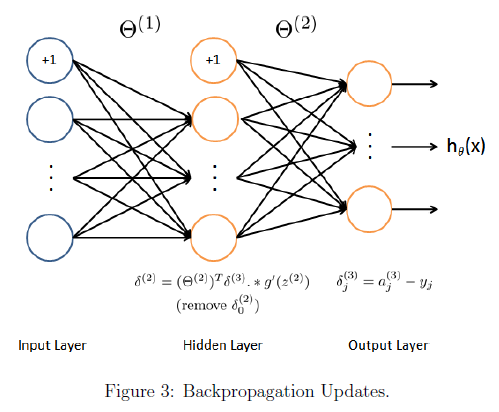

    In detail, here is the backpropagation algorithm (also depicted in Figure 3). You should implement steps 1 to 4 in a loop that processes one example at a time. Concretely, you should implement a `for` loop for `t = 1:m` and place steps 1-4 below inside the `for` loop, with the $t^{th}$ iteration performing the calculation on the $t^{th}$ training example $(x^{(t)}, y^{(t)})$. Step 5 will divide the accumulated gradients by $m$ to obtain the gradients for the neural network cost function.

- Set the input layer's values $(a^{(1)})$ to the $t$-th training example $x^{(t)}$. Perform a feedforward pass (Figure 2), computing the activations $(z^{(2)}, a^{(2)}, z^{(3)}, a^{(3)})$ for layers 2 and 3. Note that you need to add a $+1$ term to ensure that the vectors of activations for layers $a^{(1)}$ and $a^{(2)}$ also include the bias unit. In MATLAB, if `a_1` is a column vector, adding one corresponds to `a_1 = [1; a_1].`

- For each output unit $k$ in layer 3 (the output layer), set $\delta^{(3)}_k = (a_k^{(3)}-y_k)$ where $y_k\in \{0, 1\}$ indicates whether the current training example belongs to class $k$ $(y_k = 1)$, or if it belongs to a different class $(y_k = 0)$.You may find logical arrays helpful for this task (explained in the previous programming exercise).

- For the hidden layer $l = 2$, set $\delta^{(2)} = (\Theta^{(2)})^T \delta^{(3)}.*g'(z^{(2)})$

- Accumulate the gradient from this example using the following formula: $\Delta^{(l)} = \Delta^{(l)} + \delta^{(l+1)} (a^{(l)})^T$. Note that you should skip or remove $\delta_0^{(2)}$. In MATLAB, removing $\delta_0^{(2)}$ corresponds to `delta_2 = delta_2(2:end).`

- Obtain the (unregularized) gradient for the neural network cost function by dividing the accumulated gradients by $\frac{1}{m}:$ $\frac{\partial}{\partial\Theta^{(l)}_{ij}} J(\Theta)= D^{(l)}_{ij}= \frac{1}{m}\Delta^{(l)}_{ij}$

**MATLAB Tip:** You should implement the backpropagation algorithm only after you have successfully completed the feedforward and cost functions. While implementing the backpropagation algorithm, it is often useful to use the size function to print out the sizes of the variables you are working with if you run into dimension mismatch errors (''nonconformant arguments") errors.

    After you have implemented the backpropagation algorithm, the code in the next section will run gradient checking on your implementation. The gradient check will allow you to increase your confidence that your code is computing the gradients correctly.

### 2.4 Gradient checking

In your neural network, you are minimizing the cost function $J(\Theta)$. To perform gradient checking on your parameters, you can imagine 'unrolling' the parameters $\Theta^{(1)},\Theta^{(2)}$ into a long vector $\theta$. By doing so, you can think of the cost function being $J(\theta)$ instead and use the following gradient checking procedure.

    Suppose you have a function $f_i(\theta)$ that purportedly computes $\frac{\partial}{\partial\theta_i}J(\theta)$; you'd like to check if $f_i$ is outputting correct derivative values.


$$\textrm{Let}\;\theta^{i+} =\theta +\left\lbrack \begin{array}{c}
0\\
0\\
\vdots \\
\epsilon \\
\vdots \\
0
\end{array}\right\rbrack \;\textrm{and}\;\theta^{i-} =\theta -\left\lbrack \begin{array}{c}
0\\
0\\
\vdots \\
\epsilon \\
\vdots \\
0
\end{array}\right\rbrack$$


    So, $\theta^{(i+)}$ is the same as $\theta$, except its $i$-th element has been incremented by $\epsilon$. Similarly, $\theta^{(i-)}$is the corresponding vector with the $i$-th element decreased by $\epsilon$. You can now numerically verify $f_i(\theta)$'s correctness by checking, for each $i$, that:


$$f_i(\theta) \approx \frac{J(\theta^{(i+)})-J(\theta^{(i-)})}{2\epsilon}$$


The degree to which these two values should approximate each other will depend on the details of $J$. But assuming $\epsilon= 10^{-4}$, you'll usually find that the left- and right-hand sides of the above will agree to at least 4 signicant digits (and often many more). We have implemented the function to compute the numerical gradient for you in `computeNumericalGradient.m`. While you are not required to modify the file, we highly encourage you to take a look at the code to understand how it works.

   The code below will run the provided function `checkNNGradients.m` which will create a small neural network and dataset that will be used for checking your gradients. If your backpropagation implementation is correct, you should see a relative dierence that is less than 1e-9.

checkNNGradients;

**Practical Tip:** When performing gradient checking, it is much more efficient to use a small neural network with a relatively small number of input units and hidden units, thus having a relatively small number of parameters. Each dimension of $\theta$ requires two evaluations of the cost function and this can be expensive. In the function `checkNNGradients`, our code creates a small random model and dataset which is used with `computeNumericalGradient` for gradient checking. Furthermore, after you are condent that your gradient computations are correct, you should turn off gradient checking before running your learning algorithm.

**Practical Tip: **Gradient checking works for any function where you are computing the cost and the gradient. Concretely, you can use the same `computeNumericalGradient.m` function to check if your gradient implementations for the other exercises are correct too (e.g. logistic regression's cost function). Once your cost function passes the gradient check for the (unregularized) neural network cost function, you should submit the neural network gradient function (backpropagation).

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 2.5 Regularized neural networks

After you have successfully implemeted the backpropagation algorithm, you will add regularization to the gradient. To account for regularization, it turns out that you can add this as an additional term after computing the gradients using backpropagation. Specically, after you have computed $\Delta^{(l)}_{ij}
$ using backpropagation, you should add regularization using


$$\frac{\partial}{\partial\Theta^{(l)}_{ij}} J(\Theta)= D^{(l)}_{ij}= \frac{1}{m}\Delta^{(l)}_{ij} \text{  for  } j = 0,\\
\frac{\partial}{\partial\Theta^{(l)}_{ij}} J(\Theta)= D^{(l)}_{ij}= \frac{1}{m}\Delta^{(l)}_{ij} +\frac{\lambda}{m}\Theta^{(l)}_{ij} \text{  for  } j \geq 1$$


Note that you should *not* be regularizing the first column of $\Theta^{(l)}$ which is used for the bias term. Furthermore, in the parameters $\Theta^{(l)}_{ij}$, $i$ is indexed starting from 1, and $j$ is indexed starting from 0. Thus,


$$\Theta^{\left(l\right)} =\left\lbrack \begin{array}{ccc}
\Theta_{1,0}^{\left(l\right)}  & \Theta_{1,1}^{\left(l\right)}  & \cdots \\
\Theta_{2,0}^{\left(l\right)}  & \Theta_{2,1}^{\left(l\right)}  & \;\\
\vdots  & \; & \ddots 
\end{array}\right\rbrack$$


Somewhat confusingly, indexing in MATLAB starts from 1 (for both $i$ and $j$), thus `Theta1(2, 1)` actually corresponds to $\Theta^{(l)}_{2,0}$ (i.e., the entry in the second row, first column of the matrix $\Theta^{(1)}$ shown above)

    Now, modify your code that computes `grad` in `nnCostFunction` to account for regularization. After you are done, run the code below to run gradient checking on your implementation. If your code is correct, you should expect to see a relative difference that is less than 1e-9.

%  Check gradients by running checkNNGradients
lambda = 3;
checkNNGradients(lambda);
% Also output the costFunction debugging value 
% This value should be about 0.576051
debug_J  = nnCostFunction(nn_params, input_layer_size, hidden_layer_size, num_labels, X, y, lambda);
fprintf('Cost at (fixed) debugging parameters (w/ lambda = 3): %f', debug_J);

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 2.6 Learning parameters using `fmincg`

After you have successfully implemented the neural network cost function and gradient computation, run the code below to use `fmincg` to learn a good set of parameters. After the training completes, the code will report the training accuracy of your classifier by computing the percentage of examples it got correct. If your implementation is correct, you should see a reported training accuracy of about 95.3% (this may vary by about 1% due to the random initialization). It is possible to get higher training accuracies by training the neural network for more iterations. 

options = optimset('MaxIter', 50);
lambda = 1;

% Create "short hand" for the cost function to be minimized
costFunction = @(p) nnCostFunction(p, input_layer_size, hidden_layer_size, num_labels, X, y, lambda);

% Now, costFunction is a function that takes in only one argument (the
% neural network parameters)
[nn_params, ~] = fmincg(costFunction, initial_nn_params, options);
% Obtain Theta1 and Theta2 back from nn_params
Theta1 = reshape(nn_params(1:hidden_layer_size * (input_layer_size + 1)), hidden_layer_size, (input_layer_size + 1));
Theta2 = reshape(nn_params((1 + (hidden_layer_size * (input_layer_size + 1))):end), num_labels, (hidden_layer_size + 1));
 
pred = predict(Theta1, Theta2, X);
fprintf('\nTraining Set Accuracy: %f\n', mean(double(pred == y)) * 100);

## 3. Visualizing the hidden layer

One way to understand what your neural network is learning is to visualize what the representations captured by the hidden units. Informally, given a particular hidden unit, one way to visualize what it computes is to find an input `x` that will cause it to activate (that is, to have an activation value $(a^{(l)}_i)$close to 1). For the neural network you trained, notice that the $i^{th}$ row of $\Theta^{(1)}$ is a 401-dimensional vector that represents the parameter for the $i^{th}$ hidden unit. If we discard the bias term, we get a 400 dimensional vector that represents the weights from each input pixel to the hidden unit. 

    Thus, one way to visualize the 'representation' captured by the hidden unit is to reshape this 400 dimensional vector into a 20 x 20 image and display it.* 

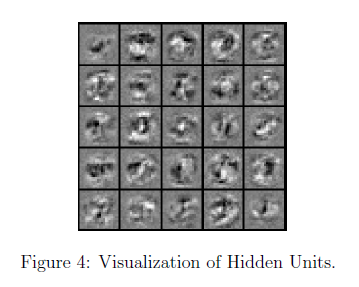

The code below does this by using the `displayData` function and it will show you an image (similar to Figure 4) with 25 units, each corresponding to one hidden unit in the network. In your trained network, you should find that the hidden units corresponds roughly to detectors that look for strokes and other patterns in the input.

% Visualize Weights 
displayData(Theta1(:, 2:end));

**It turns out that this is equivalent to finding the input that gives the highest activation for the hidden unit, given a 'norm' constraint on the input (i.e., *${\left\|x\right\|}_2 \le \;1$*).*

### 3.1 Optional (ungraded) exercise

In this part of the exercise, you will get to try out different learning settings for the neural network to see how the performance of the neural network varies with the regularization parameter and number of training steps (the `MaxIter` option when using `fmincg`). Neural networks are very powerful models that can form highly complex decision boundaries. Without regularization, it is possible for a neural network to 'overfit' a training set so that it obtains close to 100% accuracy on the training set but does not do as well on new examples that it has not seen before. You can set the regularization $\lambda$ to a smaller value and the `MaxIter` parameter to a higher number of iterations to see this for youself. You will also be able to see for yourself the changes in the visualizations of the hidden units when you change the learning parameters $\lambda$ and `MaxIter`.

% Change lambda and MaxIter to see how it affects the result
lambda = 3;
MaxIter = 50;

options = optimset('MaxIter', MaxIter);

% Create "short hand" for the cost function to be minimized
costFunction = @(p) nnCostFunction(p,input_layer_size, hidden_layer_size, num_labels, X, y, lambda);

% Now, costFunction is a function that takes in only one argument (the neural network parameters)
[nn_params, ~] = fmincg(costFunction, initial_nn_params, options);

% Obtain Theta1 and Theta2 back from nn_params
Theta1 = reshape(nn_params(1:hidden_layer_size * (input_layer_size + 1)), hidden_layer_size, (input_layer_size + 1));
Theta2 = reshape(nn_params((1 + (hidden_layer_size * (input_layer_size + 1))):end), num_labels, (hidden_layer_size + 1));
 
pred = predict(Theta1, Theta2, X);
fprintf('\nTraining Set Accuracy: %f\n', mean(double(pred == y)) * 100);

% Visualize Weights 
displayData(Theta1(:, 2:end));

*You do not need to submit any solutions for this optional (ungraded) exercise.*

## Submission and Grading

After completing various parts of the assignment, be sure to use the submit function system to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored.

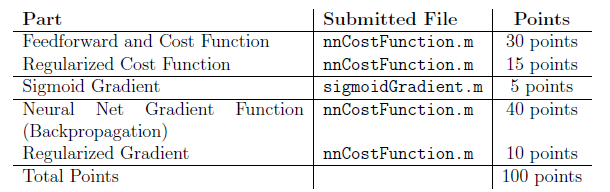

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.